% NetfluxODE_CaoS_opt.m
 % Automatically generated by Netflux on 17-May-2025
 % Adjusted and Expanded by Dmitriy Major
 % Last Update: 06/30/2025

## Initialize

(closes extraneous plots/windows)

 close all
 clc
 clear variables

## Loading Data

This section is primarily concerned with imports and parameter definition and does the following:

- Imports all the parameters for species and reactions in the signaling model, primarily from the Netflux output

- Parsing for the stimulus (Stretch) and gene-type species (for use in plotting, normalization, etc.)

- Imports mRNA fold-changed from experimental data (this also includes parsing for differentially-expressed genes)

- Allows user to set values for the baseline stretch values used for running the model. The first ideally should be set to 0.315 to mimic Shulin's functions.

- Defines time-scale for the baseline run and the activated runs of the model

targets = {'gene_Cxcr7', 'gene_Map3k8', 'gene_Ccna2', 'gene_Adamts9', 'gene_Magi1', 'gene_Nr4a3', 'gene_Fgfr2', 'gene_Per1', 'gene_Csrp3', 'gene_Lmcd1'};
S_in = [0.400, 0.7]; % Stretch Inputs (Baseline, Activated State)
S_in(1) = 0.4; % Baseline Stretch
S_in(2) = 0.7; % Activated Stretch

% === Load parameters ===
[params, y0] = NetfluxODE_CaoS_loadParams();
[rpar, tau, ymax, speciesNames, speciesTypes] = params{:};

% Import RNA Data
[y0_MA, y30m_MA, y30m_MA_trans, y4h_MA, y4h_MA_trans, ...
          p4hlong, p4htrans, p30mlong, p30mtrans, q4hlong, q4htrans, q30mlong, q30mtrans, ...
          DE_Long_ind, DE_Trans_ind, DE_Both_ind, DEG_nodes, unDEG, DE_long4h_ind, DE_4h_more, matchedGeneNames] = ...
          ImportRNA_CaoS(speciesNames, speciesTypes, y0);

% Normalize data by counts
y4h_norm = y4h_MA./y0_MA;
% y30m_norm = y30m_MA./y0_MA;

% Identify Stimulus and Gene indices
stimIdx = find(strcmp(speciesNames, 'Stretch'));
geneIdx = find(contains(speciesTypes, 'Gene'));
targetGeneIdx = find(ismember(speciesNames, targets));
count_sig = 85; % When Genes Start (MATLAB)
% validatedIdx = getValidatedGeneIdx(speciesNames, geneIdx);
validatedIdx = 85:654;


% Defining Time-Scale
tspan = 0:0.1:(24*60); % used for 4hr simulation
tspan1 = [0 30000]; % used for steady state simulation

## Baseline Simulation

The first run of the model sets the value of Stretch to it's first baseline state and runs to model to a longer timescale to extract quasi-steady state baseline values for gene terms later on.

rpar(1,1) = 1; % Set w1 to intial stimulus as necessary
params{1} = rpar;
[t1, y1] = ode15s(@NetfluxODE_CaoS, tspan1, y0, [], params, S_in(1));
ss = y1(end, :)'; % End ouputs from SS model

## Longitudinal Stretch Simulation

The second run of the model sets the value of Stretch to 0.7, chosen to be so based on the limitations of actual tissue stretch experiments.

This section also runs a function to normalize the outputs of the activated model at time t = 30 min, 240 min by the control values from the baseline run of the model, thereby simulating fold-change

rpar(1,1) = 1; % Set w1 to 1.0
params{1} = rpar;

% Standard Simulation at S = 0.7 following SS w/out mRNA Base Counts
y0_new3 = ss;
y0_new3(stimIdx) = S_in(1);
[t2, y2] = ode15s(@NetfluxODE_CaoS, tspan, y0_new3, [], params, S_in(2));

% Normalize longitudinal outputs by steady state
[ylong_4h, ylong_30m, y2norm] = ODENorm(t2, y2, ss, geneIdx);
sigIdxlong = GetSigGeneIdx_CaoS(ylong_4h, geneIdx);

## Plots: Gene Time-Courses

This section plots a few arbitrarily-selected gene species with the stimulus over a log-base time-scale.

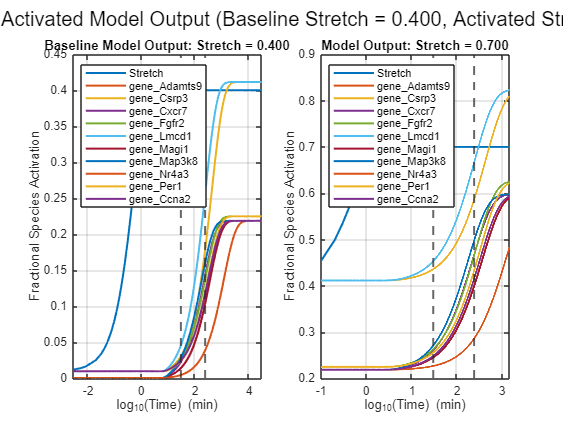

% Plot 1: Steady State
figure;
subplot (1, 2, 1)
plot(log10(t1), y1(:, [stimIdx, targetGeneIdx]), 'LineWidth', 1.5);
hold on
xline(log10(30), '--', 'LineWidth', 1.5)
xline(log10(240), '--', 'LineWidth', 1.5)
xlabel('log_{10}(Time) (min)');
ylabel('Fractional Species Activation');
title(sprintf('Baseline Model Output: Stretch = %.3f', S_in(1)));
legend(speciesNames([stimIdx, targetGeneIdx]), 'Interpreter', 'none', 'Location', 'northwest');
grid on;
xlim([log10(t1(1)) log10(t1(end))]);

% Plot 2: Longitudinal Stretch
subplot(1, 2, 2)
plot(log10(t2), y2(:, [stimIdx, targetGeneIdx]), 'LineWidth', 1.5);
xline(log10(30), '--', 'LineWidth', 1.5)
xline(log10(240), '--', 'LineWidth', 1.5)
xlabel('log_{10}(Time) (min)');
ylabel('Fractional Species Activation');
title(sprintf('Model Output: Stretch = %.3f', S_in(2)));
legend(speciesNames([stimIdx, targetGeneIdx]), 'Interpreter', 'none', 'Location', 'northwest');
grid on;
xlim([log10(t2(1)) log10(t2(end))]);

sgtitle(sprintf('Baseline and Activated Model Output (Baseline Stretch = %.3f, Activated Stretch = %.3f)', S_in(1), S_in(2)))

## Plots: Normalized (FC) Timecourses

This section now plots the normalized timecourse for those same genes

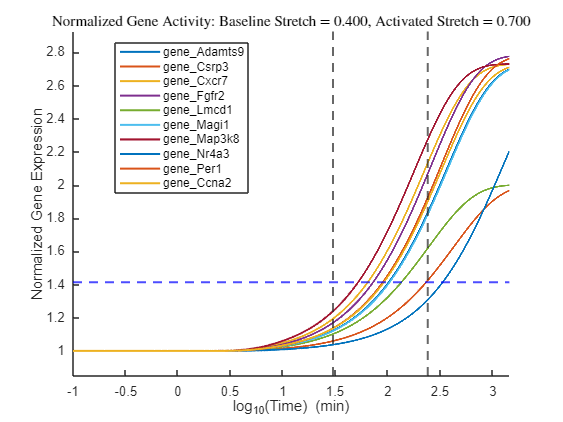

% Plot: Normalized Longitudinal Gene Outputs
maxp = real(max(y2norm(:, targetGeneIdx), [], 'all'));
minp = real(min(y2norm(:, targetGeneIdx), [], 'all'));

figure;
xlim([log10(t2(1)) log10(t2(end))])
ylim([minp-0.15 maxp+0.15])
hold on
plot(log10(t2), y2norm(:, targetGeneIdx), 'LineWidth', 1.5);
xline(log10(30), '--', 'LineWidth', 1.5)
xline(log10(240), '--', 'LineWidth', 1.5)
yline(sqrt(2), 'b--', 'LineWidth', 1.5)
yline(1/sqrt(2), 'b--', 'LineWidth', 1.5)
xlabel('log_{10}(Time) (min)');
ylabel('Normalized Gene Expression');
title(sprintf('Normalized Gene Activity: Baseline Stretch = %.3f, Activated Stretch = %.3f', S_in(1), S_in(2)), 'interpreter', 'latex');
legend(speciesNames(targetGeneIdx), 'Interpreter', 'none', 'Location', 'best');

## Matching to mRNA Raw Data

This section runs a function that parses for how many upstream TFs there are to a particular gene, and organizing the species into three categories:

- Genes with one upstream TF

- Genes with two upstream TFs

- Genes with three or more upstream TFs

[~, matchedGeneIdx] = ismember(matchedGeneNames, speciesNames);

% Parsing for upstream reactant totals
[oneTF, twoTF, multiTF] = ...
 ParseGeneTFInputs_CaoS(geneIdx);

% Parsing for significance (|log2FC| > 0.5)
sig_oneTF_long = intersect(sigIdxlong, oneTF);

% Define colors for each TF group
colors = {'b', 'g', 'm'};  % blue, green, magenta

## Bar Graph: Upstream Rxn Tot.

Plots genes in a bar graph by upstream regulator count (determined in previous section)

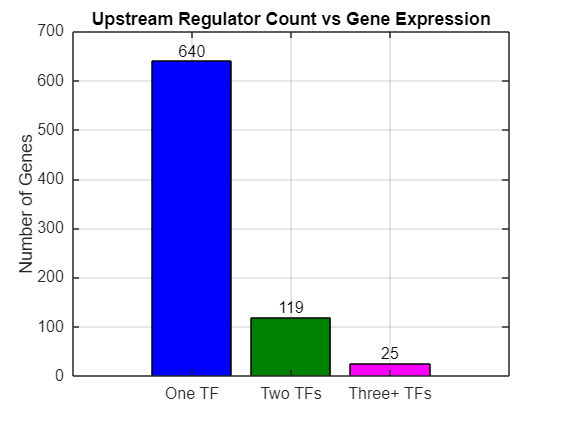

% Counts for each TF category
counts = [numel(oneTF), numel(twoTF), numel(multiTF)];

% Category labels
categories = {'One TF', 'Two TFs', 'Three+ TFs'};

% Create bar graph
figure;
b = bar(counts);

% Set bar colors individually
for k = 1:length(counts)
    b.FaceColor = 'flat';    % enable individual bar coloring
    b.CData(k, :) = reshape(sscanf(colors{k}, '%c'), 1, []); % workaround - use RGB instead (below)
end

% Since setting color from char won’t work directly, convert colors to RGB:
colorRGB = [0 0 1; 0 0.5 0; 1 0 1]; % blue, green, magenta
for k = 1:length(counts)
    b.CData(k, :) = colorRGB(k, :);
end

% Customize axes
set(gca, 'XTickLabel', categories, 'FontSize', 12)
ylabel('Number of Genes')
title('Upstream Regulator Count vs Gene Expression')
grid on

% Add count labels on top of bars
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(counts);
text(xtips, ytips, labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom', 'FontSize',12)

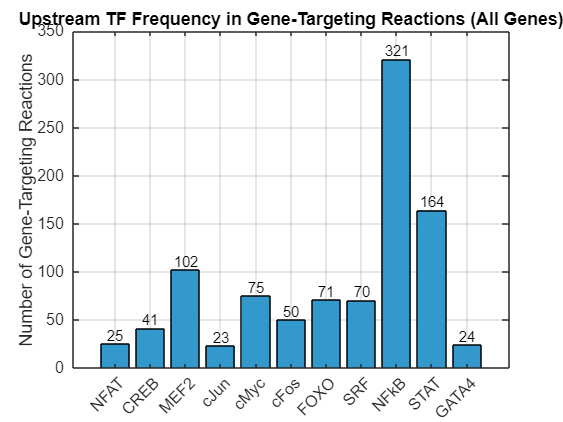

% Categorizing TFs by how many reactions are downstream of each.
filename = 'RxnParsed_CaoSMechanosignaling.xlsx';

% Read species names from column B, starting at row 3
species_raw = readcell(filename, 'Sheet', 'species');
speciesNames2 = species_raw(3:end, 2);  % Column B = index 2

% Ensure names are clean strings
speciesNames2 = string(speciesNames);
speciesNames2 = strtrim(speciesNames);

% Call function
TFCounts = CountSpecificTFs(filename, geneIdx, speciesNames2);

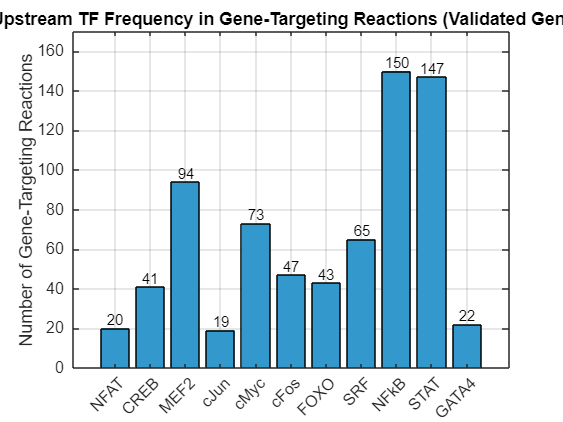

TFCounts = CountSpecificTFs(filename, validatedIdx, speciesNames2);

## Testing Parameter Optimization:

This section is primarily used to test the optimization of parameters based on parameter estimation outputs done through PESTO (a Matlab Toolbox) that runs the model in the same fashion as this code does, just to find ideal parameters based on the minimization of error metrics (which will be specified with each run)

% EC1 = 0.50;
% EC2 = 0.53;
% EC3 = 0.45;





### Optimization Type 1: Optimizing weights of reactions directly affected by stretch ( Stretch => Y ):

Optimizing for RMSE results in a very narrow frequency distribution for the genes involved, and any optimization for metrics of these reactions excluding RMSE (i.e. average or st dev) reveals that w = 0.9 is the most optimized form to calculate FC from the model and maintain the frequency distribution. Even clustering guesses around 0.9 reveals limited increased in optimization. Hence, it may be better to look at reactions deeper in the model (i.e. TF species reactions).

% optIdx = 12:20;
% optimized via a combination of averages, stdev, and RMSE of vaidated
% genes from the model vs. data
% rpar(1, optIdx) = [2.3684, 8.6842, 3.9474, 0.7895, 9.7368, 1.3158, 8.6842, 6.5789, 1.3158];
% optimized via RMSE of vaidated genes from the model vs. data
% rpar(1, optIdx) = [3.4211, 0.7895, 3.9474, 0.7895, 3.9474, 0.2632, 9.7368, 6.0526, 6.5789];
% optimized via mean/stdev diff with LHS (Latin Hypercube Sampled) guess
% input matrix ranging from [0.8 1] and clustered near 0.9
% rpar(1, optIdx) = [ 0.9357, 0.9058, 0.9060, 0.8698, 0.9094, 0.9361, 0.9066, 0.9088, 0.9313];

### Optimization Type 2: Optimizing weights of reactions ustream of transcription factors ( X => TF ):

Optimizing for RMSE results in 

% optIdx = [12:20, 47, 73];
% rpar(1, optIdx) = [    0.9794
%     0.8667
%     0.8700
%     0.9718
%     0.8861
%     0.9175
%     0.9482
%     0.8853
%     0.7835
%     0.8576
%     0.9012];

optIdx = [12:20, 47, 73, 79];
rpar(1, optIdx) = [    0.9841
    0.8885
    0.8840
    0.9802
    0.9169
    0.9541
    0.9625
    0.8965
    0.9050
    0.9413
    0.8398
    0.9374];

% optIdx = [47, 73];
% rpar(1, optIdx) = [0.9917    0.9431];


% optIdx = [47, 71, 72, 73, 79];
% rpar(1, optIdx) = [    0.9234    0.9340    0.9281 0.8723    0.9408];
% rpar(1, optIdx) = [    0.9549
%     0.8046
%     0.9039
%     0.9606
%     0.9214];

% 
% optIdx = [24, 44, 45, 46, 47, 48, 55, 56, 57, 64, 65, 66, 67, 68, 71, 72, 73, 79, 80];
% 
% rpar(1, optIdx) =    [0.9121
%     0.9189
%     0.8600
%     0.9203
%     0.8589
%     0.9072
%     0.8997
%     0.8479
%     0.8996
%     0.9619
%     0.8928
%     0.9346
%     0.9051
%     0.8701
%     0.9042
%     0.8593
%     0.9298
%     0.5500
%     0.8160];

### Model Runs (Optimized)

% Testing with new baseline SS state
params{1} = rpar;
[t6, y6] = ode15s(@NetfluxODE_CaoS, tspan1, y0, [], params, S_in(1));
ss = y6(end, :)'; % End ouputs from SS model
y0_new2 = ss;

% Longitudinal Stretch
y0_new2(stimIdx) = S_in(1);
[t5, y5] = ode15s(@NetfluxODE_CaoS, tspan, y0_new2, [], params, S_in(2));

% Normalize longitudinal outputs by steady state
[ylong_4h_opt, ylong_30m_opt, y8norm] = ODENorm(t5, y5, ss, geneIdx);

## Plots: Gene Time-Courses: Optimized Version

This section plots a few arbitrarily-selected gene species with the stimulus over a log-base time-scale.

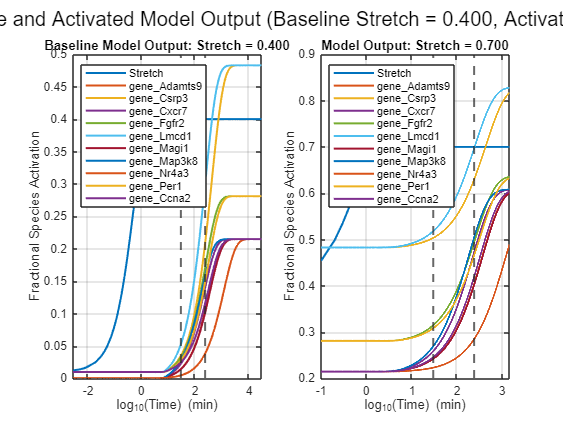

% Plot 1: Steady State
figure;
subplot (1, 2, 1)
plot(log10(t6), y6(:, [stimIdx, targetGeneIdx]), 'LineWidth', 1.5);
hold on
xline(log10(30), '--', 'LineWidth', 1.5)
xline(log10(240), '--', 'LineWidth', 1.5)
xlabel('log_{10}(Time) (min)');
ylabel('Fractional Species Activation');
title(sprintf('Baseline Model Output: Stretch = %.3f', S_in(1)));
legend(speciesNames([stimIdx, targetGeneIdx]), 'Interpreter', 'none', 'Location', 'northwest');
grid on;
xlim([log10(t6(1)) log10(t6(end))]);

% Plot 2: Longitudinal Stretch
subplot(1, 2, 2)
plot(log10(t5), y5(:, [stimIdx, targetGeneIdx]), 'LineWidth', 1.5);
xline(log10(30), '--', 'LineWidth', 1.5)
xline(log10(240), '--', 'LineWidth', 1.5)
xlabel('log_{10}(Time) (min)');
ylabel('Fractional Species Activation');
title(sprintf('Model Output: Stretch = %.3f', S_in(2)));
legend(speciesNames([stimIdx, targetGeneIdx]), 'Interpreter', 'none', 'Location', 'northwest');
grid on;
xlim([log10(t5(1)) log10(t5(end))]);

sgtitle(sprintf('Optimized: Baseline and Activated Model Output (Baseline Stretch = %.3f, Activated Stretch = %.3f)', S_in(1), S_in(2)))

## Plots: Normalized (FC) Timecourses, Optimized

This section now plots the normalized timecourse for those same genes at the new baseline

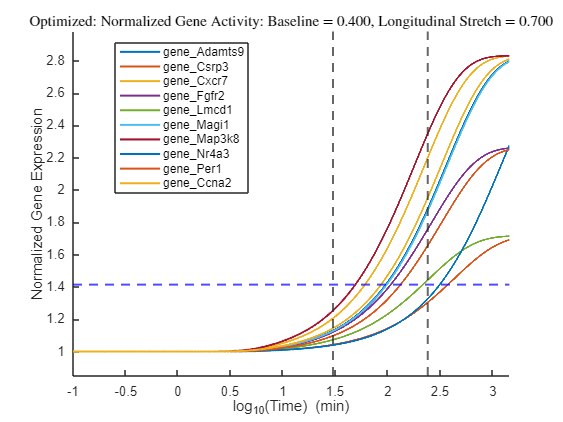

% Plot: Normalized Longitudinal Gene Outputs
maxp = real(max(y8norm(:, targetGeneIdx), [], 'all'));
minp = real(min(y8norm(:, targetGeneIdx), [], 'all'));

figure;
xlim([log10(t5(1)) log10(t5(end))])
ylim([minp-0.15 maxp+0.15])
hold on
plot(log10(t5), y8norm(:, targetGeneIdx), 'LineWidth', 1.5);
xline(log10(30), '--', 'LineWidth', 1.5)
xline(log10(240), '--', 'LineWidth', 1.5)
yline(sqrt(2), 'b--', 'LineWidth', 1.5)
yline(1/sqrt(2), 'b--', 'LineWidth', 1.5)
xlabel('log_{10}(Time) (min)');
ylabel('Normalized Gene Expression');
title(sprintf('Optimized: Normalized Gene Activity: Baseline = %.3f, Longitudinal Stretch = %.3f', S_in(1), S_in(2)), 'interpreter', 'latex');
legend(speciesNames(targetGeneIdx), 'Interpreter', 'none', 'Location', 'best');

## Scatterplot 1: Baseline Changes: Blob Form

The first plot is for the comparing data to model in the following form: $\log_2 \textrm{FC}$

- Subplot one focuses on the original baseline

- Subplot two focuses on the new baseline

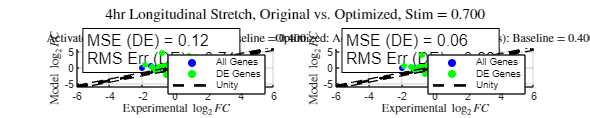

figure('Position', [100, 100, 3000, 600])

z = [-6, 6];

% Subplot 1: Longitudinal Stretched (4h), Original SS = 0.315
subplot(1,2,1)
y_data = log2(ylong_4h);
yhiold = y_data;
x_data = log2(y4h_norm);

% Scatter plot
hold on

% 1) Compute error vectors
err = y_data(validatedIdx) - x_data(validatedIdx);    % signed error
sq_err  = err.^2;


% 2) Compute metrics
MSEa  = mean(err);            % Mean signed error
RMSEa = sqrt( mean(sq_err) );     % Root-mean-square error

txt = sprintf('MSE (DE) = %.2f\nRMS Err (DE) = %.2f', MSEa, RMSEa);
text( z(1)+0.05*diff(z), z(2)-0.05*diff(z), txt, ...
      'FontSize',12, 'BackgroundColor','w', 'EdgeColor','k');

% Plot each TF group separately with different colors
scatter(x_data(geneIdx), y_data(geneIdx), 20, colors{1}, 'filled')
scatter(x_data(validatedIdx), y_data(validatedIdx), 20, colors{2}, 'filled')

% Plot identity line
plot(z(1):0.1:z(2), z(1):0.1:z(2), 'k--', 'LineWidth', 2) 

x_vals = z(1):0.1:z(2);
plot(x_vals, x_vals - 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');
plot(x_vals, x_vals + 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');

% Linear regression (least squares fit)
mlin1 = dot(y_data(validatedIdx), x_data(validatedIdx)) / dot(y_data(validatedIdx), y_data(validatedIdx));

% Axis labels, title
xlabel('Experimental $\log_{2} FC$', 'Interpreter', 'latex')
ylabel('Model $\log_{2} FC$', 'Interpreter', 'latex')
title(sprintf('Activated $log_{2} FC$ (Valdated Genes): Baseline = %.3f', S_in(1)), 'Interpreter', 'latex')

xlim([z(1) z(2)])
ylim([z(1) z(2)])
grid on

% Legend with regression and Pearson stats
legend({...
    'All Genes', ...
    'DE Genes', ...
    'Unity'}, ...
    'Location', 'southeast')

hold off

% Subplot 2: Longitudinal Stretched (4h), New SS
subplot(1,2,2)

subplot(1,2,2)
y_data = log2(ylong_4h_opt);
yhi = y_data;
x_data = log2(y4h_norm);
xhi = x_data;

% 1) Compute error vectors
err = y_data(validatedIdx) - x_data(validatedIdx);           % signed error
sq_err  = err.^2;

% 2) Compute metrics
MSEb  = mean(err);            % Mean signed error
RMSEb = sqrt( mean(sq_err) );     % Root-mean-square error

txt = sprintf('MSE (DE) = %.2f\nRMS Err (DE) = %.2f', MSEb, RMSEb);
text( z(1)+0.05*diff(z), z(2)-0.05*diff(z), txt, ...
      'FontSize',12, 'BackgroundColor','w', 'EdgeColor','k');

% Scatter plot
hold on

% Plot each TF group separately with different colors
scatter(x_data(geneIdx), y_data(geneIdx), 20, colors{1}, 'filled')
scatter(x_data(validatedIdx), y_data(validatedIdx), 20, colors{2}, 'filled')


% Plot identity line
plot(z(1):0.1:z(2), z(1):0.1:z(2), 'k--', 'LineWidth', 2) 

x_vals = z(1):0.1:z(2);
plot(x_vals, x_vals - 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');
plot(x_vals, x_vals + 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');

% Linear regression (least squares fit)
mlin2 = dot(y_data(validatedIdx), x_data(validatedIdx)) / dot(y_data(validatedIdx), y_data(validatedIdx));


% Axis labels, title
xlabel('Experimental $\log_{2} FC$', 'Interpreter', 'latex')
ylabel('Model $\log_{2} FC$', 'Interpreter', 'latex')
title(sprintf('Optimized: Activated $log_{2} FC$ (Validated Genes): Baseline = %.3f', S_in(1)), 'Interpreter', 'latex')

xlim([z(1) z(2)])
ylim([z(1) z(2)])
grid on

% Legend with regression and Pearson stats
legend({...
    'All Genes', ...
    'DE Genes', ...
    'Unity'}, ...
    'Location', 'southeast')

hold off

sgtitle(sprintf('4hr Longitudinal Stretch, Original vs. Optimized, Stim = %.3f', S_in(2)), 'Interpreter', 'latex')

## Averages (for comparison)

% Average Comparisons: Longitudinal Stretch
% averages = [mean(y4h_norm(validatedIdx)), mean(ylong_4h(validatedIdx)), mean(ylong_4h_opt(validatedIdx))]; %FC
% averagesCount = [mean(y4h_norm(validatedIdx).*y0_MA(validatedIdx)), mean(ylong_4h(validatedIdx).*y0_MA(validatedIdx)), mean(ylong_4h_opt(validatedIdx).*y0_MA(validatedIdx))]; %FC*Counts
% averageslog = [mean(log2(y4h_norm(validatedIdx))), mean(log2(ylong_4h(validatedIdx))), mean(log2(ylong_4h_opt(validatedIdx)))]; %log2FC
% averageslogCount = [mean(log2(y4h_norm(validatedIdx).*y0_MA(validatedIdx))), mean(log2(ylong_4h(validatedIdx).*y0_MA(validatedIdx))), mean(log2(ylong_4h_opt(validatedIdx).*y0_MA(validatedIdx)))]; %log2FC*Counts

averages = [mean(y4h_norm(oneTF)), mean(ylong_4h(oneTF)), mean(ylong_4h_opt(oneTF))]; %FC
averagesCount = [mean(y4h_norm(oneTF).*y0_MA(oneTF)), mean(ylong_4h(oneTF).*y0_MA(oneTF)), mean(ylong_4h_opt(oneTF).*y0_MA(oneTF))]; %FC*Counts
averageslog = [mean(log2(y4h_norm(oneTF))), mean(log2(ylong_4h(oneTF))), mean(log2(ylong_4h_opt(oneTF)))]; %log2FC
averageslogCount = [mean(log2(y4h_norm(oneTF).*y0_MA(oneTF))), mean(log2(ylong_4h(oneTF).*y0_MA(oneTF))), mean(log2(ylong_4h_opt(oneTF).*y0_MA(oneTF)))]; %log2FC*Counts

## Error Metrics: RNA-seq Data

disp(['Average (FC): ', num2str(averages(1))]);

Average (FC): 1.119


disp(['Average (FC*Counts): ', num2str(averagesCount(1))]);

Average (FC*Counts): 7389.6766


disp(['Average (log2FC): ', num2str(averageslog(1))]);

Average (log2FC): 0.08275


disp(['Average (log2(FC*Counts)): ', num2str(averageslogCount(1))]);

Average (log2(FC*Counts)): 10.5396


## Error Metrics: Original Model (S = 0.400)

Based on comparing averages between the Fold-Change (and other forms) between the model and the experimental data, 0.435 is a good baseline with 3 significant figures that lines up with a near-zero MSE value and a low RMSE point. As a result, this baseline for the validated gene-set will serve as a good starting point for optimization.

% Original Model
err = ylong_4h - y4h_norm;
sq_err = err.^2;
MSE1  = mean(err);            % Mean signed error
RMSE1 = sqrt( mean(sq_err) );     % Root-mean-square error

fprintf('\nOriginal Longitudinal Stretch (4h), Baseline = %.3f\n', S_in(1))


Original Longitudinal Stretch (4h), Baseline = 0.400


fprintf('Mean Signed Error (FC) = %.4f\n', MSE1);

Mean Signed Error (FC) = 0.0913


fprintf('RMS Error (FC) = %.4f\n', RMSE1);

RMS Error (FC) = 1.2428


fprintf('RMS Error (log2FC) = %.4f\n', RMSEa);

RMS Error (log2FC) = 0.7090


fprintf('Mean Signed Error (log2FC) = %.4f\n', MSEa);

Mean Signed Error (log2FC) = 0.1244


disp(['Average (FC): ', num2str(averages(2))]);

Average (FC): 1.139


disp(['Average (FC*Counts): ', num2str(averagesCount(2))]);

Average (FC*Counts): 7953.3087


disp(['Average (log2FC): ', num2str(averageslog(2))]);

Average (log2FC): 0.1424


disp(['Average (log2(FC*Counts)): ', num2str(averageslogCount(2))]);

Average (log2(FC*Counts)): 10.5993


## Error Metrics: Optimized Model (S = 0.400)

% Optimized Model
err = ylong_4h_opt - y4h_norm;
sq_err = err.^2;
MSE2  = mean(err);            % Mean signed error
RMSE2 = sqrt( mean(sq_err) );     % Root-mean-square error

fprintf('\nOptimized: Longitudinal Stretch (4h), Baseline = %.3f\n', S_in(1))


Optimized: Longitudinal Stretch (4h), Baseline = 0.400


fprintf('Mean Signed Error (FC) = %.4f\n', MSE2);

Mean Signed Error (FC) = 0.0238


fprintf('RMS Error (FC) = %.4f\n', RMSE2);

RMS Error (FC) = 0.9134


fprintf('RMS Error (log2FC) = %.4f\n', RMSEb);

RMS Error (log2FC) = 0.6649


fprintf('Mean Signed Error (log2FC) = %.6f\n', MSEb);

Mean Signed Error (log2FC) = 0.064471


disp(['Average (FC): ', num2str(averages(3))]);

Average (FC): 1.1039


disp(['Average (FC*Counts): ', num2str(averagesCount(3))]);

Average (FC*Counts): 7633.8066


disp(['Average (log2FC): ', num2str(averageslog(3))]);

Average (log2FC): 0.10542


disp(['Average (log2(FC*Counts)): ', num2str(averageslogCount(3))]);

Average (log2(FC*Counts)): 10.5623


## Frequency Distribution Analysis: Original vs. Optimized

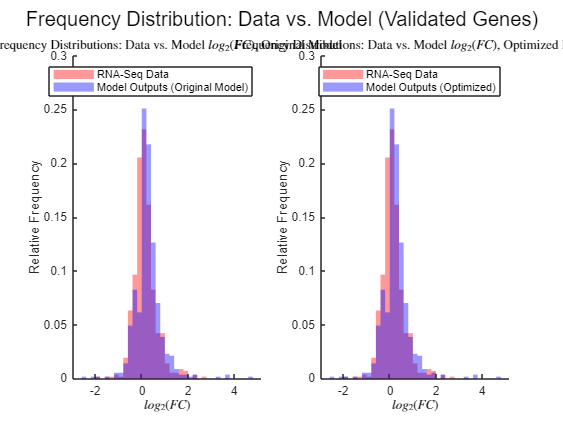


Descriptive statistics:
 Data:     mean=0.138, median=0.0658, std=0.497, Q1=-0.142, Q3=0.333
 Model 1:  mean=0.262, median=0.217, std=0.597, Q1=0.0475, Q3=0.475
 Model 2:  mean=0.202, median=0.188, std=0.538, Q1=0.0412, Q3=0.398


stats = struct with fields:
      data: [1×1 struct]
    model1: [1×1 struct]
    model2: [1×1 struct]


significantIdx = validatedIdx(abs(xhi(validatedIdx)) > 0.5);
significantIdx2 = intersect(oneTF, validatedIdx);
significantIdx3 = intersect(twoTF, validatedIdx);
significantIdx4 = intersect(multiTF, validatedIdx);
% stats = compareFreqDist(xhi(significantIdx), yhiold(significantIdx), yhi(significantIdx))
stats = compareFreqDist(xhi(validatedIdx), yhiold(validatedIdx), yhi(validatedIdx))

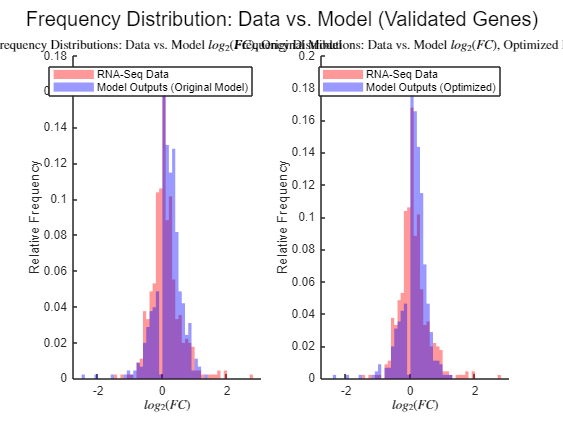


Descriptive statistics:
 Data:     mean=0.0972, median=0.0468, std=0.451, Q1=-0.151, Q3=0.289
 Model 1:  mean=0.173, median=0.194, std=0.423, Q1=0.0502, Q3=0.408
 Model 2:  mean=0.126, median=0.163, std=0.389, Q1=0.0435, Q3=0.334


stats1 = struct with fields:
      data: [1×1 struct]
    model1: [1×1 struct]
    model2: [1×1 struct]


% stats1 = compareFreqDist(xhi(oneTF), yhiold(oneTF), yhi(oneTF))
stats1 = compareFreqDist(xhi(significantIdx2), yhiold(significantIdx2), yhi(significantIdx2))

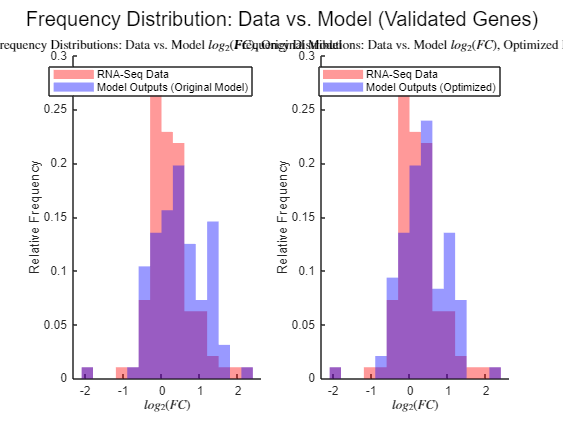


Descriptive statistics:
 Data:     mean=0.236, median=0.205, std=0.581, Q1=-0.134, Q3=0.49
 Model 1:  mean=0.454, median=0.407, std=0.672, Q1=-0.0713, Q3=0.932
 Model 2:  mean=0.361, median=0.354, std=0.605, Q1=-0.0761, Q3=0.718


stats2 = struct with fields:
      data: [1×1 struct]
    model1: [1×1 struct]
    model2: [1×1 struct]


% stats2 = compareFreqDist(xhi(twoTF), yhiold(twoTF), yhi(twoTF))
stats2 = compareFreqDist(xhi(significantIdx3), yhiold(significantIdx3), yhi(significantIdx3))

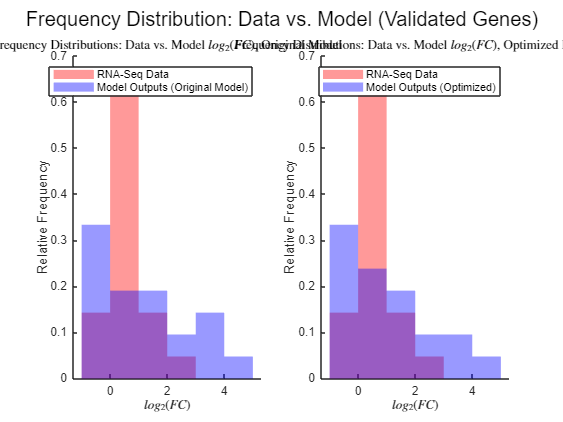


Descriptive statistics:
 Data:     mean=0.56, median=0.416, std=0.74, Q1=0.113, Q3=0.814
 Model 1:  mean=1.31, median=0.817, std=1.56, Q1=-0.118, Q3=2.1
 Model 2:  mean=1.12, median=0.574, std=1.4, Q1=-0.197, Q3=1.95


stats3 = struct with fields:
      data: [1×1 struct]
    model1: [1×1 struct]
    model2: [1×1 struct]


% stats3 = compareFreqDist(xhi(multiTF), yhiold(multiTF), yhi(multiTF))
stats3 = compareFreqDist(xhi(significantIdx4), yhiold(significantIdx4), yhi(significantIdx4))

## Scatterplot 2: Baseline Changes: mRNA Counts Form

The first plot is for the comparing data to model in the following form: $\log_2 \left(\textrm{FC}*\textrm{mRNA}\;\textrm{Counts}\right)$

- Subplot one focuses on the original baseline

- Subplot two focuses on the new baseline

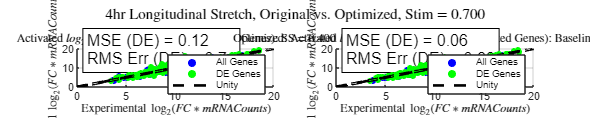

figure('Position', [100, 100, 3000, 600])

z = [0, 20];

% Subplot 1: Longitudinal Stretched (4h), Original SS = 0.315
subplot(1,2,1)
y_data = log2(ylong_4h.*y0_MA);
x_data = log2(y4h_norm.*y0_MA);


% Scatter plot
hold on

% 1) Compute error vectors
err = y_data(validatedIdx) - x_data(validatedIdx);    % signed error
sq_err  = err.^2;


% 2) Compute metrics
MSEa  = mean(err);            % Mean signed error
RMSEa = sqrt( mean(sq_err) );     % Root-mean-square error

txt = sprintf('MSE (DE) = %.2f\nRMS Err (DE) = %.2f', MSEa, RMSEa);
text( z(1)+0.05*diff(z), z(2)-0.05*diff(z), txt, ...
      'FontSize',12, 'BackgroundColor','w', 'EdgeColor','k');

% Plot each TF group separately with different colors
scatter(x_data(geneIdx), y_data(geneIdx), 20, colors{1}, 'filled')
scatter(x_data(validatedIdx), y_data(validatedIdx), 20, colors{2}, 'filled')

% Plot identity line
plot(z(1):0.1:z(2), z(1):0.1:z(2), 'k--', 'LineWidth', 2) 

x_vals = z(1):0.1:z(2);
plot(x_vals, x_vals - 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');
plot(x_vals, x_vals + 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');


% Axis labels, title
xlabel('Experimental $\log_{2} (FC * mRNACounts)$', 'Interpreter', 'latex')
ylabel('Model $\log_{2} (FC * mRNACounts)$', 'Interpreter', 'latex')
title(sprintf('Activated $log_{2} (FC * mRNACounts)$ (Validated Genes): SS = %.3f', S_in(1)), 'Interpreter', 'latex')

xlim([z(1) z(2)])
ylim([z(1) z(2)])
grid on

% Legend with regression and Pearson stats
legend({...
    'All Genes', ...
    'DE Genes', ...
    'Unity'}, ...
    'Location', 'southeast')

hold off

% Subplot 2: Longitudinal Stretched (4h), New SS
subplot(1,2,2)

subplot(1,2,2)
y_data = log2(ylong_4h_opt.*y0_MA);
x_data = log2(y4h_norm.*y0_MA);


% 1) Compute error vectors
err = y_data(validatedIdx) - x_data(validatedIdx);           % signed error
sq_err  = err.^2;

% 2) Compute metrics
MSEb  = mean(err);            % Mean signed error
RMSEb = sqrt( mean(sq_err) );     % Root-mean-square error

txt = sprintf('MSE (DE) = %.2f\nRMS Err (DE) = %.2f', MSEb, RMSEb);
text( z(1)+0.05*diff(z), z(2)-0.05*diff(z), txt, ...
      'FontSize',12, 'BackgroundColor','w', 'EdgeColor','k');

% Scatter plot
hold on

% Plot each TF group separately with different colors
scatter(x_data(geneIdx), y_data(geneIdx), 20, colors{1}, 'filled')
scatter(x_data(validatedIdx), y_data(validatedIdx), 20, colors{2}, 'filled')


% Plot identity line
plot(z(1):0.1:z(2), z(1):0.1:z(2), 'k--', 'LineWidth', 2) 

x_vals = z(1):0.1:z(2);
plot(x_vals, x_vals - 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');
plot(x_vals, x_vals + 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');


% Axis labels, title
xlabel('Experimental $\log_{2} (FC * mRNACounts)$', 'Interpreter', 'latex')
ylabel('Model $\log_{2} (FC * mRNACounts)$', 'Interpreter', 'latex')
title(sprintf('Optimized: Activated $log_{2} (FC * mRNACounts)$ (Validated Genes): Baseline = %.3f', S_in(1)), 'Interpreter', 'latex')

xlim([z(1) z(2)])
ylim([z(1) z(2)])
grid on

% Legend with regression and Pearson stats
legend({...
    'All Genes', ...
    'DE Genes', ...
    'Unity'}, ...
    'Location', 'southeast')

hold off

sgtitle(sprintf('4hr Longitudinal Stretch, Original vs. Optimized, Stim = %.3f', S_in(2)), 'Interpreter', 'latex')

## Scatterplot 3: Other Forms (Differentially-Expressed Genes, TF Count)

The third plot is for the comparing data to model in the following form: $\log_2 \textrm{FC}$

- Subplot one focuses on the new baseline, but plots differentially-expressed genes

- Subplot two focuses on the new baseline, but plots by upstream TF count

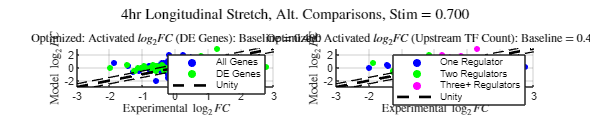

figure('Position', [100, 100, 3000, 600])
z = [-3, 3];

% Subplot 1: DE Genes

subplot(1,2,1)
y_data = log2(ylong_4h_opt);
x_data = log2(y4h_norm);

% Scatter plot
hold on

% 1) Compute error vectors
err = y_data - x_data;           % signed error
abs_err = abs(err);              % absolute error
sq_err  = err.^2;                % squared error

% 2) Compute metrics
% MAE  = mean(abs_err);            % Mean absolute error
% RMSE = sqrt( mean(sq_err) );     % Root-mean-square error


% Plot each TF group separately with different colors
scatter(x_data(geneIdx), y_data(geneIdx), 20, colors{1}, 'filled')
scatter(x_data(DE_4h_more), y_data(DE_4h_more), 20, colors{2}, 'filled')

% Plot identity line
plot(z(1):0.1:z(2), z(1):0.1:z(2), 'k--', 'LineWidth', 2) 

x_vals = z(1):0.1:z(2);
plot(x_vals, x_vals - 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');
plot(x_vals, x_vals + 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');




% Axis labels, title
xlabel('Experimental $\log_{2} FC$', 'Interpreter', 'latex')
ylabel('Model $\log_{2} FC$', 'Interpreter', 'latex')
title(sprintf('Optimized: Activated $log_{2} FC$ (DE Genes): Baseline = %.3f', S_in(1)), 'Interpreter', 'latex')
xlim([z(1) z(2)])
ylim([z(1) z(2)])
grid on

% Legend with regression and Pearson stats
legend({...
    'All Genes', ...
    'DE Genes', ...
    'Unity'}, ...
    'Location', 'southeast')

hold off

% Subplot 2: Number of TFs Plot
subplot(1,2,2)

y_data = log2(ylong_4h_opt);
x_data = log2(y4h_norm);

% 1) Compute error vectors
err = y_data - x_data;           % signed error
abs_err = abs(err);              % absolute error
sq_err  = err.^2;                % squared error

% 2) Compute metrics
% MAE  = mean(abs_err);            % Mean absolute error
% RMSE = sqrt( mean(sq_err) );     % Root-mean-square error


% Scatter plot
hold on

% Plot each TF group separately with different colors
scatter(x_data(oneTF), y_data(oneTF), 20, colors{1}, 'filled')
scatter(x_data(twoTF), y_data(twoTF), 20, colors{2}, 'filled')
scatter(x_data(multiTF), y_data(multiTF), 20, colors{3}, 'filled')


% Plot identity line
plot(z(1):0.1:z(2), z(1):0.1:z(2), 'k--', 'LineWidth', 2) 

x_vals = z(1):0.1:z(2);
plot(x_vals, x_vals - 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');
plot(x_vals, x_vals + 0.5, 'k--', ...
     'LineWidth', 1.0, 'HandleVisibility','off');


% Pearson correlation coefficient
R = corrcoef(y_data, x_data);
r_val = R(1,2);
r_squared = r_val^2;


% Axis labels, title
xlabel('Experimental $\log_{2} FC$', 'Interpreter', 'latex')
ylabel('Model $\log_{2} FC$', 'Interpreter', 'latex')
title(sprintf('Optimized: Activated $log_{2} FC$ (Upstream TF Count): Baseline = %.3f', S_in(1)), 'Interpreter', 'latex')
xlim([z(1) z(2)])
ylim([z(1) z(2)])
grid on

% Legend with regression and Pearson stats
legend({...
    'One Regulator', ...
    'Two Regulators', ...
    'Three+ Regulators', ...
    'Unity'}, ...
    'Location', 'southeast')

hold off

sgtitle(sprintf('4hr Longitudinal Stretch, Alt. Comparisons, Stim = %.3f', S_in(2)), 'Interpreter', 'latex')

## Functions

% Normalization of genes by SS value (FC)
function [yout_4h, yout_30m, ynorm] = ODENorm(t_in, y_in, ss, geneIdx)
ynorm = y_in;
ynorm(:, geneIdx) = y_in(:, geneIdx) ./ ss(geneIdx)';
yout_4h = ynorm(find(t_in >= 240, 1), :)';
yout_30m = ynorm(find(t_in >= 30, 1), :)';
end

% Check outputs for significance (|log2FC|>0.5)
function sigIdx = GetSigGeneIdx_CaoS(ynormval, geneIdx)
    fc_thresh = sqrt(2);
    geneVals = ynormval(geneIdx);
    sigMask = (geneVals > fc_thresh) | (geneVals < 1/fc_thresh);
    sigIdx = geneIdx(sigMask);
end

## **Netflux Parameter Import Function**

Imported reaction and species parameters

function [params,y0] = NetfluxODE_CaoS_loadParams() 
% NetfluxODE_CaoS_loadParams.m 
% Automatically generated by Netflux on 17-May-2025
 
% species parameters 
speciesNames = {'aActinin','Actin','Akt','AngII','AT1R','Ca','CaM','CaMK','CaN','cFos','cGMP','cJun','cMyc','CREB','DAG','Dysgl','Dysph','EGFR','eIF4E','elF2B','ERK12','ERK5','ET1','ET1R','FAK','FHL1','FHL2','FoxO','Ga1213','Gaq11','GATA4','Gbg','gp130','GSK3b','HDAC','IkB','IKK','Integrin','IP3','JAK','JNK','Lmcd1','LTCC','MEF2','MEK12','MEK36','MEK47','MEK5','MEKK1','MEKK23','MEKK4','MLP','MRTF','mTor','MuRF','Na','NCX','NFAT','NFkB','NHE','NOS','p38','p70s6k','PDK1','PI3K','PKC','PKG1','PLC','Rac1','Raf1','Ras','RhoA','RhoGEF','ROCK','sGC','Src','SRF','STAT','Stretch','Talin','Titin','TRP','Vinculin','CellArea','gene_3425401B19Rik','gene_6430548M08Rik','gene_9930013L23Rik','gene_Abca1','gene_Abcc3','gene_Abcd3','gene_Abcg2','gene_Abl2','gene_Acta1','gene_Adamts6','gene_Adamts9','gene_Adamtsl1','gene_Add1','gene_Adm','gene_Aff3','gene_Agt','gene_Agtpbp1','gene_Akap12','gene_Akap2','gene_Akt3','gene_Aldh1b1','gene_Alg3','gene_Amotl2','gene_Ampd3','gene_Angptl4','gene_Ank3','gene_Ankrd1','gene_Ankrd6','gene_Apln','gene_Arfgef2','gene_Arhgdib','gene_Arnt2','gene_Arntl','gene_Arntl2','gene_Atf3','gene_Atic','gene_Atp13a3','gene_Atp1a2','gene_Atp2a2','gene_Atp2b1','gene_Atp2b4','gene_Atp6v0b','gene_Axl','gene_B4galt1','gene_Bach1','gene_Bach2','gene_Bag3','gene_Baiap2l1','gene_Bcl2','gene_Bcl2l13','gene_Bcl3','gene_Bcl6','gene_Bdkrb2','gene_Bdnf','gene_Bet1','gene_Bex1','gene_Blcap','gene_Bmp2','gene_Bmp7','gene_Btg2','gene_Bves','gene_C1s','gene_C3','gene_Cant1','gene_Cask','gene_Casp4','gene_Casq1','gene_Casq2','gene_Cast','gene_Ccl2','gene_Ccl20','gene_Ccl3','gene_Ccnd1','gene_Ccnf','gene_Ccng2','gene_Cd83','gene_Cdc42ep3','gene_Cdh11','gene_Cdk2','gene_Cdk4','gene_Cdkn1a','gene_Cdkn1c','gene_Cdkn2c','gene_Cdv3','gene_Ceacam1','gene_Cfl2','gene_Chd1','gene_Chn1','gene_Chst11','gene_Chst2','gene_Chst8','gene_Cirh1a','gene_Cited2','gene_Ckb','gene_Ckm','gene_Cnn1','gene_Col14a1','gene_Col1a1','gene_Col1a2','gene_Col4a6','gene_Col5a1','gene_Col6a1','gene_Col8a1','gene_Col8a2','gene_Cpeb4','gene_Crem','gene_Crim1','gene_Cryab','gene_Csda','gene_Csdc2','gene_Csrp2','gene_Csrp3','gene_Ctgf','gene_Ctsb','gene_Ctsl','gene_Cxcl12','gene_Cxcl14','gene_Cxcl5','gene_Cxcr4','gene_Cxcr7','gene_Cyfip2','gene_Dapk2','gene_Ddx10','gene_Ddx18','gene_Des','gene_Dhodh','gene_Dicer1','gene_Dio2','gene_Dmd','gene_Dnajb4','gene_Dnajb5','gene_Dnajc10','gene_Dok7','gene_Dpp4','gene_Dtna','gene_Dusp1','gene_Dusp22','gene_Dusp27','gene_Dusp4','gene_Dusp5','gene_Dusp6','gene_Efna1','gene_Efnb2','gene_Egfr','gene_Egln3','gene_Egr1','gene_Egr2','gene_Eif4a1','gene_Ell2','gene_Emd','gene_Eml1','gene_Emp1','gene_Enah','gene_Epas1','gene_Erbb3','gene_Esd','gene_Esm1','gene_Ets2','gene_Evi5','gene_Ext2','gene_Fancl','gene_Fblim1','gene_Fbln2','gene_Fbn2','gene_Fbxl3','gene_Fem1c','gene_Fgf11','gene_Fgfr2','gene_Fgfr3','gene_Fhl1','gene_Fhod1','gene_Fkbp3','gene_Flnb','gene_Flrt1','gene_Flrt3','gene_Fn1','gene_Fnbp1','gene_Fos','gene_Fosb','gene_Fosl1','gene_Fosl2','gene_Foxc1','gene_Foxp4','gene_Frmpd1','gene_Fst','gene_Fstl1','gene_Fyn','gene_Fzd5','gene_Fzd8','gene_G0s2','gene_Gadd45b','gene_Gadd45g','gene_Gata6','gene_Gch1','gene_Gclc','gene_Gem','gene_Gfpt2','gene_Gfra1','gene_Gramd3','gene_Grasp','gene_Grb10','gene_Grip2','gene_Grpel1','gene_Gsk3b','gene_Gtf2i','gene_Gys1','gene_Hbegf','gene_Heatr3','gene_Hfe2','gene_Hhex','gene_Hk1','gene_Hk2','gene_Hmga1','gene_Hmox1','gene_Homer1','gene_Hook1','gene_Hpgd','gene_Hps1','gene_Hrc','gene_Hs3st1','gene_Hs6st2','gene_Hspb2','gene_Hspb7','gene_Hspb8','gene_Hspd1','gene_Htra1','gene_Icam1','gene_Id3','gene_Ier2','gene_Ifi44','gene_Ikzf2','gene_Ikzf5','gene_Il15','gene_Il1r1','gene_Inadl','gene_Inhba','gene_Ipo4','gene_Iqgap2','gene_Irak2','gene_Irf1','gene_Itga9','gene_Itgb1','gene_Itgb1bp2','gene_Itgb6','gene_Jak2','gene_Jph2','gene_Jun','gene_Junb','gene_Kcnj15','gene_Kcnn4','gene_Kctd11','gene_Kctd8','gene_Klf3','gene_Klf4','gene_Klf6','gene_Klf7','gene_Krt18','gene_Lama2','gene_Lamb3','gene_Lamc2','gene_Lancl1','gene_Lap3','gene_Large','gene_Layn','gene_Lbh','gene_Lbp','gene_Ldb3','gene_Lef1','gene_Lfng','gene_Lhfpl2','gene_Lin7c','gene_Litaf','gene_Lix1','gene_Lman1','gene_Lmcd1','gene_Lmod3','gene_Lnpep','gene_Loxl2','gene_Lpin1','gene_Lrig1','gene_Lrp1','gene_Lrrc2','gene_Lsr','gene_Ltbp2','gene_Ltbp3','gene_Lyn','gene_Maff','gene_Mafk','gene_Magi1','gene_Map2k3','gene_Map3k8','gene_Mapk6','gene_Mapkap1','gene_Mapre2','gene_Mapt','gene_Mb','gene_Mbnl2','gene_Mboat2','gene_Mcoln2','gene_Met','gene_Mettl1','gene_Mid1','gene_Mknk1','gene_Mlh1','gene_Mllt10','gene_Mmp12','gene_Mreg','gene_Mrpl14','gene_Mrpl45','gene_Mrpl47','gene_Mrps14','gene_Mrvi1','gene_Msn','gene_Mtcp1','gene_Myc','gene_Myh3','gene_Myh7','gene_Myh9','gene_Myl3','gene_Myl4','gene_Myl9','gene_Mylpf','gene_Myo10','gene_Myo18b','gene_Myo1b','gene_Myog','gene_Myom1','gene_Myom2','gene_Myom3','gene_Mypn','gene_Nab1','gene_Napa','gene_Nav3','gene_Ncald','gene_Ncl','gene_Nde1','gene_Nebl','gene_Nedd4l','gene_Nexn','gene_Nfil3','gene_Nfkb2','gene_Nfkbia','gene_Nfkbiz','gene_Nnmt','gene_Nol6','gene_Npm1','gene_Npnt','gene_Nppb','gene_Nptx1','gene_Npy','gene_Nr1d1','gene_Nr4a1','gene_Nr4a2','gene_Nr4a3','gene_Nrap','gene_Nrg1','gene_Nrip1','gene_Nuak1','gene_Nub1','gene_Nudt6','gene_Obscn','gene_Ociad2','gene_Optn','gene_Osbp2','gene_Osr1','gene_Ostf1','gene_Pa2g4','gene_Pabpc1','gene_Paics','gene_Panx1','gene_Pard6b','gene_Paxip1','gene_Pcdh18','gene_Pcdh7','gene_Pcolce2','gene_Pdcd2','gene_Pdgfb','gene_Pdgfrl','gene_Pdlim4','gene_Pdzd8','gene_Peg10','gene_Peli2','gene_Per1','gene_Pfkfb3','gene_Pfkm','gene_Pfn1','gene_Pgrmc2','gene_Phb','gene_Pik3cb','gene_Pik3r1','gene_Pip5k1b','gene_Pitpnc1','gene_Pkia','gene_Pla2g4a','gene_Plagl1','gene_Plau','gene_Plaur','gene_Plcb4','gene_Plekha1','gene_Plekha7','gene_Plod2','gene_Plscr1','gene_Pmaip1','gene_Pnrc2','gene_Ppap2b','gene_Ppapdc3','gene_Ppard','gene_Ppif','gene_Ppp1r9b','gene_Prpf4b','gene_Prrx1','gene_Psme2','gene_Ptgs2','gene_Ptprf','gene_Ptprn','gene_Pxmp3','gene_Pygm','gene_Qpct','gene_Rab11fip1','gene_Rab27a','gene_Rae1','gene_Ranbp9','gene_Rarres1','gene_Rars','gene_Rasgef1b','gene_Rasgrp3','gene_Rassf8','gene_Rbms1','gene_Rbp1','gene_Rcan1','gene_Rcl1','gene_Rgs2','gene_Rhbdd1','gene_Rhbdf1','gene_Rhobtb1','gene_Ripk2','gene_Rpl19','gene_Rps19','gene_Runx1','gene_Runx2','gene_Rusc2','gene_S100a10','gene_Samd4','gene_Sat1','gene_Scel','gene_Sdc2','gene_Sdc4','gene_Sema3b','gene_Sema3e','gene_Serpine1','gene_Serpine2','gene_Serpinh1','gene_Sgca','gene_Sgcb','gene_Sh2b3','gene_Sirpa','gene_Slc19a1','gene_Slc19a3','gene_Slc22a4','gene_Slc25a37','gene_Slc2a3','gene_Slc35b3','gene_Slc39a8','gene_Slc40a1','gene_Slc45a3','gene_Slc7a1','gene_Smad1','gene_Smoc1','gene_Smtn','gene_Smurf1','gene_Sntb1','gene_Socs3','gene_Sod2','gene_Sorbs1','gene_Sorbs2','gene_Sord','gene_Sorl1','gene_Sort1','gene_Sox11','gene_Sox9','gene_Sp100','gene_Sparc','gene_Spred3','gene_Sqrdl','gene_Srl','gene_Srm','gene_Srxn1','gene_Stat1','gene_Stat3','gene_Stat5b','gene_Stc1','gene_Stc2','gene_Stom','gene_Supv3l1','gene_Svil','gene_Synj2','gene_Synpo2l','gene_Tagln','gene_Tagln2','gene_Tanc2','gene_Tank','gene_Taok1','gene_Tbx3','gene_Tcap','gene_Tcof1','gene_Tead4','gene_Tfb2m','gene_Tfdp1','gene_Tgfb2','gene_Tgfb3','gene_Tgm2','gene_Thbd','gene_Thbs1','gene_Thbs2','gene_Tiam1','gene_Tinf2','gene_Tjp1','gene_Tlr3','gene_Tmbim1','gene_Tmed8','gene_Tmem2','gene_Tmod3','gene_Tnfaip2','gene_Tnfrsf21','gene_Tnip1','gene_Tnnc1','gene_Tnnc2','gene_Tnni1','gene_Tnnt3','gene_Top1','gene_Tpm1','gene_Tpm2','gene_Tpm4','gene_Traf4','gene_Trib2','gene_Trim54','gene_Trim63','gene_Trio','gene_Tst','gene_Ttn','gene_Tubb3','gene_Ubap1','gene_Ube2l6','gene_Ube2q2','gene_Ube3a','gene_Ugcg','gene_Unc45b','gene_Usp12','gene_Usp18','gene_Utrn','gene_Vav3','gene_Vcam1','gene_Vdr','gene_Vegfa','gene_Vldlr','gene_Vrk2','gene_Wdr12','gene_Wfdc1','gene_Wnk4','gene_Wnt9a','gene_Wsb1','gene_Wtap','gene_Xpo5','gene_Ywhaz','gene_Zfand5','gene_Zfp36','gene_Zfp46','gene_Zhx2','gene_Zmiz2','gene_Zyx','gene_Abcb4','gene_Abcb9','gene_Acta2','gene_Actb','gene_Adam19','gene_Adora1','gene_Adora2a','gene_Ager','gene_Agrp','gene_Ahctf1','gene_Alox12','gene_Alox5','gene_Amacr','gene_Angpt1','gene_Apobec2','gene_Apoe','gene_Aqp4','gene_Arfrp1','gene_Art1','gene_Asph','gene_Ass1','gene_B2m','gene_Bace1','gene_Bax','gene_Bbc3','gene_Bcl2l1','gene_Bcl2l11','gene_Bgn','gene_Birc5','gene_Blnk','gene_Bmi1','gene_Bmp4','gene_Bnip3','gene_Brca2','gene_Btg1','gene_Btk','gene_Cat','gene_Cav1','gene_Ccl17','gene_Ccl5','gene_Ccna2','gene_Ccnd2','gene_Ccnd3','gene_Cd274','gene_Cd38','gene_Cd40','gene_Cd44','gene_Cd48','gene_Cd80','gene_Cdk6','gene_Cdkn1b','gene_Cdkn2b','gene_Cdkn2d','gene_Cebpb','gene_Cebpd','gene_Cflar','gene_Cidea','gene_Creb3','gene_Csf1','gene_Cxcl10','gene_Cyp7b1','gene_Cyr61','gene_Dctn4','gene_Dnase1l2','gene_Dpf3','gene_Dpyd','gene_E2f3','gene_Ebi3','gene_Edn1','gene_Eif4ebp1','gene_Eng','gene_Eno2','gene_Epha1','gene_Erbb2','gene_F11r','gene_F3','gene_F8','gene_Fas','gene_Fbxo32','gene_Fcgrt','gene_Foxo1','gene_Fstl3','gene_Fth1','gene_Gata4','gene_Gclm','gene_Gcnt1','gene_Gnai2','gene_Gnb2l1','gene_Gstp1','gene_Hif1a','gene_Hmgn1','gene_Hpse','gene_Hsp90aa1','gene_Hspa1a','gene_Hspb1','gene_Id1','gene_Ier3','gene_Igfbp2','gene_Il1rn','gene_Il23a','gene_Insr','gene_Irf2','gene_Irf7','gene_Kcnn2','gene_Klf10','gene_Krt5','gene_Lamb2','gene_Lgals3','gene_Lipg','gene_Ltf','gene_Map1lc3a','gene_Map4k1','gene_Mbp','gene_Mcl1','gene_Mdk','gene_Mef2c','gene_Mid1ip1','gene_Mmp2','gene_Mmp9','gene_Mt3','gene_Mthfr','gene_Mxi1','gene_Mylk','gene_Myoz1','gene_Nfkb1','gene_Nfkbie','gene_Nkx2to5','gene_Nos3','gene_Nqo1','gene_Nr3c1','gene_Nuak2','gene_Olr1','gene_Pafah2','gene_Pde7a','gene_Pgk1','gene_Pigf','gene_Pik3ca','gene_Pim1','gene_Pink1','gene_Plcd1','gene_Plk1','gene_Plk3','gene_Ppargc1b','gene_Ppp2ca','gene_Ppp5c','gene_Prdx3','gene_Prkaca','gene_Prkcd','gene_Psmb9','gene_Psme1','gene_Ptafr','gene_Pten','gene_Ptgds','gene_Ptges','gene_Ptgis','gene_Ptpn1','gene_Ptpn13','gene_Pts','gene_Ptx3','gene_Pycard','gene_Rbbp4','gene_Rbl2','gene_Rel','gene_Relb','gene_Rev3l','gene_S100a4','gene_S100a6','gene_Saa3','gene_Scnn1a','gene_Scp2','gene_Senp2','gene_Sh3bgrl','gene_Skp2','gene_Slc11a2','gene_Slc16a1','gene_Slc3a2','gene_Slc6a6','gene_Slfn2','gene_Smyd1','gene_Snai1','gene_Socs1','gene_Sod1','gene_Spp1','gene_Srf','gene_St6gal1','gene_Stat5a','gene_Tap1','gene_Tapbp','gene_Tert','gene_Tfpi2','gene_Ticam1','gene_Tlr2','gene_Tnc','gene_Tnf','gene_Tnfaip3','gene_Tnfrsf1b','gene_Tnfsf13b','gene_Tradd','gene_Traf2','gene_Trpc1','gene_Twist1','gene_Ube2m','gene_Ucp2','gene_Upk1b','gene_Upp1','gene_Vegfc','gene_Vim','gene_Vps53','gene_Wt1','gene_Xdh','gene_Yy1','gene_Anxa2','gene_Anxa5','gene_Odc1',}; 
speciesTypes = {'integrin','integrin','PI3K','g-coupled','g-coupled','calcium','calcium','calcium','calcium','transcription','PI3K','transcription','transcription','transcription','g-coupled','integrin','integrin','growth factor','PI3K','PI3K','MAPK','MAPK','g-coupled','g-coupled','integrin','integrin','integrin','transcription','g-coupled','g-coupled','transcription','g-coupled','cytokine','PI3K','transcription','PI3K','PI3K','integrin','g-coupled','cytokine','MAPK','MAPK','calcium','transcription','MAPK','MAPK','MAPK','MAPK','MAPK','MAPK','MAPK','integrin','outputs','PI3K','integrin','calcium','calcium','transcription','transcription','calcium','PI3K','MAPK','PI3K','PI3K','PI3K','g-coupled','PI3K','g-coupled','MAPK','MAPK','MAPK','MAPK','MAPK','MAPK','PI3K','integrin','MAPK','transcription','input','integrin','integrin','calcium','integrin','CellArea','Gene1','Gene2','Gene3','Gene4','Gene5','Gene6','Gene7','Gene8','Gene9','Gene10','Gene11','Gene12','Gene13','Gene14','Gene15','Gene16','Gene17','Gene18','Gene19','Gene20','Gene21','Gene22','Gene23','Gene24','Gene25','Gene26','Gene27','Gene28','Gene29','Gene30','Gene31','Gene32','Gene33','Gene34','Gene35','Gene36','Gene37','Gene38','Gene39','Gene40','Gene41','Gene42','Gene43','Gene44','Gene45','Gene46','Gene47','Gene48','Gene49','Gene50','Gene51','Gene52','Gene53','Gene54','Gene55','Gene56','Gene57','Gene58','Gene59','Gene60','Gene61','Gene62','Gene63','Gene64','Gene65','Gene66','Gene67','Gene68','Gene69','Gene70','Gene71','Gene72','Gene73','Gene74','Gene75','Gene76','Gene77','Gene78','Gene79','Gene80','Gene81','Gene82','Gene83','Gene84','Gene85','Gene86','Gene87','Gene88','Gene89','Gene90','Gene91','Gene92','Gene93','Gene94','Gene95','Gene96','Gene97','Gene98','Gene99','Gene100','Gene101','Gene102','Gene103','Gene104','Gene105','Gene106','Gene107','Gene108','Gene109','Gene110','Gene111','Gene112','Gene113','Gene114','Gene115','Gene116','Gene117','Gene118','Gene119','Gene120','Gene121','Gene122','Gene123','Gene124','Gene125','Gene126','Gene127','Gene128','Gene129','Gene130','Gene131','Gene132','Gene133','Gene134','Gene135','Gene136','Gene137','Gene138','Gene139','Gene140','Gene141','Gene142','Gene143','Gene144','Gene145','Gene146','Gene147','Gene148','Gene149','Gene150','Gene151','Gene152','Gene153','Gene154','Gene155','Gene156','Gene157','Gene158','Gene159','Gene160','Gene161','Gene162','Gene163','Gene164','Gene165','Gene166','Gene167','Gene168','Gene169','Gene170','Gene171','Gene172','Gene173','Gene174','Gene175','Gene176','Gene177','Gene178','Gene179','Gene180','Gene181','Gene182','Gene183','Gene184','Gene185','Gene186','Gene187','Gene188','Gene189','Gene190','Gene191','Gene192','Gene193','Gene194','Gene195','Gene196','Gene197','Gene198','Gene199','Gene200','Gene201','Gene202','Gene203','Gene204','Gene205','Gene206','Gene207','Gene208','Gene209','Gene210','Gene211','Gene212','Gene213','Gene214','Gene215','Gene216','Gene217','Gene218','Gene219','Gene220','Gene221','Gene222','Gene223','Gene224','Gene225','Gene226','Gene227','Gene228','Gene229','Gene230','Gene231','Gene232','Gene233','Gene234','Gene235','Gene236','Gene237','Gene238','Gene239','Gene240','Gene241','Gene242','Gene243','Gene244','Gene245','Gene246','Gene247','Gene248','Gene249','Gene250','Gene251','Gene252','Gene253','Gene254','Gene255','Gene256','Gene257','Gene258','Gene259','Gene260','Gene261','Gene262','Gene263','Gene264','Gene265','Gene266','Gene267','Gene268','Gene269','Gene270','Gene271','Gene272','Gene273','Gene274','Gene275','Gene276','Gene277','Gene278','Gene279','Gene280','Gene281','Gene282','Gene283','Gene284','Gene285','Gene286','Gene287','Gene288','Gene289','Gene290','Gene291','Gene292','Gene293','Gene294','Gene295','Gene296','Gene297','Gene298','Gene299','Gene300','Gene301','Gene302','Gene303','Gene304','Gene305','Gene306','Gene307','Gene308','Gene309','Gene310','Gene311','Gene312','Gene313','Gene314','Gene315','Gene316','Gene317','Gene318','Gene319','Gene320','Gene321','Gene322','Gene323','Gene324','Gene325','Gene326','Gene327','Gene328','Gene329','Gene330','Gene331','Gene332','Gene333','Gene334','Gene335','Gene336','Gene337','Gene338','Gene339','Gene340','Gene341','Gene342','Gene343','Gene344','Gene345','Gene346','Gene347','Gene348','Gene349','Gene350','Gene351','Gene352','Gene353','Gene354','Gene355','Gene356','Gene357','Gene358','Gene359','Gene360','Gene361','Gene362','Gene363','Gene364','Gene365','Gene366','Gene367','Gene368','Gene369','Gene370','Gene371','Gene372','Gene373','Gene374','Gene375','Gene376','Gene377','Gene378','Gene379','Gene380','Gene381','Gene382','Gene383','Gene384','Gene385','Gene386','Gene387','Gene388','Gene389','Gene390','Gene391','Gene392','Gene393','Gene394','Gene395','Gene396','Gene397','Gene398','Gene399','Gene400','Gene401','Gene402','Gene403','Gene404','Gene405','Gene406','Gene407','Gene408','Gene409','Gene410','Gene411','Gene412','Gene413','Gene414','Gene415','Gene416','Gene417','Gene418','Gene419','Gene420','Gene421','Gene422','Gene423','Gene424','Gene425','Gene426','Gene427','Gene428','Gene429','Gene430','Gene431','Gene432','Gene433','Gene434','Gene435','Gene436','Gene437','Gene438','Gene439','Gene440','Gene441','Gene442','Gene443','Gene444','Gene445','Gene446','Gene447','Gene448','Gene449','Gene450','Gene451','Gene452','Gene453','Gene454','Gene455','Gene456','Gene457','Gene458','Gene459','Gene460','Gene461','Gene462','Gene463','Gene464','Gene465','Gene466','Gene467','Gene468','Gene469','Gene470','Gene471','Gene472','Gene473','Gene474','Gene475','Gene476','Gene477','Gene478','Gene479','Gene480','Gene481','Gene482','Gene483','Gene484','Gene485','Gene486','Gene487','Gene488','Gene489','Gene490','Gene491','Gene492','Gene493','Gene494','Gene495','Gene496','Gene497','Gene498','Gene499','Gene500','Gene501','Gene502','Gene503','Gene504','Gene505','Gene506','Gene507','Gene508','Gene509','Gene510','Gene511','Gene512','Gene513','Gene514','Gene515','Gene516','Gene517','Gene518','Gene519','Gene520','Gene521','Gene522','Gene523','Gene524','Gene525','Gene526','Gene527','Gene528','Gene529','Gene530','Gene531','Gene532','Gene533','Gene534','Gene535','Gene536','Gene537','Gene538','Gene539','Gene540','Gene541','Gene542','Gene543','Gene544','Gene545','Gene546','Gene547','Gene548','Gene549','Gene550','Gene551','Gene552','Gene553','Gene554','Gene555','Gene556','Gene557','Gene558','Gene559','Gene560','Gene561','Gene562','Gene563','Gene564','Gene565','Gene566','Gene567','Gene568','Gene569','Gene570','Gene571','Gene572','Gene573','Gene574','Gene575','Gene576','Gene577','Gene578','Gene579','Gene580','Gene581','Gene582','Gene583','Gene584','Gene585','Gene586','Gene587','Gene588','Gene589','Gene590','Gene591','Gene592','Gene593','Gene594','Gene595','Gene596','Gene597','Gene598','Gene599','Gene600','Gene601','Gene602','Gene603','Gene604','Gene605','Gene606','Gene607','Gene608','Gene609','Gene610','Gene611','Gene612','Gene613','Gene614','Gene615','Gene616','Gene617','Gene618','Gene619','Gene620','Gene621','Gene622','Gene623','Gene624','Gene625','Gene626','Gene627','Gene628','Gene629','Gene630','Gene631','Gene632','Gene633','Gene634','Gene635','Gene636','Gene637','Gene638','Gene639','Gene640','Gene641','Gene642','Gene643','Gene644','Gene645','Gene646','Gene647','Gene648','Gene649','Gene650','Gene651','Gene652','Gene653','Gene654','Gene655','Gene656','Gene657','Gene658','Gene659','Gene660','Gene661','Gene662','Gene663','Gene664','Gene665','Gene666','Gene667','Gene668','Gene669','Gene670','Gene671','Gene672','Gene673','Gene674','Gene675','Gene676','Gene677','Gene678','Gene679','Gene680','Gene681','Gene682','Gene683','Gene684','Gene685','Gene686','Gene687','Gene688','Gene689','Gene690','Gene691','Gene692','Gene693','Gene694','Gene695','Gene696','Gene697','Gene698','Gene699','Gene700','Gene701','Gene702','Gene703','Gene704','Gene705','Gene706','Gene707','Gene708','Gene709','Gene710','Gene711','Gene712','Gene713','Gene714','Gene715','Gene716','Gene717','Gene718','Gene719','Gene720','Gene721','Gene722','Gene723','Gene724','Gene725','Gene726','Gene727','Gene728','Gene729','Gene730','Gene731','Gene732','Gene733','Gene734','Gene735','Gene736','Gene737','Gene738','Gene739','Gene740','Gene741','Gene742','Gene743','Gene744','Gene745','Gene746','Gene747','Gene748','Gene749','Gene750','Gene751','Gene752','Gene753','Gene754','Gene755','Gene756','Gene757','Gene758','Gene759','Gene760','Gene761','Gene762','Gene763','Gene764','Gene765','Gene766','Gene767','Gene768','Gene769','Gene770','Gene771','Gene772','Gene773','Gene774','Gene775','Gene776','Gene777','Gene778','Gene779','Gene780','Gene781','Gene782','Gene783','Gene784',}; 
tau = [5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 1000, 4.877752e+02, 5.779725e+02, 9.448210e+02, 4.901124e+02, 6.600330e+02, 4.306445e+02, 4.467449e+02, 2.043722e+02, 1.999922e+03, 3.207977e+02, 3.587983e+02, 1.764993e+02, 1.630390e+03, 1.985725e+02, 2.944829e+02, 8.695123e+02, 7.290227e+02, 6.060185e+02, 3.195858e+02, 6.335451e+02, 4.548817e+02, 6.396044e+02, 9.963252e+01, 7.280705e+02, 2.751797e+02, 4.151499e+02, 4.917570e+02, 4.877752e+02, 2.881639e+02, 3.799193e+02, 1.829222e+03, 3.209708e+02, 3.459871e+02, 8.426782e+02, 1.881851e+02, 5.529562e+02, 6.492993e+02, 8.174022e+02, 3.801790e+02, 4.531505e+02, 3.372444e+02, 7.594924e+02, 7.246080e+02, 7.978392e+02, 1.826452e+02, 1.953698e+02, 4.002613e+02, 2.729290e+02, 5.158212e+02, 5.612661e+02, 7.246080e+02, 1.163389e+02, 2.772571e+02, 1.686222e+02, 1.165034e+03, 6.458369e+02, 3.199321e+02, 1.971010e+02, 9.493222e+02, 2.160580e+02, 1.395288e+03, 1.079078e+03, 9.966714e+02, 4.545355e+02, 4.697704e+02, 8.823234e+02, 1.456228e+03, 5.016251e+02, 8.810250e+02, 5.899180e+02, 2.916264e+02, 2.077481e+03, 7.480662e+02, 7.518749e+02, 1.196283e+02, 3.162099e+02, 1.643807e+02, 1.414418e+02, 1.169535e+03, 7.325717e+02, 1.721712e+02, 2.061813e+03, 6.321601e+02, 4.216421e+02, 7.499706e+02, 6.416819e+02, 2.106912e+02, 9.022326e+02, 4.857843e+02, 4.051088e+02, 2.461815e+02, 4.552280e+02, 8.318580e+01, 1.357461e+03, 2.077481e+03, 8.052835e+02, 8.096982e+02, 2.077481e+03, 9.983161e+02, 1.219481e+03, 2.077481e+03, 2.077481e+03, 2.077481e+03, 9.851587e+02, 4.032044e+02, 4.131590e+02, 5.987473e+02, 2.077481e+03, 1.395288e+03, 2.054715e+03, 5.681045e+02, 4.278745e+02, 1.102796e+02, 2.077481e+03, 5.628242e+02, 1.006626e+03, 1.369839e+03, 3.023600e+02, 1.212729e+02, 2.220308e+02, 8.162769e+02, 6.542333e+02, 3.742928e+02, 5.300173e+02, 2.077481e+03, 5.830796e+02, 5.550336e+02, 4.622395e+02, 9.999608e+02, 3.579326e+02, 2.396894e+02, 7.325717e+02, 2.663504e+02, 2.077481e+03, 9.273355e+02, 1.520023e+02, 1.249951e+03, 2.820180e+02, 2.073153e+02, 1.459430e+02, 6.838374e+01, 1.791827e+02, 1.784902e+02, 2.589061e+02, 3.188933e+02, 1.030950e+02, 1.090677e+02, 5.419628e+02, 3.216633e+02, 4.995476e+02, 5.110603e+02, 2.077481e+03, 4.885542e+02, 8.914990e+02, 5.084634e+02, 7.220112e+02, 7.671964e+02, 2.980319e+02, 6.666117e+02, 7.202799e+02, 5.999592e+02, 5.390197e+02, 9.173809e+02, 5.290651e+02, 2.422862e+02, 2.639266e+02, 1.197581e+03, 2.580404e+02, 6.904161e+02, 2.077481e+03, 6.029888e+02, 7.832103e+02, 4.360113e+02, 3.356863e+02, 1.772784e+02, 5.041354e+02, 6.696413e+02, 1.165986e+02, 6.301692e+02, 2.241082e+02, 1.377197e+02, 1.060381e+02, 8.954808e+02, 5.221402e+02, 2.288691e+02, 7.452963e+02, 3.860652e+02, 2.073153e+02, 2.379581e+02, 1.828183e+02, 1.039606e+02, 4.293460e+01, 1.541664e+02, 7.509228e+02, 2.992438e+02, 2.397759e+02, 7.370729e+02, 3.960198e+02, 6.249755e+02, 2.879042e+02, 6.840971e+02, 2.077481e+03, 4.970373e+02, 2.341494e+02, 4.639707e+02, 8.571340e+02, 1.881851e+02, 4.807637e+02, 2.573479e+02, 1.845495e+02, 2.077481e+03, 3.789671e+02, 9.330486e+02, 7.159518e+02, 5.519174e+02, 7.471141e+02, 4.157559e+02, 2.077481e+03, 1.398577e+03, 1.909551e+02, 6.035948e+02, 1.060035e+03, 5.975354e+02, 3.612220e+02, 5.504459e+02, 1.011733e+03, 4.237195e+02, 1.421343e+02, 1.173777e+02, 2.077481e+03, 2.531930e+02, 5.875808e+02, 2.018619e+02, 6.528484e+02, 4.625857e+02, 9.063010e+02, 8.379173e+02, 6.229846e+02, 2.218576e+02, 1.061246e+02, 8.207781e+02, 7.711782e+02, 5.702685e+02, 1.785681e+03, 3.497958e+02, 5.697491e+02, 1.125302e+02, 1.591004e+02, 9.202375e+02, 1.117252e+03, 5.158212e+02, 3.361191e+02, 1.218789e+02, 1.652463e+02, 1.183298e+02, 2.381312e+02, 4.160155e+02, 4.023388e+02, 1.075183e+03, 8.298670e+02, 1.207190e+03, 6.659192e+02, 2.936173e+02, 6.680832e+02, 6.249755e+02, 1.298685e+03, 4.266626e+02, 2.696397e+02, 2.768243e+02, 4.051088e+02, 8.185275e+02, 1.140624e+03, 4.716747e+02, 5.958042e+02, 2.455755e+02, 1.550320e+03, 6.134628e+02, 8.733210e+02, 3.084193e+02, 2.035931e+02, 8.129875e+02, 7.280705e+02, 1.032681e+03, 1.247354e+03, 1.003337e+03, 4.995476e+02, 4.889871e+02, 1.730368e+02, 3.669351e+02, 7.652920e+02, 1.772784e+02, 7.462484e+02, 5.032697e+02, 5.194568e+02, 2.077481e+03, 2.077481e+03, 7.682351e+02, 5.835990e+02, 6.833181e+02, 3.404472e+02, 6.960426e+02, 2.077481e+03, 6.121644e+02, 7.298883e+02, 2.025544e+02, 7.691873e+02, 2.077481e+03, 4.632782e+02, 6.904161e+02, 4.837934e+02, 9.132260e+02, 4.392141e+02, 9.507937e+02, 5.439537e+02, 8.457078e+01, 2.077481e+03, 9.538234e+02, 4.776475e+02, 1.176460e+03, 2.077481e+03, 8.367920e+02, 2.077481e+03, 4.636245e+02, 1.675921e+03, 6.673907e+02, 1.336253e+03, 6.109525e+02, 1.431904e+03, 4.375694e+02, 4.507268e+02, 5.893121e+02, 2.047704e+03, 4.319429e+02, 5.371154e+02, 7.379385e+02, 3.890949e+02, 3.404472e+02, 6.054125e+02, 5.870615e+02, 1.649000e+02, 5.504459e+02, 1.277651e+02, 1.941579e+02, 1.219481e+03, 1.011733e+03, 5.172062e+02, 4.921898e+02, 2.077481e+03, 7.407085e+02, 7.228768e+02, 3.165561e+02, 2.137208e+02, 5.016251e+02, 1.204766e+03, 5.565052e+02, 1.996978e+02, 9.556412e+01, 2.987244e+02, 4.761759e+02, 2.428921e+02, 1.047050e+03, 1.612818e+03, 7.290227e+02, 5.176390e+02, 4.830143e+02, 6.943980e+02, 4.877752e+02, 3.978376e+02, 5.893121e+02, 2.203861e+02, 2.412475e+02, 4.905452e+02, 1.976204e+02, 2.608104e+02, 1.104960e+03, 2.555301e+02, 2.165774e+02, 8.174022e+02, 4.837934e+02, 3.524793e+02, 1.290289e+03, 2.479993e+02, 3.221827e+02, 4.405125e+02, 7.425263e+02, 2.077481e+03, 5.675851e+02, 1.011733e+03, 2.459218e+02, 2.315526e+02, 2.924920e+02, 2.709381e+02, 9.755504e+02, 8.252793e+02, 3.797462e+02, 2.077481e+03, 5.864555e+02, 4.618932e+02, 5.352110e+02, 2.739678e+02, 9.949402e+02, 5.084634e+02, 7.142206e+02, 1.977935e+02, 2.537989e+02, 2.487783e+02, 4.650960e+02, 4.524580e+02, 2.077481e+03, 3.723884e+02, 3.838146e+02, 5.934670e+02, 5.309695e+02, 8.486509e+02, 1.232033e+03, 3.007154e+02, 1.336253e+03, 2.077481e+03, 4.420706e+02, 1.185722e+03, 3.797462e+02, 2.703322e+02, 6.301692e+02, 5.752025e+02, 1.156464e+02, 4.457062e+02, 3.216633e+02, 4.970373e+02, 1.061939e+03, 6.005651e+02, 4.746178e+02, 4.013001e+02, 7.915202e+02, 5.612661e+02, 3.683200e+02, 3.458140e+02, 7.176831e+02, 6.369210e+02, 2.231561e+02, 5.309695e+02, 3.216633e+02, 8.196528e+02, 2.987244e+02, 6.472218e+02, 5.570246e+02, 7.228768e+02, 2.077481e+03, 1.023852e+03, 4.590367e+02, 2.077481e+03, 1.140624e+03, 9.884481e+02, 8.474391e+02, 8.534118e+02, 7.388907e+02, 3.524793e+02, 5.740772e+02, 2.464412e+02, 6.011710e+02, 9.301921e+02, 5.730385e+02, 3.449484e+02, 6.128569e+02, 3.130937e+02, 3.134399e+02, 4.447540e+02, 1.978801e+02, 5.550336e+02, 1.174123e+03, 3.246064e+02, 9.132260e+02, 9.954596e+01, 9.035311e+02, 4.476971e+02, 3.872771e+02, 2.068911e+03, 6.249755e+02, 6.335451e+02, 2.364000e+02, 3.719556e+02, 2.077481e+03, 8.275299e+02, 5.375482e+02, 8.546237e+02, 3.323969e+02, 5.004132e+02, 4.720210e+02, 6.396044e+02, 6.178774e+02, 8.064088e+02, 4.103890e+02, 4.497746e+02, 2.077481e+03, 4.569592e+02, 3.835549e+02, 3.590579e+02, 2.952620e+02, 6.042007e+02, 5.853302e+02, 1.134131e+03, 3.813909e+02, 3.775821e+02, 2.673025e+02, 6.023829e+02, 5.550336e+02, 3.823430e+02, 4.712419e+02, 6.636686e+02, 4.392141e+02, 8.571340e+02, 2.077481e+03, 4.746178e+02, 4.186990e+02, 1.550320e+03, 5.172062e+02, 1.195157e+03, 3.479780e+02, 2.078346e+02, 1.530584e+03, 5.167734e+02, 6.451444e+02, 1.666659e+03, 9.433494e+02, 3.408800e+02, 6.499918e+02, 1.435366e+03, 2.077481e+03, 2.077481e+03, 2.077481e+03, 5.969295e+02, 5.660270e+02, 1.759453e+03, 6.282648e+02, 2.312063e+02, 1.521755e+02, 7.565493e+02, 5.114931e+02, 3.216633e+02, 1.043415e+03, 3.520464e+02, 2.077481e+03, 3.524793e+02, 1.204766e+03, 1.812689e+03, 2.923189e+02, 6.262739e+02, 3.777553e+02, 5.987473e+02, 7.016692e+02, 3.973182e+02, 3.005422e+02, 7.462484e+02, 9.645571e+02, 2.315526e+02, 3.766300e+02, 3.247795e+02, 5.375482e+02, 9.132260e+02, 5.893121e+02, 1.565036e+02, 5.607467e+02, 2.677353e+02, 6.794228e+02, 1.785681e+03, 1.841167e+02, 1.017966e+02, 1.331319e+02, 3.918648e+02, 1.485139e+03, 4.611142e+02, 8.288283e+02, 1.265792e+03, 1.402328e+03, 1.345472e+03, 1.252764e+03, 3.665600e+02, 2.855671e+02, 1.136295e+03, 2.056100e+03, 3.081597e+02, 9.433494e+02, 4.966045e+02, 3.736003e+02, 6.904161e+02, 4.941808e+02, 7.701395e+02, 2.001307e+02, 6.861169e+02, 5.204522e+02, 1.527338e+03, 1.711368e+03, 6.184834e+02, 5.094589e+02, 7.142206e+02, 2.096957e+02, 3.455110e+02, 2.937471e+02, 1.188059e+03, 5.813484e+02, 1.379274e+03, 6.692518e+02, 2.136343e+02, 2.077481e+03, 3.523927e+02, 9.132260e+01, 5.654210e+02, 1.183385e+03, 9.749877e+02, 1.318681e+03, 1.351315e+03, 3.222259e+02, 1.177347e+03, 2.077481e+03, 1.955429e+02, 2.077481e+03, 4.676496e+02, 8.159739e+02, 7.761122e+02, 3.910858e+02, 5.641226e+02, 2.364000e+02, 2.634938e+02, 2.830135e+02, 7.838162e+02, 2.277438e+02, 3.800924e+02, 1.022121e+03, 3.885755e+02, 4.497746e+02, 3.387159e+02, 2.331107e+02, 8.002629e+01, 1.069297e+03, 1.102883e+03, 3.235676e+02, 5.217074e+02, 1.941002e+02, 5.708744e+02, 1.160792e+02, 6.531946e+02, 8.202298e+02, 8.804624e+02, 4.401663e+02, 5.421359e+02, 7.176831e+02, 2.531930e+02, 3.545567e+02, 3.638188e+02, 2.794212e+02, 1.355946e+03, 2.025544e+02, 1.649044e+03, 8.039851e+02, 2.033334e+02, 4.721508e+02, 3.669783e+02, 1.011733e+03, 5.932506e+02, 1.481201e+03, 6.514634e+02, 7.904382e+02, 2.077481e+03, 5.498053e+02, 4.534968e+02, 1.161918e+03, 1.243026e+02, 1.162524e+02, 9.230074e+02, 4.470912e+02, 5.239580e+02, 5.758084e+02, 2.992005e+02, 1.330367e+03, 2.682547e+02, 3.025043e+02, 9.162989e+02, 5.819543e+02, 2.077481e+03, 6.540314e+02, 7.016692e+02, 1.542356e+03, 1.203035e+03, 4.807204e+02, 2.051512e+02, 9.876257e+02, 4.768684e+02, 2.508125e+02, 9.138319e+02, 6.653998e+02, 1.052590e+03, 6.029023e+02, 4.925361e+02, 1.030863e+03, 9.819560e+02, 4.536699e+02, 4.705494e+02, 5.555530e+02, 8.118622e+02, 1.508944e+03, 2.734051e+02, 1.150405e+02, 2.077481e+03, 9.173809e+02, 4.857843e+02, 5.966698e+02, 6.146314e+02, 3.723019e+02, 1.744218e+02, 1.832381e+03, 8.275299e+02, 2.383044e+02, 3.626935e+02, 2.601179e+02, 4.729299e+02, 7.211455e+02, 8.444527e+02, 1.027314e+03, 5.275070e+02, 6.711129e+02, 6.607255e+02, 4.702032e+02, 3.159502e+02, 2.077481e+03, 1.126947e+03, 2.040779e+03, 4.792056e+02, 5.757507e+02, 1.084964e+03, 6.972112e+02, 6.093078e+02, 9.736749e+02, 6.659192e+02, 4.497746e+02, 3.789671e+02, 2.996766e+02, 9.705298e+02, 7.074688e+02, 2.077481e+03, 1.327727e+03, 1.202645e+03, 6.128569e+02, 1.100892e+03, 7.264258e+02, 4.784265e+02, 1.322533e+03, 4.874289e+02, 6.585614e+02, 3.228752e+02, 5.176390e+02, 1.172911e+02, 2.444502e+02, 4.758008e+02, 1.030474e+03, 5.399719e+02, 3.453812e+02, 1.474146e+03, 5.534755e+02, 1.463412e+03, 5.089540e+02, 3.843340e+02, 1.930759e+02, 2.718037e+02, 7.999167e+02, 1.043069e+02, 1.169016e+02, 5.434344e+02, 1.003337e+03, 5.708744e+02, 2.966902e+02, 5.309695e+02, 2.155386e+02, 1.598795e+03, 1.910806e+03, 1.431904e+03, 1.239650e+03, 2.943964e+02, 5.276801e+02, 9.273355e+02, 3.645113e+02, 1.187713e+03, 4.494284e+02, 8.927974e+02, 8.758313e+02, 5.746831e+02, ]; 
ymax = [1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, ];
 
% reaction parameters 
w = [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, ]; 
n = [3, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, 1.400000e+00, ]; 
EC50 = [5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, 5.000000e-01, ]; 
rpar = [w;n;EC50];
 
feedbackRxn = 908:921;
rpar(1, feedbackRxn) = 0; %changing weight to 0 for gene feedback
% rpar(1, 12:907) = 1;

params = {rpar,tau,ymax,speciesNames, speciesTypes};


y0 = [1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 7.819000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.016700e-01, 9.000000e-01, 9.016700e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 3.551500e-03, 7.819000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-03, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 9.000000e-01, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 5.486100e-04, 1.000000e-02, 9.000000e-01, 1.000000e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 9.000000e-01, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 8.204400e-01, 9.000000e-01, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 9.000000e-01, 4.087700e-02, 1.000000e-02, 5.486100e-04, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 4.087700e-02, 8.204400e-01, 8.204400e-01, 9.000000e-01, 5.486100e-04, 7.956000e-02, 4.087700e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 7.956000e-02, 7.956000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 9.000000e-01, 4.087700e-02, 4.087700e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 7.956000e-02, 4.087700e-02, 1.000000e-02, 5.486100e-04, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 9.000000e-01, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 8.204400e-01, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 4.087700e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 8.204400e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 9.000000e-01, 7.956000e-02, 8.204400e-01, 8.204400e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 9.000000e-01, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 8.204400e-01, 7.956000e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 9.000000e-01, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 5.486100e-04, 1.000000e-02, 5.486100e-04, 1.000000e-02, 4.087700e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 9.000000e-01, 9.000000e-01, 8.204400e-01, 4.087700e-02, 4.087700e-02, 8.204400e-01, 8.204400e-01, 4.087700e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 9.000000e-01, 4.087700e-02, 9.000000e-01, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 4.087700e-02, 5.486100e-04, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 5.486100e-04, 1.000000e-02, 4.087700e-02, 4.087700e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 9.000000e-01, 9.000000e-01, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 9.000000e-01, 9.000000e-01, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 4.087700e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 9.000000e-01, 9.000000e-01, 9.000000e-01, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 7.956000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 9.000000e-01, 9.000000e-01, 4.087700e-02, 4.087700e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 4.087700e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 8.204400e-01, 9.000000e-01, 1.000000e-02, 4.087700e-02, 9.000000e-01, 9.000000e-01, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 7.956000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 9.000000e-01, 9.000000e-01, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 8.204400e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 4.087700e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 4.087700e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 9.000000e-01, 1.000000e-02, 8.204400e-01, 5.486100e-04, 1.000000e-02, 1.000000e-02, 9.000000e-01, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 8.204400e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 4.087700e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 5.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 5.000000e-01, 1.000000e-02, 1.000000e-02, 5.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 5.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 5.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 5.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 5.000000e-01, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, 1.000000e-02, ]; 
end

## Netflux ODE Import Function

Imports and constructs Hill-type ODEs according to AND/OR/NOT logic

function dydt=NetfluxODE_CaoS(t,y,params, S_in) 
% NetfluxODE_CaoS.m 
% Automatically generated by Netflux on 17-May-2025
 
% Assign names for parameters 
[rpar,tau,ymax,speciesNames]=params{:}; 

aActinin = 1; 
Actin = 2; 
Akt = 3; 
AngII = 4; 
AT1R = 5; 
Ca = 6; 
CaM = 7; 
CaMK = 8; 
CaN = 9; 
cFos = 10; 
cGMP = 11; 
cJun = 12; 
cMyc = 13; 
CREB = 14; 
DAG = 15; 
Dysgl = 16; 
Dysph = 17; 
EGFR = 18; 
eIF4E = 19; 
elF2B = 20; 
ERK12 = 21; 
ERK5 = 22; 
ET1 = 23; 
ET1R = 24; 
FAK = 25; 
FHL1 = 26; 
FHL2 = 27; 
FoxO = 28; 
Ga1213 = 29; 
Gaq11 = 30; 
GATA4 = 31; 
Gbg = 32; 
gp130 = 33; 
GSK3b = 34; 
HDAC = 35; 
IkB = 36; 
IKK = 37; 
Integrin = 38; 
IP3 = 39; 
JAK = 40; 
JNK = 41; 
Lmcd1 = 42; 
LTCC = 43; 
MEF2 = 44; 
MEK12 = 45; 
MEK36 = 46; 
MEK47 = 47; 
MEK5 = 48; 
MEKK1 = 49; 
MEKK23 = 50; 
MEKK4 = 51; 
MLP = 52; 
MRTF = 53; 
mTor = 54; 
MuRF = 55; 
Na = 56; 
NCX = 57; 
NFAT = 58; 
NFkB = 59; 
NHE = 60; 
NOS = 61; 
p38 = 62; 
p70s6k = 63; 
PDK1 = 64; 
PI3K = 65; 
PKC = 66; 
PKG1 = 67; 
PLC = 68; 
Rac1 = 69; 
Raf1 = 70; 
Ras = 71; 
RhoA = 72; 
RhoGEF = 73; 
ROCK = 74; 
sGC = 75; 
Src = 76; 
SRF = 77; 
STAT = 78; 
Stretch = 79; 
Talin = 80; 
Titin = 81; 
TRP = 82; 
Vinculin = 83; 
CellArea = 84; 
gene_3425401B19Rik = 85; 
gene_6430548M08Rik = 86; 
gene_9930013L23Rik = 87; 
gene_Abca1 = 88; 
gene_Abcc3 = 89; 
gene_Abcd3 = 90; 
gene_Abcg2 = 91; 
gene_Abl2 = 92; 
gene_Acta1 = 93; 
gene_Adamts6 = 94; 
gene_Adamts9 = 95; 
gene_Adamtsl1 = 96; 
gene_Add1 = 97; 
gene_Adm = 98; 
gene_Aff3 = 99; 
gene_Agt = 100; 
gene_Agtpbp1 = 101; 
gene_Akap12 = 102; 
gene_Akap2 = 103; 
gene_Akt3 = 104; 
gene_Aldh1b1 = 105; 
gene_Alg3 = 106; 
gene_Amotl2 = 107; 
gene_Ampd3 = 108; 
gene_Angptl4 = 109; 
gene_Ank3 = 110; 
gene_Ankrd1 = 111; 
gene_Ankrd6 = 112; 
gene_Apln = 113; 
gene_Arfgef2 = 114; 
gene_Arhgdib = 115; 
gene_Arnt2 = 116; 
gene_Arntl = 117; 
gene_Arntl2 = 118; 
gene_Atf3 = 119; 
gene_Atic = 120; 
gene_Atp13a3 = 121; 
gene_Atp1a2 = 122; 
gene_Atp2a2 = 123; 
gene_Atp2b1 = 124; 
gene_Atp2b4 = 125; 
gene_Atp6v0b = 126; 
gene_Axl = 127; 
gene_B4galt1 = 128; 
gene_Bach1 = 129; 
gene_Bach2 = 130; 
gene_Bag3 = 131; 
gene_Baiap2l1 = 132; 
gene_Bcl2 = 133; 
gene_Bcl2l13 = 134; 
gene_Bcl3 = 135; 
gene_Bcl6 = 136; 
gene_Bdkrb2 = 137; 
gene_Bdnf = 138; 
gene_Bet1 = 139; 
gene_Bex1 = 140; 
gene_Blcap = 141; 
gene_Bmp2 = 142; 
gene_Bmp7 = 143; 
gene_Btg2 = 144; 
gene_Bves = 145; 
gene_C1s = 146; 
gene_C3 = 147; 
gene_Cant1 = 148; 
gene_Cask = 149; 
gene_Casp4 = 150; 
gene_Casq1 = 151; 
gene_Casq2 = 152; 
gene_Cast = 153; 
gene_Ccl2 = 154; 
gene_Ccl20 = 155; 
gene_Ccl3 = 156; 
gene_Ccnd1 = 157; 
gene_Ccnf = 158; 
gene_Ccng2 = 159; 
gene_Cd83 = 160; 
gene_Cdc42ep3 = 161; 
gene_Cdh11 = 162; 
gene_Cdk2 = 163; 
gene_Cdk4 = 164; 
gene_Cdkn1a = 165; 
gene_Cdkn1c = 166; 
gene_Cdkn2c = 167; 
gene_Cdv3 = 168; 
gene_Ceacam1 = 169; 
gene_Cfl2 = 170; 
gene_Chd1 = 171; 
gene_Chn1 = 172; 
gene_Chst11 = 173; 
gene_Chst2 = 174; 
gene_Chst8 = 175; 
gene_Cirh1a = 176; 
gene_Cited2 = 177; 
gene_Ckb = 178; 
gene_Ckm = 179; 
gene_Cnn1 = 180; 
gene_Col14a1 = 181; 
gene_Col1a1 = 182; 
gene_Col1a2 = 183; 
gene_Col4a6 = 184; 
gene_Col5a1 = 185; 
gene_Col6a1 = 186; 
gene_Col8a1 = 187; 
gene_Col8a2 = 188; 
gene_Cpeb4 = 189; 
gene_Crem = 190; 
gene_Crim1 = 191; 
gene_Cryab = 192; 
gene_Csda = 193; 
gene_Csdc2 = 194; 
gene_Csrp2 = 195; 
gene_Csrp3 = 196; 
gene_Ctgf = 197; 
gene_Ctsb = 198; 
gene_Ctsl = 199; 
gene_Cxcl12 = 200; 
gene_Cxcl14 = 201; 
gene_Cxcl5 = 202; 
gene_Cxcr4 = 203; 
gene_Cxcr7 = 204; 
gene_Cyfip2 = 205; 
gene_Dapk2 = 206; 
gene_Ddx10 = 207; 
gene_Ddx18 = 208; 
gene_Des = 209; 
gene_Dhodh = 210; 
gene_Dicer1 = 211; 
gene_Dio2 = 212; 
gene_Dmd = 213; 
gene_Dnajb4 = 214; 
gene_Dnajb5 = 215; 
gene_Dnajc10 = 216; 
gene_Dok7 = 217; 
gene_Dpp4 = 218; 
gene_Dtna = 219; 
gene_Dusp1 = 220; 
gene_Dusp22 = 221; 
gene_Dusp27 = 222; 
gene_Dusp4 = 223; 
gene_Dusp5 = 224; 
gene_Dusp6 = 225; 
gene_Efna1 = 226; 
gene_Efnb2 = 227; 
gene_Egfr = 228; 
gene_Egln3 = 229; 
gene_Egr1 = 230; 
gene_Egr2 = 231; 
gene_Eif4a1 = 232; 
gene_Ell2 = 233; 
gene_Emd = 234; 
gene_Eml1 = 235; 
gene_Emp1 = 236; 
gene_Enah = 237; 
gene_Epas1 = 238; 
gene_Erbb3 = 239; 
gene_Esd = 240; 
gene_Esm1 = 241; 
gene_Ets2 = 242; 
gene_Evi5 = 243; 
gene_Ext2 = 244; 
gene_Fancl = 245; 
gene_Fblim1 = 246; 
gene_Fbln2 = 247; 
gene_Fbn2 = 248; 
gene_Fbxl3 = 249; 
gene_Fem1c = 250; 
gene_Fgf11 = 251; 
gene_Fgfr2 = 252; 
gene_Fgfr3 = 253; 
gene_Fhl1 = 254; 
gene_Fhod1 = 255; 
gene_Fkbp3 = 256; 
gene_Flnb = 257; 
gene_Flrt1 = 258; 
gene_Flrt3 = 259; 
gene_Fn1 = 260; 
gene_Fnbp1 = 261; 
gene_Fos = 262; 
gene_Fosb = 263; 
gene_Fosl1 = 264; 
gene_Fosl2 = 265; 
gene_Foxc1 = 266; 
gene_Foxp4 = 267; 
gene_Frmpd1 = 268; 
gene_Fst = 269; 
gene_Fstl1 = 270; 
gene_Fyn = 271; 
gene_Fzd5 = 272; 
gene_Fzd8 = 273; 
gene_G0s2 = 274; 
gene_Gadd45b = 275; 
gene_Gadd45g = 276; 
gene_Gata6 = 277; 
gene_Gch1 = 278; 
gene_Gclc = 279; 
gene_Gem = 280; 
gene_Gfpt2 = 281; 
gene_Gfra1 = 282; 
gene_Gramd3 = 283; 
gene_Grasp = 284; 
gene_Grb10 = 285; 
gene_Grip2 = 286; 
gene_Grpel1 = 287; 
gene_Gsk3b = 288; 
gene_Gtf2i = 289; 
gene_Gys1 = 290; 
gene_Hbegf = 291; 
gene_Heatr3 = 292; 
gene_Hfe2 = 293; 
gene_Hhex = 294; 
gene_Hk1 = 295; 
gene_Hk2 = 296; 
gene_Hmga1 = 297; 
gene_Hmox1 = 298; 
gene_Homer1 = 299; 
gene_Hook1 = 300; 
gene_Hpgd = 301; 
gene_Hps1 = 302; 
gene_Hrc = 303; 
gene_Hs3st1 = 304; 
gene_Hs6st2 = 305; 
gene_Hspb2 = 306; 
gene_Hspb7 = 307; 
gene_Hspb8 = 308; 
gene_Hspd1 = 309; 
gene_Htra1 = 310; 
gene_Icam1 = 311; 
gene_Id3 = 312; 
gene_Ier2 = 313; 
gene_Ifi44 = 314; 
gene_Ikzf2 = 315; 
gene_Ikzf5 = 316; 
gene_Il15 = 317; 
gene_Il1r1 = 318; 
gene_Inadl = 319; 
gene_Inhba = 320; 
gene_Ipo4 = 321; 
gene_Iqgap2 = 322; 
gene_Irak2 = 323; 
gene_Irf1 = 324; 
gene_Itga9 = 325; 
gene_Itgb1 = 326; 
gene_Itgb1bp2 = 327; 
gene_Itgb6 = 328; 
gene_Jak2 = 329; 
gene_Jph2 = 330; 
gene_Jun = 331; 
gene_Junb = 332; 
gene_Kcnj15 = 333; 
gene_Kcnn4 = 334; 
gene_Kctd11 = 335; 
gene_Kctd8 = 336; 
gene_Klf3 = 337; 
gene_Klf4 = 338; 
gene_Klf6 = 339; 
gene_Klf7 = 340; 
gene_Krt18 = 341; 
gene_Lama2 = 342; 
gene_Lamb3 = 343; 
gene_Lamc2 = 344; 
gene_Lancl1 = 345; 
gene_Lap3 = 346; 
gene_Large = 347; 
gene_Layn = 348; 
gene_Lbh = 349; 
gene_Lbp = 350; 
gene_Ldb3 = 351; 
gene_Lef1 = 352; 
gene_Lfng = 353; 
gene_Lhfpl2 = 354; 
gene_Lin7c = 355; 
gene_Litaf = 356; 
gene_Lix1 = 357; 
gene_Lman1 = 358; 
gene_Lmcd1 = 359; 
gene_Lmod3 = 360; 
gene_Lnpep = 361; 
gene_Loxl2 = 362; 
gene_Lpin1 = 363; 
gene_Lrig1 = 364; 
gene_Lrp1 = 365; 
gene_Lrrc2 = 366; 
gene_Lsr = 367; 
gene_Ltbp2 = 368; 
gene_Ltbp3 = 369; 
gene_Lyn = 370; 
gene_Maff = 371; 
gene_Mafk = 372; 
gene_Magi1 = 373; 
gene_Map2k3 = 374; 
gene_Map3k8 = 375; 
gene_Mapk6 = 376; 
gene_Mapkap1 = 377; 
gene_Mapre2 = 378; 
gene_Mapt = 379; 
gene_Mb = 380; 
gene_Mbnl2 = 381; 
gene_Mboat2 = 382; 
gene_Mcoln2 = 383; 
gene_Met = 384; 
gene_Mettl1 = 385; 
gene_Mid1 = 386; 
gene_Mknk1 = 387; 
gene_Mlh1 = 388; 
gene_Mllt10 = 389; 
gene_Mmp12 = 390; 
gene_Mreg = 391; 
gene_Mrpl14 = 392; 
gene_Mrpl45 = 393; 
gene_Mrpl47 = 394; 
gene_Mrps14 = 395; 
gene_Mrvi1 = 396; 
gene_Msn = 397; 
gene_Mtcp1 = 398; 
gene_Myc = 399; 
gene_Myh3 = 400; 
gene_Myh7 = 401; 
gene_Myh9 = 402; 
gene_Myl3 = 403; 
gene_Myl4 = 404; 
gene_Myl9 = 405; 
gene_Mylpf = 406; 
gene_Myo10 = 407; 
gene_Myo18b = 408; 
gene_Myo1b = 409; 
gene_Myog = 410; 
gene_Myom1 = 411; 
gene_Myom2 = 412; 
gene_Myom3 = 413; 
gene_Mypn = 414; 
gene_Nab1 = 415; 
gene_Napa = 416; 
gene_Nav3 = 417; 
gene_Ncald = 418; 
gene_Ncl = 419; 
gene_Nde1 = 420; 
gene_Nebl = 421; 
gene_Nedd4l = 422; 
gene_Nexn = 423; 
gene_Nfil3 = 424; 
gene_Nfkb2 = 425; 
gene_Nfkbia = 426; 
gene_Nfkbiz = 427; 
gene_Nnmt = 428; 
gene_Nol6 = 429; 
gene_Npm1 = 430; 
gene_Npnt = 431; 
gene_Nppb = 432; 
gene_Nptx1 = 433; 
gene_Npy = 434; 
gene_Nr1d1 = 435; 
gene_Nr4a1 = 436; 
gene_Nr4a2 = 437; 
gene_Nr4a3 = 438; 
gene_Nrap = 439; 
gene_Nrg1 = 440; 
gene_Nrip1 = 441; 
gene_Nuak1 = 442; 
gene_Nub1 = 443; 
gene_Nudt6 = 444; 
gene_Obscn = 445; 
gene_Ociad2 = 446; 
gene_Optn = 447; 
gene_Osbp2 = 448; 
gene_Osr1 = 449; 
gene_Ostf1 = 450; 
gene_Pa2g4 = 451; 
gene_Pabpc1 = 452; 
gene_Paics = 453; 
gene_Panx1 = 454; 
gene_Pard6b = 455; 
gene_Paxip1 = 456; 
gene_Pcdh18 = 457; 
gene_Pcdh7 = 458; 
gene_Pcolce2 = 459; 
gene_Pdcd2 = 460; 
gene_Pdgfb = 461; 
gene_Pdgfrl = 462; 
gene_Pdlim4 = 463; 
gene_Pdzd8 = 464; 
gene_Peg10 = 465; 
gene_Peli2 = 466; 
gene_Per1 = 467; 
gene_Pfkfb3 = 468; 
gene_Pfkm = 469; 
gene_Pfn1 = 470; 
gene_Pgrmc2 = 471; 
gene_Phb = 472; 
gene_Pik3cb = 473; 
gene_Pik3r1 = 474; 
gene_Pip5k1b = 475; 
gene_Pitpnc1 = 476; 
gene_Pkia = 477; 
gene_Pla2g4a = 478; 
gene_Plagl1 = 479; 
gene_Plau = 480; 
gene_Plaur = 481; 
gene_Plcb4 = 482; 
gene_Plekha1 = 483; 
gene_Plekha7 = 484; 
gene_Plod2 = 485; 
gene_Plscr1 = 486; 
gene_Pmaip1 = 487; 
gene_Pnrc2 = 488; 
gene_Ppap2b = 489; 
gene_Ppapdc3 = 490; 
gene_Ppard = 491; 
gene_Ppif = 492; 
gene_Ppp1r9b = 493; 
gene_Prpf4b = 494; 
gene_Prrx1 = 495; 
gene_Psme2 = 496; 
gene_Ptgs2 = 497; 
gene_Ptprf = 498; 
gene_Ptprn = 499; 
gene_Pxmp3 = 500; 
gene_Pygm = 501; 
gene_Qpct = 502; 
gene_Rab11fip1 = 503; 
gene_Rab27a = 504; 
gene_Rae1 = 505; 
gene_Ranbp9 = 506; 
gene_Rarres1 = 507; 
gene_Rars = 508; 
gene_Rasgef1b = 509; 
gene_Rasgrp3 = 510; 
gene_Rassf8 = 511; 
gene_Rbms1 = 512; 
gene_Rbp1 = 513; 
gene_Rcan1 = 514; 
gene_Rcl1 = 515; 
gene_Rgs2 = 516; 
gene_Rhbdd1 = 517; 
gene_Rhbdf1 = 518; 
gene_Rhobtb1 = 519; 
gene_Ripk2 = 520; 
gene_Rpl19 = 521; 
gene_Rps19 = 522; 
gene_Runx1 = 523; 
gene_Runx2 = 524; 
gene_Rusc2 = 525; 
gene_S100a10 = 526; 
gene_Samd4 = 527; 
gene_Sat1 = 528; 
gene_Scel = 529; 
gene_Sdc2 = 530; 
gene_Sdc4 = 531; 
gene_Sema3b = 532; 
gene_Sema3e = 533; 
gene_Serpine1 = 534; 
gene_Serpine2 = 535; 
gene_Serpinh1 = 536; 
gene_Sgca = 537; 
gene_Sgcb = 538; 
gene_Sh2b3 = 539; 
gene_Sirpa = 540; 
gene_Slc19a1 = 541; 
gene_Slc19a3 = 542; 
gene_Slc22a4 = 543; 
gene_Slc25a37 = 544; 
gene_Slc2a3 = 545; 
gene_Slc35b3 = 546; 
gene_Slc39a8 = 547; 
gene_Slc40a1 = 548; 
gene_Slc45a3 = 549; 
gene_Slc7a1 = 550; 
gene_Smad1 = 551; 
gene_Smoc1 = 552; 
gene_Smtn = 553; 
gene_Smurf1 = 554; 
gene_Sntb1 = 555; 
gene_Socs3 = 556; 
gene_Sod2 = 557; 
gene_Sorbs1 = 558; 
gene_Sorbs2 = 559; 
gene_Sord = 560; 
gene_Sorl1 = 561; 
gene_Sort1 = 562; 
gene_Sox11 = 563; 
gene_Sox9 = 564; 
gene_Sp100 = 565; 
gene_Sparc = 566; 
gene_Spred3 = 567; 
gene_Sqrdl = 568; 
gene_Srl = 569; 
gene_Srm = 570; 
gene_Srxn1 = 571; 
gene_Stat1 = 572; 
gene_Stat3 = 573; 
gene_Stat5b = 574; 
gene_Stc1 = 575; 
gene_Stc2 = 576; 
gene_Stom = 577; 
gene_Supv3l1 = 578; 
gene_Svil = 579; 
gene_Synj2 = 580; 
gene_Synpo2l = 581; 
gene_Tagln = 582; 
gene_Tagln2 = 583; 
gene_Tanc2 = 584; 
gene_Tank = 585; 
gene_Taok1 = 586; 
gene_Tbx3 = 587; 
gene_Tcap = 588; 
gene_Tcof1 = 589; 
gene_Tead4 = 590; 
gene_Tfb2m = 591; 
gene_Tfdp1 = 592; 
gene_Tgfb2 = 593; 
gene_Tgfb3 = 594; 
gene_Tgm2 = 595; 
gene_Thbd = 596; 
gene_Thbs1 = 597; 
gene_Thbs2 = 598; 
gene_Tiam1 = 599; 
gene_Tinf2 = 600; 
gene_Tjp1 = 601; 
gene_Tlr3 = 602; 
gene_Tmbim1 = 603; 
gene_Tmed8 = 604; 
gene_Tmem2 = 605; 
gene_Tmod3 = 606; 
gene_Tnfaip2 = 607; 
gene_Tnfrsf21 = 608; 
gene_Tnip1 = 609; 
gene_Tnnc1 = 610; 
gene_Tnnc2 = 611; 
gene_Tnni1 = 612; 
gene_Tnnt3 = 613; 
gene_Top1 = 614; 
gene_Tpm1 = 615; 
gene_Tpm2 = 616; 
gene_Tpm4 = 617; 
gene_Traf4 = 618; 
gene_Trib2 = 619; 
gene_Trim54 = 620; 
gene_Trim63 = 621; 
gene_Trio = 622; 
gene_Tst = 623; 
gene_Ttn = 624; 
gene_Tubb3 = 625; 
gene_Ubap1 = 626; 
gene_Ube2l6 = 627; 
gene_Ube2q2 = 628; 
gene_Ube3a = 629; 
gene_Ugcg = 630; 
gene_Unc45b = 631; 
gene_Usp12 = 632; 
gene_Usp18 = 633; 
gene_Utrn = 634; 
gene_Vav3 = 635; 
gene_Vcam1 = 636; 
gene_Vdr = 637; 
gene_Vegfa = 638; 
gene_Vldlr = 639; 
gene_Vrk2 = 640; 
gene_Wdr12 = 641; 
gene_Wfdc1 = 642; 
gene_Wnk4 = 643; 
gene_Wnt9a = 644; 
gene_Wsb1 = 645; 
gene_Wtap = 646; 
gene_Xpo5 = 647; 
gene_Ywhaz = 648; 
gene_Zfand5 = 649; 
gene_Zfp36 = 650; 
gene_Zfp46 = 651; 
gene_Zhx2 = 652; 
gene_Zmiz2 = 653; 
gene_Zyx = 654; 
gene_Abcb4 = 655; 
gene_Abcb9 = 656; 
gene_Acta2 = 657; 
gene_Actb = 658; 
gene_Adam19 = 659; 
gene_Adora1 = 660; 
gene_Adora2a = 661; 
gene_Ager = 662; 
gene_Agrp = 663; 
gene_Ahctf1 = 664; 
gene_Alox12 = 665; 
gene_Alox5 = 666; 
gene_Amacr = 667; 
gene_Angpt1 = 668; 
gene_Apobec2 = 669; 
gene_Apoe = 670; 
gene_Aqp4 = 671; 
gene_Arfrp1 = 672; 
gene_Art1 = 673; 
gene_Asph = 674; 
gene_Ass1 = 675; 
gene_B2m = 676; 
gene_Bace1 = 677; 
gene_Bax = 678; 
gene_Bbc3 = 679; 
gene_Bcl2l1 = 680; 
gene_Bcl2l11 = 681; 
gene_Bgn = 682; 
gene_Birc5 = 683; 
gene_Blnk = 684; 
gene_Bmi1 = 685; 
gene_Bmp4 = 686; 
gene_Bnip3 = 687; 
gene_Brca2 = 688; 
gene_Btg1 = 689; 
gene_Btk = 690; 
gene_Cat = 691; 
gene_Cav1 = 692; 
gene_Ccl17 = 693; 
gene_Ccl5 = 694; 
gene_Ccna2 = 695; 
gene_Ccnd2 = 696; 
gene_Ccnd3 = 697; 
gene_Cd274 = 698; 
gene_Cd38 = 699; 
gene_Cd40 = 700; 
gene_Cd44 = 701; 
gene_Cd48 = 702; 
gene_Cd80 = 703; 
gene_Cdk6 = 704; 
gene_Cdkn1b = 705; 
gene_Cdkn2b = 706; 
gene_Cdkn2d = 707; 
gene_Cebpb = 708; 
gene_Cebpd = 709; 
gene_Cflar = 710; 
gene_Cidea = 711; 
gene_Creb3 = 712; 
gene_Csf1 = 713; 
gene_Cxcl10 = 714; 
gene_Cyp7b1 = 715; 
gene_Cyr61 = 716; 
gene_Dctn4 = 717; 
gene_Dnase1l2 = 718; 
gene_Dpf3 = 719; 
gene_Dpyd = 720; 
gene_E2f3 = 721; 
gene_Ebi3 = 722; 
gene_Edn1 = 723; 
gene_Eif4ebp1 = 724; 
gene_Eng = 725; 
gene_Eno2 = 726; 
gene_Epha1 = 727; 
gene_Erbb2 = 728; 
gene_F11r = 729; 
gene_F3 = 730; 
gene_F8 = 731; 
gene_Fas = 732; 
gene_Fbxo32 = 733; 
gene_Fcgrt = 734; 
gene_Foxo1 = 735; 
gene_Fstl3 = 736; 
gene_Fth1 = 737; 
gene_Gata4 = 738; 
gene_Gclm = 739; 
gene_Gcnt1 = 740; 
gene_Gnai2 = 741; 
gene_Gnb2l1 = 742; 
gene_Gstp1 = 743; 
gene_Hif1a = 744; 
gene_Hmgn1 = 745; 
gene_Hpse = 746; 
gene_Hsp90aa1 = 747; 
gene_Hspa1a = 748; 
gene_Hspb1 = 749; 
gene_Id1 = 750; 
gene_Ier3 = 751; 
gene_Igfbp2 = 752; 
gene_Il1rn = 753; 
gene_Il23a = 754; 
gene_Insr = 755; 
gene_Irf2 = 756; 
gene_Irf7 = 757; 
gene_Kcnn2 = 758; 
gene_Klf10 = 759; 
gene_Krt5 = 760; 
gene_Lamb2 = 761; 
gene_Lgals3 = 762; 
gene_Lipg = 763; 
gene_Ltf = 764; 
gene_Map1lc3a = 765; 
gene_Map4k1 = 766; 
gene_Mbp = 767; 
gene_Mcl1 = 768; 
gene_Mdk = 769; 
gene_Mef2c = 770; 
gene_Mid1ip1 = 771; 
gene_Mmp2 = 772; 
gene_Mmp9 = 773; 
gene_Mt3 = 774; 
gene_Mthfr = 775; 
gene_Mxi1 = 776; 
gene_Mylk = 777; 
gene_Myoz1 = 778; 
gene_Nfkb1 = 779; 
gene_Nfkbie = 780; 
gene_Nkx2to5 = 781; 
gene_Nos3 = 782; 
gene_Nqo1 = 783; 
gene_Nr3c1 = 784; 
gene_Nuak2 = 785; 
gene_Olr1 = 786; 
gene_Pafah2 = 787; 
gene_Pde7a = 788; 
gene_Pgk1 = 789; 
gene_Pigf = 790; 
gene_Pik3ca = 791; 
gene_Pim1 = 792; 
gene_Pink1 = 793; 
gene_Plcd1 = 794; 
gene_Plk1 = 795; 
gene_Plk3 = 796; 
gene_Ppargc1b = 797; 
gene_Ppp2ca = 798; 
gene_Ppp5c = 799; 
gene_Prdx3 = 800; 
gene_Prkaca = 801; 
gene_Prkcd = 802; 
gene_Psmb9 = 803; 
gene_Psme1 = 804; 
gene_Ptafr = 805; 
gene_Pten = 806; 
gene_Ptgds = 807; 
gene_Ptges = 808; 
gene_Ptgis = 809; 
gene_Ptpn1 = 810; 
gene_Ptpn13 = 811; 
gene_Pts = 812; 
gene_Ptx3 = 813; 
gene_Pycard = 814; 
gene_Rbbp4 = 815; 
gene_Rbl2 = 816; 
gene_Rel = 817; 
gene_Relb = 818; 
gene_Rev3l = 819; 
gene_S100a4 = 820; 
gene_S100a6 = 821; 
gene_Saa3 = 822; 
gene_Scnn1a = 823; 
gene_Scp2 = 824; 
gene_Senp2 = 825; 
gene_Sh3bgrl = 826; 
gene_Skp2 = 827; 
gene_Slc11a2 = 828; 
gene_Slc16a1 = 829; 
gene_Slc3a2 = 830; 
gene_Slc6a6 = 831; 
gene_Slfn2 = 832; 
gene_Smyd1 = 833; 
gene_Snai1 = 834; 
gene_Socs1 = 835; 
gene_Sod1 = 836; 
gene_Spp1 = 837; 
gene_Srf = 838; 
gene_St6gal1 = 839; 
gene_Stat5a = 840; 
gene_Tap1 = 841; 
gene_Tapbp = 842; 
gene_Tert = 843; 
gene_Tfpi2 = 844; 
gene_Ticam1 = 845; 
gene_Tlr2 = 846; 
gene_Tnc = 847; 
gene_Tnf = 848; 
gene_Tnfaip3 = 849; 
gene_Tnfrsf1b = 850; 
gene_Tnfsf13b = 851; 
gene_Tradd = 852; 
gene_Traf2 = 853; 
gene_Trpc1 = 854; 
gene_Twist1 = 855; 
gene_Ube2m = 856; 
gene_Ucp2 = 857; 
gene_Upk1b = 858; 
gene_Upp1 = 859; 
gene_Vegfc = 860; 
gene_Vim = 861; 
gene_Vps53 = 862; 
gene_Wt1 = 863; 
gene_Xdh = 864; 
gene_Yy1 = 865; 
gene_Anxa2 = 866; 
gene_Anxa5 = 867; 
gene_Odc1 = 868; 
dydt = zeros(868,1); 
dydt(aActinin) = (act(y(Actin),rpar(:,21))*ymax(aActinin) - y(aActinin))/tau(aActinin); 
dydt(Actin) = (OR(act(y(Dysph),rpar(:,41)),OR(act(y(Talin),rpar(:,116)),act(y(Vinculin),rpar(:,121))))*ymax(Actin) - y(Actin))/tau(Actin); 
dydt(Akt) = (act(y(PDK1),rpar(:,99))*ymax(Akt) - y(Akt))/tau(Akt); 
dydt(AngII) = (OR(rpar(1,2),OR(act(y(Stretch),rpar(:,12)),act(y(gene_Agt),rpar(:,908))))*ymax(AngII) - y(AngII))/tau(AngII); 
dydt(AT1R) = (OR(rpar(1,3),OR(act(y(Stretch),rpar(:,13)),act(y(AngII),rpar(:,29))))*ymax(AT1R) - y(AT1R))/tau(AT1R); 
dydt(Ca) = (OR(act(y(IP3),rpar(:,78)),OR(act(y(LTCC),rpar(:,81)),OR(act(y(NCX),rpar(:,94)),act(y(TRP),rpar(:,120)))))*ymax(Ca) - y(Ca))/tau(Ca); 
dydt(CaM) = (act(y(Ca),rpar(:,35))*ymax(CaM) - y(CaM))/tau(CaM); 
dydt(CaMK) = (act(y(CaM),rpar(:,37))*ymax(CaMK) - y(CaMK))/tau(CaMK); 
dydt(CaN) = (AND(rpar(:,36),act(y(CaM),rpar(:,36)),act(y(Lmcd1),rpar(:,36)),act(y(MLP),rpar(:,36)))*ymax(CaN) - y(CaN))/tau(CaN); 
dydt(cFos) = (OR(act(y(ERK12),rpar(:,44)),act(y(gene_Fos),rpar(:,912)))*ymax(cFos) - y(cFos))/tau(cFos); 
dydt(cGMP) = (act(y(sGC),rpar(:,115))*ymax(cGMP) - y(cGMP))/tau(cGMP); 
dydt(cJun) = (OR(act(y(ERK12),rpar(:,45)),OR(act(y(JNK),rpar(:,80)),act(y(gene_Jun),rpar(:,915))))*ymax(cJun) - y(cJun))/tau(cJun); 
dydt(cMyc) = (OR(act(y(ERK12),rpar(:,46)),OR(act(y(ERK5),rpar(:,48)),act(y(gene_Myc),rpar(:,918))))*ymax(cMyc) - y(cMyc))/tau(cMyc); 
dydt(CREB) = (AND(rpar(:,68),inhib(y(GSK3b),rpar(:,68)),act(y(p38),rpar(:,68)))*ymax(CREB) - y(CREB))/tau(CREB); 
dydt(DAG) = (act(y(PLC),rpar(:,104))*ymax(DAG) - y(DAG))/tau(DAG); 
dydt(Dysgl) = (OR(rpar(1,4),act(y(Stretch),rpar(:,14)))*ymax(Dysgl) - y(Dysgl))/tau(Dysgl); 
dydt(Dysph) = (OR(act(y(Dysgl),rpar(:,40)),act(y(gene_Dmd),rpar(:,910)))*ymax(Dysph) - y(Dysph))/tau(Dysph); 
dydt(EGFR) = (act(y(ET1R),rpar(:,50))*ymax(EGFR) - y(EGFR))/tau(EGFR); 
dydt(eIF4E) = (act(y(mTor),rpar(:,91))*ymax(eIF4E) - y(eIF4E))/tau(eIF4E); 
dydt(elF2B) = (inhib(y(GSK3b),rpar(:,69))*ymax(elF2B) - y(elF2B))/tau(elF2B); 
dydt(ERK12) = (AND(rpar(:,54),act(y(FHL1),rpar(:,54)),act(y(MEK12),rpar(:,54)))*ymax(ERK12) - y(ERK12))/tau(ERK12); 
dydt(ERK5) = (act(y(MEK5),rpar(:,86))*ymax(ERK5) - y(ERK5))/tau(ERK5); 
dydt(ET1) = (OR(rpar(1,5),OR(act(y(Stretch),rpar(:,15)),act(y(AT1R),rpar(:,30))))*ymax(ET1) - y(ET1))/tau(ET1); 
dydt(ET1R) = (act(y(ET1),rpar(:,49))*ymax(ET1R) - y(ET1R))/tau(ET1R); 
dydt(FAK) = (AND(rpar(:,75),act(y(Integrin),rpar(:,75)),act(y(RhoA),rpar(:,75)))*ymax(FAK) - y(FAK))/tau(FAK); 
dydt(FHL1) = (OR(act(y(Gaq11),rpar(:,60)),OR(act(y(Titin),rpar(:,118)),act(y(gene_Fhl1),rpar(:,911))))*ymax(FHL1) - y(FHL1))/tau(FHL1); 
dydt(FHL2) = (AND(rpar(:,114),inhib(y(ROCK),rpar(:,114)),inhib(y(Titin),rpar(:,114)))*ymax(FHL2) - y(FHL2))/tau(FHL2); 
dydt(FoxO) = (inhib(y(Akt),rpar(:,24))*ymax(FoxO) - y(FoxO))/tau(FoxO); 
dydt(Ga1213) = (act(y(AT1R),rpar(:,31))*ymax(Ga1213) - y(Ga1213))/tau(Ga1213); 
dydt(Gaq11) = (OR(act(y(AT1R),rpar(:,32)),act(y(ET1R),rpar(:,51)))*ymax(Gaq11) - y(Gaq11))/tau(Gaq11); 
dydt(GATA4) = (OR(AND(rpar(:,65),act(y(ERK12),rpar(:,65)),inhib(y(GSK3b),rpar(:,65))),OR(AND(rpar(:,66),inhib(y(GSK3b),rpar(:,66)),act(y(p38),rpar(:,66))),AND(rpar(:,67),inhib(y(GSK3b),rpar(:,67)),act(y(ROCK),rpar(:,67)))))*ymax(GATA4) - y(GATA4))/tau(GATA4); 
dydt(Gbg) = (act(y(Gaq11),rpar(:,61))*ymax(Gbg) - y(Gbg))/tau(Gbg); 
dydt(gp130) = (OR(rpar(1,6),act(y(Stretch),rpar(:,16)))*ymax(gp130) - y(gp130))/tau(gp130); 
dydt(GSK3b) = (OR(inhib(y(Akt),rpar(:,25)),act(y(gene_Gsk3b),rpar(:,913)))*ymax(GSK3b) - y(GSK3b))/tau(GSK3b); 
dydt(HDAC) = (AND(rpar(:,38),inhib(y(CaMK),rpar(:,38)),inhib(y(PKC),rpar(:,38)))*ymax(HDAC) - y(HDAC))/tau(HDAC); 
dydt(IkB) = (OR(inhib(y(IKK),rpar(:,74)),act(y(gene_Nfkbia),rpar(:,919)))*ymax(IkB) - y(IkB))/tau(IkB); 
dydt(IKK) = (OR(act(y(Akt),rpar(:,26)),act(y(p38),rpar(:,97)))*ymax(IKK) - y(IKK))/tau(IKK); 
dydt(Integrin) = (OR(rpar(1,7),OR(act(y(Stretch),rpar(:,17)),act(y(gene_Itgb1),rpar(:,914))))*ymax(Integrin) - y(Integrin))/tau(Integrin); 
dydt(IP3) = (AND(rpar(:,103),inhib(y(PKG1),rpar(:,103)),act(y(PLC),rpar(:,103)))*ymax(IP3) - y(IP3))/tau(IP3); 
dydt(JAK) = (OR(act(y(AT1R),rpar(:,33)),act(y(gp130),rpar(:,58)))*ymax(JAK) - y(JAK))/tau(JAK); 
dydt(JNK) = (act(y(MEK47),rpar(:,84))*ymax(JNK) - y(JNK))/tau(JNK); 
dydt(Lmcd1) = (OR(act(y(Actin),rpar(:,22)),OR(act(y(p38),rpar(:,98)),act(y(gene_Lmcd1),rpar(:,916))))*ymax(Lmcd1) - y(Lmcd1))/tau(Lmcd1); 
dydt(LTCC) = (OR(rpar(1,8),AND(rpar(:,18),inhib(y(PKG1),rpar(:,18)),act(y(Stretch),rpar(:,18))))*ymax(LTCC) - y(LTCC))/tau(LTCC); 
dydt(MEF2) = (OR(AND(rpar(:,71),act(y(ERK5),rpar(:,71)),inhib(y(HDAC),rpar(:,71))),AND(rpar(:,72),inhib(y(HDAC),rpar(:,72)),act(y(p38),rpar(:,72))))*ymax(MEF2) - y(MEF2))/tau(MEF2); 
dydt(MEK12) = (act(y(Raf1),rpar(:,106))*ymax(MEK12) - y(MEK12))/tau(MEK12); 
dydt(MEK36) = (OR(act(y(MEKK4),rpar(:,89)),act(y(gene_Map2k3),rpar(:,917)))*ymax(MEK36) - y(MEK36))/tau(MEK36); 
dydt(MEK47) = (OR(act(y(MEKK1),rpar(:,87)),act(y(MEKK4),rpar(:,90)))*ymax(MEK47) - y(MEK47))/tau(MEK47); 
dydt(MEK5) = (act(y(MEKK23),rpar(:,88))*ymax(MEK5) - y(MEK5))/tau(MEK5); 
dydt(MEKK1) = (act(y(Ras),rpar(:,107))*ymax(MEKK1) - y(MEKK1))/tau(MEKK1); 
dydt(MEKK23) = (act(y(Ras),rpar(:,108))*ymax(MEKK23) - y(MEKK23))/tau(MEKK23); 
dydt(MEKK4) = (act(y(Rac1),rpar(:,105))*ymax(MEKK4) - y(MEKK4))/tau(MEKK4); 
dydt(MLP) = (OR(AND(rpar(:,70),act(y(aActinin),rpar(:,70)),inhib(y(HDAC),rpar(:,70))),act(y(gene_Csrp3),rpar(:,909)))*ymax(MLP) - y(MLP))/tau(MLP); 
dydt(MRTF) = (act(y(RhoA),rpar(:,111))*ymax(MRTF) - y(MRTF))/tau(MRTF); 
dydt(mTor) = (OR(act(y(Akt),rpar(:,27)),act(y(MEF2),rpar(:,82)))*ymax(mTor) - y(mTor))/tau(mTor); 
dydt(MuRF) = (AND(rpar(:,119),act(y(FoxO),rpar(:,119)),inhib(y(Titin),rpar(:,119)))*ymax(MuRF) - y(MuRF))/tau(MuRF); 
dydt(Na) = (act(y(NHE),rpar(:,95))*ymax(Na) - y(Na))/tau(Na); 
dydt(NCX) = (act(y(Na),rpar(:,93))*ymax(NCX) - y(NCX))/tau(NCX); 
dydt(NFAT) = (OR(AND(rpar(:,55),act(y(CaN),rpar(:,55)),inhib(y(FHL2),rpar(:,55))),OR(AND(rpar(:,56),act(y(CaN),rpar(:,56)),act(y(ERK12),rpar(:,56)),inhib(y(FHL2),rpar(:,56))),AND(rpar(:,64),inhib(y(GSK3b),rpar(:,64)),inhib(y(JNK),rpar(:,64)),act(y(NFkB),rpar(:,64)),inhib(y(p38),rpar(:,64)))))*ymax(NFAT) - y(NFAT))/tau(NFAT); 
dydt(NFkB) = (OR(act(y(ERK12),rpar(:,47)),inhib(y(IkB),rpar(:,73)))*ymax(NFkB) - y(NFkB))/tau(NFkB); 
dydt(NHE) = (OR(rpar(1,9),act(y(Stretch),rpar(:,19)))*ymax(NHE) - y(NHE))/tau(NHE); 
dydt(NOS) = (act(y(Akt),rpar(:,28))*ymax(NOS) - y(NOS))/tau(NOS); 
dydt(p38) = (OR(act(y(MEK36),rpar(:,83)),act(y(MEK47),rpar(:,85)))*ymax(p38) - y(p38))/tau(p38); 
dydt(p70s6k) = (act(y(mTor),rpar(:,92))*ymax(p70s6k) - y(p70s6k))/tau(p70s6k); 
dydt(PDK1) = (act(y(PI3K),rpar(:,100))*ymax(PDK1) - y(PDK1))/tau(PDK1); 
dydt(PI3K) = (OR(act(y(FAK),rpar(:,52)),act(y(Gbg),rpar(:,63)))*ymax(PI3K) - y(PI3K))/tau(PI3K); 
dydt(PKC) = (AND(rpar(:,34),act(y(Ca),rpar(:,34)),act(y(DAG),rpar(:,34)))*ymax(PKC) - y(PKC))/tau(PKC); 
dydt(PKG1) = (act(y(cGMP),rpar(:,39))*ymax(PKG1) - y(PKG1))/tau(PKG1); 
dydt(PLC) = (act(y(Gaq11),rpar(:,62))*ymax(PLC) - y(PLC))/tau(PLC); 
dydt(Rac1) = (act(y(Ras),rpar(:,109))*ymax(Rac1) - y(Rac1))/tau(Rac1); 
dydt(Raf1) = (OR(act(y(PKC),rpar(:,101)),act(y(Ras),rpar(:,110)))*ymax(Raf1) - y(Raf1))/tau(Raf1); 
dydt(Ras) = (OR(AND(rpar(:,42),act(y(EGFR),rpar(:,42)),act(y(JAK),rpar(:,42))),act(y(Src),rpar(:,43)))*ymax(Ras) - y(Ras))/tau(Ras); 
dydt(RhoA) = (act(y(RhoGEF),rpar(:,113))*ymax(RhoA) - y(RhoA))/tau(RhoA); 
dydt(RhoGEF) = (OR(act(y(Ga1213),rpar(:,59)),act(y(Integrin),rpar(:,76)))*ymax(RhoGEF) - y(RhoGEF))/tau(RhoGEF); 
dydt(ROCK) = (act(y(RhoA),rpar(:,112))*ymax(ROCK) - y(ROCK))/tau(ROCK); 
dydt(sGC) = (OR(rpar(1,11),act(y(NOS),rpar(:,96)))*ymax(sGC) - y(sGC))/tau(sGC); 
dydt(Src) = (act(y(FAK),rpar(:,53))*ymax(Src) - y(Src))/tau(Src); 
dydt(SRF) = (AND(rpar(:,57),inhib(y(FHL2),rpar(:,57)),inhib(y(HDAC),rpar(:,57)),act(y(MRTF),rpar(:,57)),inhib(y(MuRF),rpar(:,57)))*ymax(SRF) - y(SRF))/tau(SRF); 
dydt(STAT) = (OR(act(y(JAK),rpar(:,79)),act(y(gene_Stat3),rpar(:,920)))*ymax(STAT) - y(STAT))/tau(STAT); 

% dydt(Stretch) = (S_in - 50*act(y(CellArea),rpar(:,123))*ymax(Stretch) - y(Stretch))/tau(Stretch); 
dydt(Stretch) = (S_in*ymax(Stretch) - y(Stretch))/tau(Stretch);
% % dydt(Stretch) = (y(Stretch)-0.5*S_in)/tau(Stretch);
% % k1   = 1.0;   % fast rate constant (rise)    [1/time]
% % k2   = 0.1;   % slow rate constant (decay)   [1/time]
% % S0   = S_in;   % desired peak amplitude
% % 
% % %=== Compute peak time and scale factor A ===%
% % tp = log(k1/k2) / (k1 - k2);                     % time of peak
% % A  = S0 / (exp(-k2*tp) - exp(-k1*tp));           % ensures y(tp)=S0
% % dydt(Stretch) = A*(-k2*exp(-k2*t) + k1*exp(-k1*t));
% 
% dydt(Stretch) = 1*(S_in-y(Stretch));

% dydt(Stretch) = (OR(rpar(1,1),inhib(y(CellArea),rpar(:,123)))*ymax(Stretch) - y(Stretch))/tau(Stretch); 

dydt(Talin) = (act(y(Integrin),rpar(:,77))*ymax(Talin) - y(Talin))/tau(Talin); 
dydt(Titin) = (OR(act(y(Actin),rpar(:,23)),act(y(gene_Ttn),rpar(:,921)))*ymax(Titin) - y(Titin))/tau(Titin); 
dydt(TRP) = (OR(rpar(1,10),OR(AND(rpar(:,20),inhib(y(PKG1),rpar(:,20)),act(y(Stretch),rpar(:,20))),AND(rpar(:,102),act(y(DAG),rpar(:,102)),inhib(y(PKG1),rpar(:,102)))))*ymax(TRP) - y(TRP))/tau(TRP); 
dydt(Vinculin) = (act(y(Talin),rpar(:,117))*ymax(Vinculin) - y(Vinculin))/tau(Vinculin); 
dydt(CellArea) = (AND(rpar(:,122),act(y(CREB),rpar(:,122)),act(y(GATA4),rpar(:,122)),act(y(MEF2),rpar(:,122)),act(y(NFAT),rpar(:,122)))*ymax(CellArea) - y(CellArea))/tau(CellArea); 
dydt(gene_3425401B19Rik) = (act(y(MEF2),rpar(:,124))*ymax(gene_3425401B19Rik) - y(gene_3425401B19Rik))/tau(gene_3425401B19Rik); 
dydt(gene_6430548M08Rik) = (act(y(cFos),rpar(:,125))*ymax(gene_6430548M08Rik) - y(gene_6430548M08Rik))/tau(gene_6430548M08Rik); 
dydt(gene_9930013L23Rik) = (act(y(MEF2),rpar(:,126))*ymax(gene_9930013L23Rik) - y(gene_9930013L23Rik))/tau(gene_9930013L23Rik); 
dydt(gene_Abca1) = (AND(rpar(:,127),act(y(NFkB),rpar(:,127)),act(y(STAT),rpar(:,127)))*ymax(gene_Abca1) - y(gene_Abca1))/tau(gene_Abca1); 
dydt(gene_Abcc3) = (inhib(y(cMyc),rpar(:,128))*ymax(gene_Abcc3) - y(gene_Abcc3))/tau(gene_Abcc3); 
dydt(gene_Abcd3) = (inhib(y(STAT),rpar(:,129))*ymax(gene_Abcd3) - y(gene_Abcd3))/tau(gene_Abcd3); 
dydt(gene_Abcg2) = (AND(rpar(:,130),act(y(MEF2),rpar(:,130)),inhib(y(STAT),rpar(:,130)))*ymax(gene_Abcg2) - y(gene_Abcg2))/tau(gene_Abcg2); 
dydt(gene_Abl2) = (inhib(y(cMyc),rpar(:,131))*ymax(gene_Abl2) - y(gene_Abl2))/tau(gene_Abl2); 
dydt(gene_Acta1) = (AND(rpar(:,132),act(y(MEF2),rpar(:,132)),act(y(SRF),rpar(:,132)))*ymax(gene_Acta1) - y(gene_Acta1))/tau(gene_Acta1); 
dydt(gene_Adamts6) = (act(y(NFkB),rpar(:,133))*ymax(gene_Adamts6) - y(gene_Adamts6))/tau(gene_Adamts6); 
dydt(gene_Adamts9) = (act(y(NFAT),rpar(:,134))*ymax(gene_Adamts9) - y(gene_Adamts9))/tau(gene_Adamts9); 
dydt(gene_Adamtsl1) = (act(y(cJun),rpar(:,135))*ymax(gene_Adamtsl1) - y(gene_Adamtsl1))/tau(gene_Adamtsl1); 
dydt(gene_Add1) = (inhib(y(cMyc),rpar(:,136))*ymax(gene_Add1) - y(gene_Add1))/tau(gene_Add1); 
dydt(gene_Adm) = (act(y(STAT),rpar(:,137))*ymax(gene_Adm) - y(gene_Adm))/tau(gene_Adm); 
dydt(gene_Aff3) = (act(y(FoxO),rpar(:,138))*ymax(gene_Aff3) - y(gene_Aff3))/tau(gene_Aff3); 
dydt(gene_Agt) = (AND(rpar(:,139),act(y(NFkB),rpar(:,139)),act(y(STAT),rpar(:,139)))*ymax(gene_Agt) - y(gene_Agt))/tau(gene_Agt); 
dydt(gene_Agtpbp1) = (act(y(STAT),rpar(:,140))*ymax(gene_Agtpbp1) - y(gene_Agtpbp1))/tau(gene_Agtpbp1); 
dydt(gene_Akap12) = (inhib(y(cMyc),rpar(:,141))*ymax(gene_Akap12) - y(gene_Akap12))/tau(gene_Akap12); 
dydt(gene_Akap2) = (act(y(STAT),rpar(:,142))*ymax(gene_Akap2) - y(gene_Akap2))/tau(gene_Akap2); 
dydt(gene_Akt3) = (act(y(SRF),rpar(:,143))*ymax(gene_Akt3) - y(gene_Akt3))/tau(gene_Akt3); 
dydt(gene_Aldh1b1) = (act(y(cMyc),rpar(:,144))*ymax(gene_Aldh1b1) - y(gene_Aldh1b1))/tau(gene_Aldh1b1); 
dydt(gene_Alg3) = (act(y(cMyc),rpar(:,145))*ymax(gene_Alg3) - y(gene_Alg3))/tau(gene_Alg3); 
dydt(gene_Amotl2) = (act(y(STAT),rpar(:,146))*ymax(gene_Amotl2) - y(gene_Amotl2))/tau(gene_Amotl2); 
dydt(gene_Ampd3) = (act(y(NFkB),rpar(:,147))*ymax(gene_Ampd3) - y(gene_Ampd3))/tau(gene_Ampd3); 
dydt(gene_Angptl4) = (act(y(STAT),rpar(:,148))*ymax(gene_Angptl4) - y(gene_Angptl4))/tau(gene_Angptl4); 
dydt(gene_Ank3) = (act(y(cJun),rpar(:,149))*ymax(gene_Ank3) - y(gene_Ank3))/tau(gene_Ank3); 
dydt(gene_Ankrd1) = (AND(rpar(:,150),act(y(MEF2),rpar(:,150)),act(y(SRF),rpar(:,150)))*ymax(gene_Ankrd1) - y(gene_Ankrd1))/tau(gene_Ankrd1); 
dydt(gene_Ankrd6) = (act(y(SRF),rpar(:,151))*ymax(gene_Ankrd6) - y(gene_Ankrd6))/tau(gene_Ankrd6); 
dydt(gene_Apln) = (act(y(cFos),rpar(:,152))*ymax(gene_Apln) - y(gene_Apln))/tau(gene_Apln); 
dydt(gene_Arfgef2) = (act(y(NFkB),rpar(:,153))*ymax(gene_Arfgef2) - y(gene_Arfgef2))/tau(gene_Arfgef2); 
dydt(gene_Arhgdib) = (act(y(NFkB),rpar(:,154))*ymax(gene_Arhgdib) - y(gene_Arhgdib))/tau(gene_Arhgdib); 
dydt(gene_Arnt2) = (inhib(y(cJun),rpar(:,155))*ymax(gene_Arnt2) - y(gene_Arnt2))/tau(gene_Arnt2); 
dydt(gene_Arntl) = (inhib(y(cMyc),rpar(:,156))*ymax(gene_Arntl) - y(gene_Arntl))/tau(gene_Arntl); 
dydt(gene_Arntl2) = (AND(rpar(:,157),inhib(y(cMyc),rpar(:,157)),act(y(NFkB),rpar(:,157)),act(y(STAT),rpar(:,157)))*ymax(gene_Arntl2) - y(gene_Arntl2))/tau(gene_Arntl2); 
dydt(gene_Atf3) = (AND(rpar(:,158),act(y(MEF2),rpar(:,158)),act(y(STAT),rpar(:,158)))*ymax(gene_Atf3) - y(gene_Atf3))/tau(gene_Atf3); 
dydt(gene_Atic) = (act(y(cMyc),rpar(:,159))*ymax(gene_Atic) - y(gene_Atic))/tau(gene_Atic); 
dydt(gene_Atp13a3) = (AND(rpar(:,160),act(y(cFos),rpar(:,160)),act(y(NFkB),rpar(:,160)))*ymax(gene_Atp13a3) - y(gene_Atp13a3))/tau(gene_Atp13a3); 
dydt(gene_Atp1a2) = (AND(rpar(:,161),act(y(MEF2),rpar(:,161)),act(y(NFkB),rpar(:,161)))*ymax(gene_Atp1a2) - y(gene_Atp1a2))/tau(gene_Atp1a2); 
dydt(gene_Atp2a2) = (act(y(SRF),rpar(:,162))*ymax(gene_Atp2a2) - y(gene_Atp2a2))/tau(gene_Atp2a2); 
dydt(gene_Atp2b1) = (AND(rpar(:,163),act(y(NFkB),rpar(:,163)),inhib(y(STAT),rpar(:,163)))*ymax(gene_Atp2b1) - y(gene_Atp2b1))/tau(gene_Atp2b1); 
dydt(gene_Atp2b4) = (AND(rpar(:,164),inhib(y(cMyc),rpar(:,164)),act(y(STAT),rpar(:,164)))*ymax(gene_Atp2b4) - y(gene_Atp2b4))/tau(gene_Atp2b4); 
dydt(gene_Atp6v0b) = (act(y(FoxO),rpar(:,165))*ymax(gene_Atp6v0b) - y(gene_Atp6v0b))/tau(gene_Atp6v0b); 
dydt(gene_Axl) = (act(y(SRF),rpar(:,166))*ymax(gene_Axl) - y(gene_Axl))/tau(gene_Axl); 
dydt(gene_B4galt1) = (AND(rpar(:,167),act(y(cFos),rpar(:,167)),act(y(NFkB),rpar(:,167)))*ymax(gene_B4galt1) - y(gene_B4galt1))/tau(gene_B4galt1); 
dydt(gene_Bach1) = (act(y(STAT),rpar(:,168))*ymax(gene_Bach1) - y(gene_Bach1))/tau(gene_Bach1); 
dydt(gene_Bach2) = (act(y(FoxO),rpar(:,169))*ymax(gene_Bach2) - y(gene_Bach2))/tau(gene_Bach2); 
dydt(gene_Bag3) = (act(y(CREB),rpar(:,170))*ymax(gene_Bag3) - y(gene_Bag3))/tau(gene_Bag3); 
dydt(gene_Baiap2l1) = (act(y(MEF2),rpar(:,171))*ymax(gene_Baiap2l1) - y(gene_Baiap2l1))/tau(gene_Baiap2l1); 
dydt(gene_Bcl2) = (AND(rpar(:,172),act(y(FoxO),rpar(:,172)),act(y(GATA4),rpar(:,172)),act(y(NFAT),rpar(:,172)),act(y(NFkB),rpar(:,172)),act(y(SRF),rpar(:,172)),act(y(STAT),rpar(:,172)))*ymax(gene_Bcl2) - y(gene_Bcl2))/tau(gene_Bcl2); 
dydt(gene_Bcl2l13) = (inhib(y(STAT),rpar(:,173))*ymax(gene_Bcl2l13) - y(gene_Bcl2l13))/tau(gene_Bcl2l13); 
dydt(gene_Bcl3) = (AND(rpar(:,174),act(y(NFkB),rpar(:,174)),act(y(STAT),rpar(:,174)))*ymax(gene_Bcl3) - y(gene_Bcl3))/tau(gene_Bcl3); 
dydt(gene_Bcl6) = (AND(rpar(:,175),act(y(FoxO),rpar(:,175)),act(y(STAT),rpar(:,175)))*ymax(gene_Bcl6) - y(gene_Bcl6))/tau(gene_Bcl6); 
dydt(gene_Bdkrb2) = (act(y(NFkB),rpar(:,176))*ymax(gene_Bdkrb2) - y(gene_Bdkrb2))/tau(gene_Bdkrb2); 
dydt(gene_Bdnf) = (AND(rpar(:,177),act(y(cJun),rpar(:,177)),act(y(CREB),rpar(:,177)),act(y(NFAT),rpar(:,177)),act(y(NFkB),rpar(:,177)))*ymax(gene_Bdnf) - y(gene_Bdnf))/tau(gene_Bdnf); 
dydt(gene_Bet1) = (inhib(y(STAT),rpar(:,178))*ymax(gene_Bet1) - y(gene_Bet1))/tau(gene_Bet1); 
dydt(gene_Bex1) = (act(y(NFkB),rpar(:,179))*ymax(gene_Bex1) - y(gene_Bex1))/tau(gene_Bex1); 
dydt(gene_Blcap) = (act(y(cFos),rpar(:,180))*ymax(gene_Blcap) - y(gene_Blcap))/tau(gene_Blcap); 
dydt(gene_Bmp2) = (AND(rpar(:,181),act(y(NFAT),rpar(:,181)),act(y(NFkB),rpar(:,181)))*ymax(gene_Bmp2) - y(gene_Bmp2))/tau(gene_Bmp2); 
dydt(gene_Bmp7) = (act(y(cJun),rpar(:,182))*ymax(gene_Bmp7) - y(gene_Bmp7))/tau(gene_Bmp7); 
dydt(gene_Btg2) = (act(y(CREB),rpar(:,183))*ymax(gene_Btg2) - y(gene_Btg2))/tau(gene_Btg2); 
dydt(gene_Bves) = (act(y(SRF),rpar(:,184))*ymax(gene_Bves) - y(gene_Bves))/tau(gene_Bves); 
dydt(gene_C1s) = (act(y(STAT),rpar(:,185))*ymax(gene_C1s) - y(gene_C1s))/tau(gene_C1s); 
dydt(gene_C3) = (AND(rpar(:,186),act(y(NFkB),rpar(:,186)),act(y(STAT),rpar(:,186)))*ymax(gene_C3) - y(gene_C3))/tau(gene_C3); 
dydt(gene_Cant1) = (act(y(NFkB),rpar(:,187))*ymax(gene_Cant1) - y(gene_Cant1))/tau(gene_Cant1); 
dydt(gene_Cask) = (act(y(NFkB),rpar(:,188))*ymax(gene_Cask) - y(gene_Cask))/tau(gene_Cask); 
dydt(gene_Casp4) = (act(y(NFkB),rpar(:,189))*ymax(gene_Casp4) - y(gene_Casp4))/tau(gene_Casp4); 
dydt(gene_Casq1) = (act(y(MEF2),rpar(:,190))*ymax(gene_Casq1) - y(gene_Casq1))/tau(gene_Casq1); 
dydt(gene_Casq2) = (act(y(MEF2),rpar(:,191))*ymax(gene_Casq2) - y(gene_Casq2))/tau(gene_Casq2); 
dydt(gene_Cast) = (inhib(y(STAT),rpar(:,192))*ymax(gene_Cast) - y(gene_Cast))/tau(gene_Cast); 
dydt(gene_Ccl2) = (AND(rpar(:,193),act(y(NFkB),rpar(:,193)),act(y(STAT),rpar(:,193)))*ymax(gene_Ccl2) - y(gene_Ccl2))/tau(gene_Ccl2); 
dydt(gene_Ccl20) = (act(y(NFkB),rpar(:,194))*ymax(gene_Ccl20) - y(gene_Ccl20))/tau(gene_Ccl20); 
dydt(gene_Ccl3) = (act(y(NFkB),rpar(:,195))*ymax(gene_Ccl3) - y(gene_Ccl3))/tau(gene_Ccl3); 
dydt(gene_Ccnd1) = (AND(rpar(:,196),act(y(FoxO),rpar(:,196)),act(y(NFAT),rpar(:,196)),act(y(NFkB),rpar(:,196)),act(y(STAT),rpar(:,196)))*ymax(gene_Ccnd1) - y(gene_Ccnd1))/tau(gene_Ccnd1); 
dydt(gene_Ccnf) = (act(y(FoxO),rpar(:,197))*ymax(gene_Ccnf) - y(gene_Ccnf))/tau(gene_Ccnf); 
dydt(gene_Ccng2) = (AND(rpar(:,198),inhib(y(cMyc),rpar(:,198)),act(y(FoxO),rpar(:,198)))*ymax(gene_Ccng2) - y(gene_Ccng2))/tau(gene_Ccng2); 
dydt(gene_Cd83) = (AND(rpar(:,199),act(y(NFAT),rpar(:,199)),act(y(NFkB),rpar(:,199)))*ymax(gene_Cd83) - y(gene_Cd83))/tau(gene_Cd83); 
dydt(gene_Cdc42ep3) = (inhib(y(FoxO),rpar(:,200))*ymax(gene_Cdc42ep3) - y(gene_Cdc42ep3))/tau(gene_Cdc42ep3); 
dydt(gene_Cdh11) = (act(y(NFkB),rpar(:,201))*ymax(gene_Cdh11) - y(gene_Cdh11))/tau(gene_Cdh11); 
dydt(gene_Cdk2) = (inhib(y(cMyc),rpar(:,202))*ymax(gene_Cdk2) - y(gene_Cdk2))/tau(gene_Cdk2); 
dydt(gene_Cdk4) = (AND(rpar(:,203),act(y(cMyc),rpar(:,203)),inhib(y(NFAT),rpar(:,203)))*ymax(gene_Cdk4) - y(gene_Cdk4))/tau(gene_Cdk4); 
dydt(gene_Cdkn1a) = (AND(rpar(:,204),act(y(CREB),rpar(:,204)),act(y(FoxO),rpar(:,204)),act(y(NFAT),rpar(:,204)),act(y(NFkB),rpar(:,204)),act(y(STAT),rpar(:,204)))*ymax(gene_Cdkn1a) - y(gene_Cdkn1a))/tau(gene_Cdkn1a); 
dydt(gene_Cdkn1c) = (inhib(y(FoxO),rpar(:,205))*ymax(gene_Cdkn1c) - y(gene_Cdkn1c))/tau(gene_Cdkn1c); 
dydt(gene_Cdkn2c) = (inhib(y(FoxO),rpar(:,206))*ymax(gene_Cdkn2c) - y(gene_Cdkn2c))/tau(gene_Cdkn2c); 
dydt(gene_Cdv3) = (act(y(NFkB),rpar(:,207))*ymax(gene_Cdv3) - y(gene_Cdv3))/tau(gene_Cdv3); 
dydt(gene_Ceacam1) = (act(y(STAT),rpar(:,208))*ymax(gene_Ceacam1) - y(gene_Ceacam1))/tau(gene_Ceacam1); 
dydt(gene_Cfl2) = (act(y(SRF),rpar(:,209))*ymax(gene_Cfl2) - y(gene_Cfl2))/tau(gene_Cfl2); 
dydt(gene_Chd1) = (act(y(STAT),rpar(:,210))*ymax(gene_Chd1) - y(gene_Chd1))/tau(gene_Chd1); 
dydt(gene_Chn1) = (act(y(MEF2),rpar(:,211))*ymax(gene_Chn1) - y(gene_Chn1))/tau(gene_Chn1); 
dydt(gene_Chst11) = (act(y(STAT),rpar(:,212))*ymax(gene_Chst11) - y(gene_Chst11))/tau(gene_Chst11); 
dydt(gene_Chst2) = (act(y(NFkB),rpar(:,213))*ymax(gene_Chst2) - y(gene_Chst2))/tau(gene_Chst2); 
dydt(gene_Chst8) = (act(y(cJun),rpar(:,214))*ymax(gene_Chst8) - y(gene_Chst8))/tau(gene_Chst8); 
dydt(gene_Cirh1a) = (act(y(cMyc),rpar(:,215))*ymax(gene_Cirh1a) - y(gene_Cirh1a))/tau(gene_Cirh1a); 
dydt(gene_Cited2) = (AND(rpar(:,216),act(y(FoxO),rpar(:,216)),act(y(MEF2),rpar(:,216)),act(y(STAT),rpar(:,216)))*ymax(gene_Cited2) - y(gene_Cited2))/tau(gene_Cited2); 
dydt(gene_Ckb) = (act(y(MEF2),rpar(:,217))*ymax(gene_Ckb) - y(gene_Ckb))/tau(gene_Ckb); 
dydt(gene_Ckm) = (AND(rpar(:,218),act(y(MEF2),rpar(:,218)),act(y(SRF),rpar(:,218)))*ymax(gene_Ckm) - y(gene_Ckm))/tau(gene_Ckm); 
dydt(gene_Cnn1) = (AND(rpar(:,219),act(y(CREB),rpar(:,219)),act(y(SRF),rpar(:,219)))*ymax(gene_Cnn1) - y(gene_Cnn1))/tau(gene_Cnn1); 
dydt(gene_Col14a1) = (inhib(y(cMyc),rpar(:,220))*ymax(gene_Col14a1) - y(gene_Col14a1))/tau(gene_Col14a1); 
dydt(gene_Col1a1) = (inhib(y(cMyc),rpar(:,221))*ymax(gene_Col1a1) - y(gene_Col1a1))/tau(gene_Col1a1); 
dydt(gene_Col1a2) = (AND(rpar(:,222),inhib(y(cMyc),rpar(:,222)),act(y(NFkB),rpar(:,222)))*ymax(gene_Col1a2) - y(gene_Col1a2))/tau(gene_Col1a2); 
dydt(gene_Col4a6) = (inhib(y(MEF2),rpar(:,223))*ymax(gene_Col4a6) - y(gene_Col4a6))/tau(gene_Col4a6); 
dydt(gene_Col5a1) = (inhib(y(cMyc),rpar(:,224))*ymax(gene_Col5a1) - y(gene_Col5a1))/tau(gene_Col5a1); 
dydt(gene_Col6a1) = (act(y(NFkB),rpar(:,225))*ymax(gene_Col6a1) - y(gene_Col6a1))/tau(gene_Col6a1); 
dydt(gene_Col8a1) = (act(y(NFkB),rpar(:,226))*ymax(gene_Col8a1) - y(gene_Col8a1))/tau(gene_Col8a1); 
dydt(gene_Col8a2) = (inhib(y(cMyc),rpar(:,227))*ymax(gene_Col8a2) - y(gene_Col8a2))/tau(gene_Col8a2); 
dydt(gene_Cpeb4) = (act(y(cFos),rpar(:,228))*ymax(gene_Cpeb4) - y(gene_Cpeb4))/tau(gene_Cpeb4); 
dydt(gene_Crem) = (act(y(CREB),rpar(:,229))*ymax(gene_Crem) - y(gene_Crem))/tau(gene_Crem); 
dydt(gene_Crim1) = (act(y(GATA4),rpar(:,230))*ymax(gene_Crim1) - y(gene_Crim1))/tau(gene_Crim1); 
dydt(gene_Cryab) = (act(y(MEF2),rpar(:,231))*ymax(gene_Cryab) - y(gene_Cryab))/tau(gene_Cryab); 
dydt(gene_Csda) = (act(y(STAT),rpar(:,232))*ymax(gene_Csda) - y(gene_Csda))/tau(gene_Csda); 
dydt(gene_Csdc2) = (AND(rpar(:,233),inhib(y(cJun),rpar(:,233)),act(y(MEF2),rpar(:,233)))*ymax(gene_Csdc2) - y(gene_Csdc2))/tau(gene_Csdc2); 
dydt(gene_Csrp2) = (act(y(SRF),rpar(:,234))*ymax(gene_Csrp2) - y(gene_Csrp2))/tau(gene_Csrp2); 
dydt(gene_Csrp3) = (act(y(MEF2),rpar(:,235))*ymax(gene_Csrp3) - y(gene_Csrp3))/tau(gene_Csrp3); 
dydt(gene_Ctgf) = (AND(rpar(:,236),act(y(GATA4),rpar(:,236)),act(y(MEF2),rpar(:,236)))*ymax(gene_Ctgf) - y(gene_Ctgf))/tau(gene_Ctgf); 
dydt(gene_Ctsb) = (AND(rpar(:,237),act(y(NFkB),rpar(:,237)),act(y(STAT),rpar(:,237)))*ymax(gene_Ctsb) - y(gene_Ctsb))/tau(gene_Ctsb); 
dydt(gene_Ctsl) = (act(y(STAT),rpar(:,238))*ymax(gene_Ctsl) - y(gene_Ctsl))/tau(gene_Ctsl); 
dydt(gene_Cxcl12) = (AND(rpar(:,239),act(y(GATA4),rpar(:,239)),act(y(STAT),rpar(:,239)))*ymax(gene_Cxcl12) - y(gene_Cxcl12))/tau(gene_Cxcl12); 
dydt(gene_Cxcl14) = (inhib(y(FoxO),rpar(:,240))*ymax(gene_Cxcl14) - y(gene_Cxcl14))/tau(gene_Cxcl14); 
dydt(gene_Cxcl5) = (act(y(NFkB),rpar(:,241))*ymax(gene_Cxcl5) - y(gene_Cxcl5))/tau(gene_Cxcl5); 
dydt(gene_Cxcr4) = (AND(rpar(:,242),act(y(FoxO),rpar(:,242)),act(y(GATA4),rpar(:,242)),act(y(NFkB),rpar(:,242)))*ymax(gene_Cxcr4) - y(gene_Cxcr4))/tau(gene_Cxcr4); 
dydt(gene_Cxcr7) = (act(y(NFAT),rpar(:,243))*ymax(gene_Cxcr7) - y(gene_Cxcr7))/tau(gene_Cxcr7); 
dydt(gene_Cyfip2) = (act(y(CREB),rpar(:,244))*ymax(gene_Cyfip2) - y(gene_Cyfip2))/tau(gene_Cyfip2); 
dydt(gene_Dapk2) = (act(y(cFos),rpar(:,245))*ymax(gene_Dapk2) - y(gene_Dapk2))/tau(gene_Dapk2); 
dydt(gene_Ddx10) = (act(y(cMyc),rpar(:,246))*ymax(gene_Ddx10) - y(gene_Ddx10))/tau(gene_Ddx10); 
dydt(gene_Ddx18) = (act(y(cMyc),rpar(:,247))*ymax(gene_Ddx18) - y(gene_Ddx18))/tau(gene_Ddx18); 
dydt(gene_Des) = (AND(rpar(:,248),act(y(MEF2),rpar(:,248)),act(y(SRF),rpar(:,248)))*ymax(gene_Des) - y(gene_Des))/tau(gene_Des); 
dydt(gene_Dhodh) = (act(y(cMyc),rpar(:,249))*ymax(gene_Dhodh) - y(gene_Dhodh))/tau(gene_Dhodh); 
dydt(gene_Dicer1) = (act(y(STAT),rpar(:,250))*ymax(gene_Dicer1) - y(gene_Dicer1))/tau(gene_Dicer1); 
dydt(gene_Dio2) = (act(y(NFkB),rpar(:,251))*ymax(gene_Dio2) - y(gene_Dio2))/tau(gene_Dio2); 
dydt(gene_Dmd) = (AND(rpar(:,252),act(y(MEF2),rpar(:,252)),act(y(SRF),rpar(:,252)))*ymax(gene_Dmd) - y(gene_Dmd))/tau(gene_Dmd); 
dydt(gene_Dnajb4) = (inhib(y(STAT),rpar(:,253))*ymax(gene_Dnajb4) - y(gene_Dnajb4))/tau(gene_Dnajb4); 
dydt(gene_Dnajb5) = (act(y(MEF2),rpar(:,254))*ymax(gene_Dnajb5) - y(gene_Dnajb5))/tau(gene_Dnajb5); 
dydt(gene_Dnajc10) = (act(y(NFkB),rpar(:,255))*ymax(gene_Dnajc10) - y(gene_Dnajc10))/tau(gene_Dnajc10); 
dydt(gene_Dok7) = (act(y(MEF2),rpar(:,256))*ymax(gene_Dok7) - y(gene_Dok7))/tau(gene_Dok7); 
dydt(gene_Dpp4) = (AND(rpar(:,257),act(y(cJun),rpar(:,257)),act(y(NFkB),rpar(:,257)))*ymax(gene_Dpp4) - y(gene_Dpp4))/tau(gene_Dpp4); 
dydt(gene_Dtna) = (act(y(SRF),rpar(:,258))*ymax(gene_Dtna) - y(gene_Dtna))/tau(gene_Dtna); 
dydt(gene_Dusp1) = (AND(rpar(:,259),act(y(CREB),rpar(:,259)),act(y(NFkB),rpar(:,259)),act(y(STAT),rpar(:,259)))*ymax(gene_Dusp1) - y(gene_Dusp1))/tau(gene_Dusp1); 
dydt(gene_Dusp22) = (inhib(y(cMyc),rpar(:,260))*ymax(gene_Dusp22) - y(gene_Dusp22))/tau(gene_Dusp22); 
dydt(gene_Dusp27) = (act(y(MEF2),rpar(:,261))*ymax(gene_Dusp27) - y(gene_Dusp27))/tau(gene_Dusp27); 
dydt(gene_Dusp4) = (act(y(NFkB),rpar(:,262))*ymax(gene_Dusp4) - y(gene_Dusp4))/tau(gene_Dusp4); 
dydt(gene_Dusp5) = (act(y(STAT),rpar(:,263))*ymax(gene_Dusp5) - y(gene_Dusp5))/tau(gene_Dusp5); 
dydt(gene_Dusp6) = (inhib(y(MEF2),rpar(:,264))*ymax(gene_Dusp6) - y(gene_Dusp6))/tau(gene_Dusp6); 
dydt(gene_Efna1) = (act(y(STAT),rpar(:,265))*ymax(gene_Efna1) - y(gene_Efna1))/tau(gene_Efna1); 
dydt(gene_Efnb2) = (act(y(STAT),rpar(:,266))*ymax(gene_Efnb2) - y(gene_Efnb2))/tau(gene_Efnb2); 
dydt(gene_Egfr) = (AND(rpar(:,267),act(y(NFkB),rpar(:,267)),act(y(STAT),rpar(:,267)))*ymax(gene_Egfr) - y(gene_Egfr))/tau(gene_Egfr); 
dydt(gene_Egln3) = (act(y(SRF),rpar(:,268))*ymax(gene_Egln3) - y(gene_Egln3))/tau(gene_Egln3); 
dydt(gene_Egr1) = (AND(rpar(:,269),act(y(NFkB),rpar(:,269)),act(y(SRF),rpar(:,269)))*ymax(gene_Egr1) - y(gene_Egr1))/tau(gene_Egr1); 
dydt(gene_Egr2) = (AND(rpar(:,270),act(y(MEF2),rpar(:,270)),act(y(NFAT),rpar(:,270)),act(y(SRF),rpar(:,270)))*ymax(gene_Egr2) - y(gene_Egr2))/tau(gene_Egr2); 
dydt(gene_Eif4a1) = (AND(rpar(:,271),act(y(cMyc),rpar(:,271)),act(y(NFkB),rpar(:,271)))*ymax(gene_Eif4a1) - y(gene_Eif4a1))/tau(gene_Eif4a1); 
dydt(gene_Ell2) = (AND(rpar(:,272),act(y(NFkB),rpar(:,272)),act(y(STAT),rpar(:,272)))*ymax(gene_Ell2) - y(gene_Ell2))/tau(gene_Ell2); 
dydt(gene_Emd) = (act(y(CREB),rpar(:,273))*ymax(gene_Emd) - y(gene_Emd))/tau(gene_Emd); 
dydt(gene_Eml1) = (act(y(NFkB),rpar(:,274))*ymax(gene_Eml1) - y(gene_Eml1))/tau(gene_Eml1); 
dydt(gene_Emp1) = (AND(rpar(:,275),inhib(y(cMyc),rpar(:,275)),inhib(y(MEF2),rpar(:,275)))*ymax(gene_Emp1) - y(gene_Emp1))/tau(gene_Emp1); 
dydt(gene_Enah) = (AND(rpar(:,276),act(y(cFos),rpar(:,276)),act(y(SRF),rpar(:,276)))*ymax(gene_Enah) - y(gene_Enah))/tau(gene_Enah); 
dydt(gene_Epas1) = (act(y(STAT),rpar(:,277))*ymax(gene_Epas1) - y(gene_Epas1))/tau(gene_Epas1); 
dydt(gene_Erbb3) = (inhib(y(cMyc),rpar(:,278))*ymax(gene_Erbb3) - y(gene_Erbb3))/tau(gene_Erbb3); 
dydt(gene_Esd) = (act(y(CREB),rpar(:,279))*ymax(gene_Esd) - y(gene_Esd))/tau(gene_Esd); 
dydt(gene_Esm1) = (act(y(NFkB),rpar(:,280))*ymax(gene_Esm1) - y(gene_Esm1))/tau(gene_Esm1); 
dydt(gene_Ets2) = (act(y(STAT),rpar(:,281))*ymax(gene_Ets2) - y(gene_Ets2))/tau(gene_Ets2); 
dydt(gene_Evi5) = (act(y(NFkB),rpar(:,282))*ymax(gene_Evi5) - y(gene_Evi5))/tau(gene_Evi5); 
dydt(gene_Ext2) = (act(y(NFkB),rpar(:,283))*ymax(gene_Ext2) - y(gene_Ext2))/tau(gene_Ext2); 
dydt(gene_Fancl) = (inhib(y(STAT),rpar(:,284))*ymax(gene_Fancl) - y(gene_Fancl))/tau(gene_Fancl); 
dydt(gene_Fblim1) = (act(y(cFos),rpar(:,285))*ymax(gene_Fblim1) - y(gene_Fblim1))/tau(gene_Fblim1); 
dydt(gene_Fbln2) = (inhib(y(cMyc),rpar(:,286))*ymax(gene_Fbln2) - y(gene_Fbln2))/tau(gene_Fbln2); 
dydt(gene_Fbn2) = (act(y(cJun),rpar(:,287))*ymax(gene_Fbn2) - y(gene_Fbn2))/tau(gene_Fbn2); 
dydt(gene_Fbxl3) = (act(y(SRF),rpar(:,288))*ymax(gene_Fbxl3) - y(gene_Fbxl3))/tau(gene_Fbxl3); 
dydt(gene_Fem1c) = (act(y(STAT),rpar(:,289))*ymax(gene_Fem1c) - y(gene_Fem1c))/tau(gene_Fem1c); 
dydt(gene_Fgf11) = (inhib(y(cMyc),rpar(:,290))*ymax(gene_Fgf11) - y(gene_Fgf11))/tau(gene_Fgf11); 
dydt(gene_Fgfr2) = (act(y(CREB),rpar(:,291))*ymax(gene_Fgfr2) - y(gene_Fgfr2))/tau(gene_Fgfr2); 
dydt(gene_Fgfr3) = (act(y(MEF2),rpar(:,292))*ymax(gene_Fgfr3) - y(gene_Fgfr3))/tau(gene_Fgfr3); 
dydt(gene_Fhl1) = (act(y(SRF),rpar(:,293))*ymax(gene_Fhl1) - y(gene_Fhl1))/tau(gene_Fhl1); 
dydt(gene_Fhod1) = (act(y(cFos),rpar(:,294))*ymax(gene_Fhod1) - y(gene_Fhod1))/tau(gene_Fhod1); 
dydt(gene_Fkbp3) = (inhib(y(STAT),rpar(:,295))*ymax(gene_Fkbp3) - y(gene_Fkbp3))/tau(gene_Fkbp3); 
dydt(gene_Flnb) = (act(y(STAT),rpar(:,296))*ymax(gene_Flnb) - y(gene_Flnb))/tau(gene_Flnb); 
dydt(gene_Flrt1) = (act(y(GATA4),rpar(:,297))*ymax(gene_Flrt1) - y(gene_Flrt1))/tau(gene_Flrt1); 
dydt(gene_Flrt3) = (act(y(STAT),rpar(:,298))*ymax(gene_Flrt3) - y(gene_Flrt3))/tau(gene_Flrt3); 
dydt(gene_Fn1) = (AND(rpar(:,299),inhib(y(cMyc),rpar(:,299)),act(y(CREB),rpar(:,299)),act(y(NFkB),rpar(:,299)))*ymax(gene_Fn1) - y(gene_Fn1))/tau(gene_Fn1); 
dydt(gene_Fnbp1) = (act(y(SRF),rpar(:,300))*ymax(gene_Fnbp1) - y(gene_Fnbp1))/tau(gene_Fnbp1); 
dydt(gene_Fos) = (AND(rpar(:,301),act(y(cFos),rpar(:,301)),act(y(CREB),rpar(:,301)),act(y(NFkB),rpar(:,301)),act(y(SRF),rpar(:,301)))*ymax(gene_Fos) - y(gene_Fos))/tau(gene_Fos); 
dydt(gene_Fosb) = (AND(rpar(:,302),act(y(cJun),rpar(:,302)),act(y(CREB),rpar(:,302)))*ymax(gene_Fosb) - y(gene_Fosb))/tau(gene_Fosb); 
dydt(gene_Fosl1) = (AND(rpar(:,303),act(y(cFos),rpar(:,303)),act(y(STAT),rpar(:,303)))*ymax(gene_Fosl1) - y(gene_Fosl1))/tau(gene_Fosl1); 
dydt(gene_Fosl2) = (AND(rpar(:,304),act(y(NFkB),rpar(:,304)),act(y(STAT),rpar(:,304)))*ymax(gene_Fosl2) - y(gene_Fosl2))/tau(gene_Fosl2); 
dydt(gene_Foxc1) = (inhib(y(GATA4),rpar(:,305))*ymax(gene_Foxc1) - y(gene_Foxc1))/tau(gene_Foxc1); 
dydt(gene_Foxp4) = (act(y(FoxO),rpar(:,306))*ymax(gene_Foxp4) - y(gene_Foxp4))/tau(gene_Foxp4); 
dydt(gene_Frmpd1) = (act(y(MEF2),rpar(:,307))*ymax(gene_Frmpd1) - y(gene_Frmpd1))/tau(gene_Frmpd1); 
dydt(gene_Fst) = (act(y(MEF2),rpar(:,308))*ymax(gene_Fst) - y(gene_Fst))/tau(gene_Fst); 
dydt(gene_Fstl1) = (act(y(NFkB),rpar(:,309))*ymax(gene_Fstl1) - y(gene_Fstl1))/tau(gene_Fstl1); 
dydt(gene_Fyn) = (act(y(MEF2),rpar(:,310))*ymax(gene_Fyn) - y(gene_Fyn))/tau(gene_Fyn); 
dydt(gene_Fzd5) = (act(y(GATA4),rpar(:,311))*ymax(gene_Fzd5) - y(gene_Fzd5))/tau(gene_Fzd5); 
dydt(gene_Fzd8) = (act(y(cJun),rpar(:,312))*ymax(gene_Fzd8) - y(gene_Fzd8))/tau(gene_Fzd8); 
dydt(gene_G0s2) = (act(y(STAT),rpar(:,313))*ymax(gene_G0s2) - y(gene_G0s2))/tau(gene_G0s2); 
dydt(gene_Gadd45b) = (AND(rpar(:,314),act(y(NFkB),rpar(:,314)),act(y(STAT),rpar(:,314)))*ymax(gene_Gadd45b) - y(gene_Gadd45b))/tau(gene_Gadd45b); 
dydt(gene_Gadd45g) = (AND(rpar(:,315),inhib(y(FoxO),rpar(:,315)),act(y(MEF2),rpar(:,315)))*ymax(gene_Gadd45g) - y(gene_Gadd45g))/tau(gene_Gadd45g); 
dydt(gene_Gata6) = (act(y(STAT),rpar(:,316))*ymax(gene_Gata6) - y(gene_Gata6))/tau(gene_Gata6); 
dydt(gene_Gch1) = (act(y(NFkB),rpar(:,317))*ymax(gene_Gch1) - y(gene_Gch1))/tau(gene_Gch1); 
dydt(gene_Gclc) = (AND(rpar(:,318),act(y(NFkB),rpar(:,318)),inhib(y(STAT),rpar(:,318)))*ymax(gene_Gclc) - y(gene_Gclc))/tau(gene_Gclc); 
dydt(gene_Gem) = (AND(rpar(:,319),act(y(CREB),rpar(:,319)),act(y(NFAT),rpar(:,319)))*ymax(gene_Gem) - y(gene_Gem))/tau(gene_Gem); 
dydt(gene_Gfpt2) = (act(y(NFkB),rpar(:,320))*ymax(gene_Gfpt2) - y(gene_Gfpt2))/tau(gene_Gfpt2); 
dydt(gene_Gfra1) = (act(y(CREB),rpar(:,321))*ymax(gene_Gfra1) - y(gene_Gfra1))/tau(gene_Gfra1); 
dydt(gene_Gramd3) = (act(y(NFkB),rpar(:,322))*ymax(gene_Gramd3) - y(gene_Gramd3))/tau(gene_Gramd3); 
dydt(gene_Grasp) = (act(y(FoxO),rpar(:,323))*ymax(gene_Grasp) - y(gene_Grasp))/tau(gene_Grasp); 
dydt(gene_Grb10) = (act(y(STAT),rpar(:,324))*ymax(gene_Grb10) - y(gene_Grb10))/tau(gene_Grb10); 
dydt(gene_Grip2) = (act(y(MEF2),rpar(:,325))*ymax(gene_Grip2) - y(gene_Grip2))/tau(gene_Grip2); 
dydt(gene_Grpel1) = (act(y(STAT),rpar(:,326))*ymax(gene_Grpel1) - y(gene_Grpel1))/tau(gene_Grpel1); 
dydt(gene_Gsk3b) = (act(y(NFkB),rpar(:,327))*ymax(gene_Gsk3b) - y(gene_Gsk3b))/tau(gene_Gsk3b); 
dydt(gene_Gtf2i) = (inhib(y(STAT),rpar(:,328))*ymax(gene_Gtf2i) - y(gene_Gtf2i))/tau(gene_Gtf2i); 
dydt(gene_Gys1) = (act(y(MEF2),rpar(:,329))*ymax(gene_Gys1) - y(gene_Gys1))/tau(gene_Gys1); 
dydt(gene_Hbegf) = (act(y(SRF),rpar(:,330))*ymax(gene_Hbegf) - y(gene_Hbegf))/tau(gene_Hbegf); 
dydt(gene_Heatr3) = (act(y(NFkB),rpar(:,331))*ymax(gene_Heatr3) - y(gene_Heatr3))/tau(gene_Heatr3); 
dydt(gene_Hfe2) = (act(y(MEF2),rpar(:,332))*ymax(gene_Hfe2) - y(gene_Hfe2))/tau(gene_Hfe2); 
dydt(gene_Hhex) = (inhib(y(STAT),rpar(:,333))*ymax(gene_Hhex) - y(gene_Hhex))/tau(gene_Hhex); 
dydt(gene_Hk1) = (act(y(STAT),rpar(:,334))*ymax(gene_Hk1) - y(gene_Hk1))/tau(gene_Hk1); 
dydt(gene_Hk2) = (AND(rpar(:,335),act(y(cMyc),rpar(:,335)),act(y(STAT),rpar(:,335)))*ymax(gene_Hk2) - y(gene_Hk2))/tau(gene_Hk2); 
dydt(gene_Hmga1) = (act(y(cJun),rpar(:,336))*ymax(gene_Hmga1) - y(gene_Hmga1))/tau(gene_Hmga1); 
dydt(gene_Hmox1) = (AND(rpar(:,337),act(y(cFos),rpar(:,337)),act(y(NFkB),rpar(:,337)))*ymax(gene_Hmox1) - y(gene_Hmox1))/tau(gene_Hmox1); 
dydt(gene_Homer1) = (act(y(CREB),rpar(:,338))*ymax(gene_Homer1) - y(gene_Homer1))/tau(gene_Homer1); 
dydt(gene_Hook1) = (act(y(cFos),rpar(:,339))*ymax(gene_Hook1) - y(gene_Hook1))/tau(gene_Hook1); 
dydt(gene_Hpgd) = (inhib(y(STAT),rpar(:,340))*ymax(gene_Hpgd) - y(gene_Hpgd))/tau(gene_Hpgd); 
dydt(gene_Hps1) = (act(y(FoxO),rpar(:,341))*ymax(gene_Hps1) - y(gene_Hps1))/tau(gene_Hps1); 
dydt(gene_Hrc) = (act(y(MEF2),rpar(:,342))*ymax(gene_Hrc) - y(gene_Hrc))/tau(gene_Hrc); 
dydt(gene_Hs3st1) = (act(y(cFos),rpar(:,343))*ymax(gene_Hs3st1) - y(gene_Hs3st1))/tau(gene_Hs3st1); 
dydt(gene_Hs6st2) = (act(y(cMyc),rpar(:,344))*ymax(gene_Hs6st2) - y(gene_Hs6st2))/tau(gene_Hs6st2); 
dydt(gene_Hspb2) = (act(y(MEF2),rpar(:,345))*ymax(gene_Hspb2) - y(gene_Hspb2))/tau(gene_Hspb2); 
dydt(gene_Hspb7) = (act(y(MEF2),rpar(:,346))*ymax(gene_Hspb7) - y(gene_Hspb7))/tau(gene_Hspb7); 
dydt(gene_Hspb8) = (inhib(y(cFos),rpar(:,347))*ymax(gene_Hspb8) - y(gene_Hspb8))/tau(gene_Hspb8); 
dydt(gene_Hspd1) = (act(y(cMyc),rpar(:,348))*ymax(gene_Hspd1) - y(gene_Hspd1))/tau(gene_Hspd1); 
dydt(gene_Htra1) = (act(y(NFkB),rpar(:,349))*ymax(gene_Htra1) - y(gene_Htra1))/tau(gene_Htra1); 
dydt(gene_Icam1) = (AND(rpar(:,350),act(y(NFkB),rpar(:,350)),act(y(STAT),rpar(:,350)))*ymax(gene_Icam1) - y(gene_Icam1))/tau(gene_Icam1); 
dydt(gene_Id3) = (inhib(y(STAT),rpar(:,351))*ymax(gene_Id3) - y(gene_Id3))/tau(gene_Id3); 
dydt(gene_Ier2) = (AND(rpar(:,352),act(y(CREB),rpar(:,352)),act(y(NFkB),rpar(:,352)))*ymax(gene_Ier2) - y(gene_Ier2))/tau(gene_Ier2); 
dydt(gene_Ifi44) = (inhib(y(STAT),rpar(:,353))*ymax(gene_Ifi44) - y(gene_Ifi44))/tau(gene_Ifi44); 
dydt(gene_Ikzf2) = (inhib(y(FoxO),rpar(:,354))*ymax(gene_Ikzf2) - y(gene_Ikzf2))/tau(gene_Ikzf2); 
dydt(gene_Ikzf5) = (act(y(FoxO),rpar(:,355))*ymax(gene_Ikzf5) - y(gene_Ikzf5))/tau(gene_Ikzf5); 
dydt(gene_Il15) = (AND(rpar(:,356),act(y(FoxO),rpar(:,356)),act(y(NFkB),rpar(:,356)))*ymax(gene_Il15) - y(gene_Il15))/tau(gene_Il15); 
dydt(gene_Il1r1) = (act(y(STAT),rpar(:,357))*ymax(gene_Il1r1) - y(gene_Il1r1))/tau(gene_Il1r1); 
dydt(gene_Inadl) = (act(y(MEF2),rpar(:,358))*ymax(gene_Inadl) - y(gene_Inadl))/tau(gene_Inadl); 
dydt(gene_Inhba) = (AND(rpar(:,359),act(y(CREB),rpar(:,359)),act(y(NFkB),rpar(:,359)))*ymax(gene_Inhba) - y(gene_Inhba))/tau(gene_Inhba); 
dydt(gene_Ipo4) = (act(y(cMyc),rpar(:,360))*ymax(gene_Ipo4) - y(gene_Ipo4))/tau(gene_Ipo4); 
dydt(gene_Iqgap2) = (inhib(y(STAT),rpar(:,361))*ymax(gene_Iqgap2) - y(gene_Iqgap2))/tau(gene_Iqgap2); 
dydt(gene_Irak2) = (act(y(NFkB),rpar(:,362))*ymax(gene_Irak2) - y(gene_Irak2))/tau(gene_Irak2); 
dydt(gene_Irf1) = (AND(rpar(:,363),act(y(NFkB),rpar(:,363)),act(y(STAT),rpar(:,363)))*ymax(gene_Irf1) - y(gene_Irf1))/tau(gene_Irf1); 
dydt(gene_Itga9) = (act(y(SRF),rpar(:,364))*ymax(gene_Itga9) - y(gene_Itga9))/tau(gene_Itga9); 
dydt(gene_Itgb1) = (act(y(SRF),rpar(:,365))*ymax(gene_Itgb1) - y(gene_Itgb1))/tau(gene_Itgb1); 
dydt(gene_Itgb1bp2) = (act(y(SRF),rpar(:,366))*ymax(gene_Itgb1bp2) - y(gene_Itgb1bp2))/tau(gene_Itgb1bp2); 
dydt(gene_Itgb6) = (act(y(MEF2),rpar(:,367))*ymax(gene_Itgb6) - y(gene_Itgb6))/tau(gene_Itgb6); 
dydt(gene_Jak2) = (act(y(STAT),rpar(:,368))*ymax(gene_Jak2) - y(gene_Jak2))/tau(gene_Jak2); 
dydt(gene_Jph2) = (AND(rpar(:,369),act(y(MEF2),rpar(:,369)),act(y(SRF),rpar(:,369)))*ymax(gene_Jph2) - y(gene_Jph2))/tau(gene_Jph2); 
dydt(gene_Jun) = (act(y(STAT),rpar(:,370))*ymax(gene_Jun) - y(gene_Jun))/tau(gene_Jun); 
dydt(gene_Junb) = (AND(rpar(:,371),act(y(NFkB),rpar(:,371)),act(y(SRF),rpar(:,371)),act(y(STAT),rpar(:,371)))*ymax(gene_Junb) - y(gene_Junb))/tau(gene_Junb); 
dydt(gene_Kcnj15) = (act(y(NFkB),rpar(:,372))*ymax(gene_Kcnj15) - y(gene_Kcnj15))/tau(gene_Kcnj15); 
dydt(gene_Kcnn4) = (act(y(cFos),rpar(:,373))*ymax(gene_Kcnn4) - y(gene_Kcnn4))/tau(gene_Kcnn4); 
dydt(gene_Kctd11) = (act(y(NFkB),rpar(:,374))*ymax(gene_Kctd11) - y(gene_Kctd11))/tau(gene_Kctd11); 
dydt(gene_Kctd8) = (act(y(GATA4),rpar(:,375))*ymax(gene_Kctd8) - y(gene_Kctd8))/tau(gene_Kctd8); 
dydt(gene_Klf3) = (act(y(cFos),rpar(:,376))*ymax(gene_Klf3) - y(gene_Klf3))/tau(gene_Klf3); 
dydt(gene_Klf4) = (AND(rpar(:,377),act(y(FoxO),rpar(:,377)),act(y(STAT),rpar(:,377)))*ymax(gene_Klf4) - y(gene_Klf4))/tau(gene_Klf4); 
dydt(gene_Klf6) = (act(y(cFos),rpar(:,378))*ymax(gene_Klf6) - y(gene_Klf6))/tau(gene_Klf6); 
dydt(gene_Klf7) = (act(y(FoxO),rpar(:,379))*ymax(gene_Klf7) - y(gene_Klf7))/tau(gene_Klf7); 
dydt(gene_Krt18) = (act(y(SRF),rpar(:,380))*ymax(gene_Krt18) - y(gene_Krt18))/tau(gene_Krt18); 
dydt(gene_Lama2) = (act(y(MEF2),rpar(:,381))*ymax(gene_Lama2) - y(gene_Lama2))/tau(gene_Lama2); 
dydt(gene_Lamb3) = (inhib(y(cMyc),rpar(:,382))*ymax(gene_Lamb3) - y(gene_Lamb3))/tau(gene_Lamb3); 
dydt(gene_Lamc2) = (AND(rpar(:,383),inhib(y(cMyc),rpar(:,383)),act(y(MEF2),rpar(:,383)))*ymax(gene_Lamc2) - y(gene_Lamc2))/tau(gene_Lamc2); 
dydt(gene_Lancl1) = (inhib(y(STAT),rpar(:,384))*ymax(gene_Lancl1) - y(gene_Lancl1))/tau(gene_Lancl1); 
dydt(gene_Lap3) = (inhib(y(STAT),rpar(:,385))*ymax(gene_Lap3) - y(gene_Lap3))/tau(gene_Lap3); 
dydt(gene_Large) = (act(y(cFos),rpar(:,386))*ymax(gene_Large) - y(gene_Large))/tau(gene_Large); 
dydt(gene_Layn) = (act(y(CREB),rpar(:,387))*ymax(gene_Layn) - y(gene_Layn))/tau(gene_Layn); 
dydt(gene_Lbh) = (AND(rpar(:,388),inhib(y(MEF2),rpar(:,388)),act(y(SRF),rpar(:,388)),act(y(STAT),rpar(:,388)))*ymax(gene_Lbh) - y(gene_Lbh))/tau(gene_Lbh); 
dydt(gene_Lbp) = (AND(rpar(:,389),act(y(NFkB),rpar(:,389)),act(y(STAT),rpar(:,389)))*ymax(gene_Lbp) - y(gene_Lbp))/tau(gene_Lbp); 
dydt(gene_Ldb3) = (act(y(SRF),rpar(:,390))*ymax(gene_Ldb3) - y(gene_Ldb3))/tau(gene_Ldb3); 
dydt(gene_Lef1) = (AND(rpar(:,391),act(y(FoxO),rpar(:,391)),act(y(NFkB),rpar(:,391)))*ymax(gene_Lef1) - y(gene_Lef1))/tau(gene_Lef1); 
dydt(gene_Lfng) = (inhib(y(FoxO),rpar(:,392))*ymax(gene_Lfng) - y(gene_Lfng))/tau(gene_Lfng); 
dydt(gene_Lhfpl2) = (act(y(FoxO),rpar(:,393))*ymax(gene_Lhfpl2) - y(gene_Lhfpl2))/tau(gene_Lhfpl2); 
dydt(gene_Lin7c) = (act(y(SRF),rpar(:,394))*ymax(gene_Lin7c) - y(gene_Lin7c))/tau(gene_Lin7c); 
dydt(gene_Litaf) = (act(y(CREB),rpar(:,395))*ymax(gene_Litaf) - y(gene_Litaf))/tau(gene_Litaf); 
dydt(gene_Lix1) = (act(y(MEF2),rpar(:,396))*ymax(gene_Lix1) - y(gene_Lix1))/tau(gene_Lix1); 
dydt(gene_Lman1) = (act(y(cJun),rpar(:,397))*ymax(gene_Lman1) - y(gene_Lman1))/tau(gene_Lman1); 
dydt(gene_Lmcd1) = (act(y(MEF2),rpar(:,398))*ymax(gene_Lmcd1) - y(gene_Lmcd1))/tau(gene_Lmcd1); 
dydt(gene_Lmod3) = (act(y(MEF2),rpar(:,399))*ymax(gene_Lmod3) - y(gene_Lmod3))/tau(gene_Lmod3); 
dydt(gene_Lnpep) = (act(y(NFkB),rpar(:,400))*ymax(gene_Lnpep) - y(gene_Lnpep))/tau(gene_Lnpep); 
dydt(gene_Loxl2) = (act(y(STAT),rpar(:,401))*ymax(gene_Loxl2) - y(gene_Loxl2))/tau(gene_Loxl2); 
dydt(gene_Lpin1) = (act(y(NFkB),rpar(:,402))*ymax(gene_Lpin1) - y(gene_Lpin1))/tau(gene_Lpin1); 
dydt(gene_Lrig1) = (act(y(NFkB),rpar(:,403))*ymax(gene_Lrig1) - y(gene_Lrig1))/tau(gene_Lrig1); 
dydt(gene_Lrp1) = (inhib(y(GATA4),rpar(:,404))*ymax(gene_Lrp1) - y(gene_Lrp1))/tau(gene_Lrp1); 
dydt(gene_Lrrc2) = (act(y(MEF2),rpar(:,405))*ymax(gene_Lrrc2) - y(gene_Lrrc2))/tau(gene_Lrrc2); 
dydt(gene_Lsr) = (act(y(GATA4),rpar(:,406))*ymax(gene_Lsr) - y(gene_Lsr))/tau(gene_Lsr); 
dydt(gene_Ltbp2) = (inhib(y(cMyc),rpar(:,407))*ymax(gene_Ltbp2) - y(gene_Ltbp2))/tau(gene_Ltbp2); 
dydt(gene_Ltbp3) = (inhib(y(cFos),rpar(:,408))*ymax(gene_Ltbp3) - y(gene_Ltbp3))/tau(gene_Ltbp3); 
dydt(gene_Lyn) = (AND(rpar(:,409),act(y(NFkB),rpar(:,409)),act(y(STAT),rpar(:,409)))*ymax(gene_Lyn) - y(gene_Lyn))/tau(gene_Lyn); 
dydt(gene_Maff) = (act(y(STAT),rpar(:,410))*ymax(gene_Maff) - y(gene_Maff))/tau(gene_Maff); 
dydt(gene_Mafk) = (AND(rpar(:,411),act(y(cFos),rpar(:,411)),act(y(STAT),rpar(:,411)))*ymax(gene_Mafk) - y(gene_Mafk))/tau(gene_Mafk); 
dydt(gene_Magi1) = (act(y(NFAT),rpar(:,412))*ymax(gene_Magi1) - y(gene_Magi1))/tau(gene_Magi1); 
dydt(gene_Map2k3) = (AND(rpar(:,413),act(y(NFkB),rpar(:,413)),act(y(STAT),rpar(:,413)))*ymax(gene_Map2k3) - y(gene_Map2k3))/tau(gene_Map2k3); 
dydt(gene_Map3k8) = (act(y(NFAT),rpar(:,414))*ymax(gene_Map3k8) - y(gene_Map3k8))/tau(gene_Map3k8); 
dydt(gene_Mapk6) = (act(y(cFos),rpar(:,415))*ymax(gene_Mapk6) - y(gene_Mapk6))/tau(gene_Mapk6); 
dydt(gene_Mapkap1) = (act(y(NFkB),rpar(:,416))*ymax(gene_Mapkap1) - y(gene_Mapkap1))/tau(gene_Mapkap1); 
dydt(gene_Mapre2) = (act(y(SRF),rpar(:,417))*ymax(gene_Mapre2) - y(gene_Mapre2))/tau(gene_Mapre2); 
dydt(gene_Mapt) = (inhib(y(GATA4),rpar(:,418))*ymax(gene_Mapt) - y(gene_Mapt))/tau(gene_Mapt); 
dydt(gene_Mb) = (act(y(MEF2),rpar(:,419))*ymax(gene_Mb) - y(gene_Mb))/tau(gene_Mb); 
dydt(gene_Mbnl2) = (act(y(STAT),rpar(:,420))*ymax(gene_Mbnl2) - y(gene_Mbnl2))/tau(gene_Mbnl2); 
dydt(gene_Mboat2) = (act(y(MEF2),rpar(:,421))*ymax(gene_Mboat2) - y(gene_Mboat2))/tau(gene_Mboat2); 
dydt(gene_Mcoln2) = (act(y(cMyc),rpar(:,422))*ymax(gene_Mcoln2) - y(gene_Mcoln2))/tau(gene_Mcoln2); 
dydt(gene_Met) = (act(y(cFos),rpar(:,423))*ymax(gene_Met) - y(gene_Met))/tau(gene_Met); 
dydt(gene_Mettl1) = (act(y(cMyc),rpar(:,424))*ymax(gene_Mettl1) - y(gene_Mettl1))/tau(gene_Mettl1); 
dydt(gene_Mid1) = (inhib(y(STAT),rpar(:,425))*ymax(gene_Mid1) - y(gene_Mid1))/tau(gene_Mid1); 
dydt(gene_Mknk1) = (inhib(y(cMyc),rpar(:,426))*ymax(gene_Mknk1) - y(gene_Mknk1))/tau(gene_Mknk1); 
dydt(gene_Mlh1) = (inhib(y(cFos),rpar(:,427))*ymax(gene_Mlh1) - y(gene_Mlh1))/tau(gene_Mlh1); 
dydt(gene_Mllt10) = (act(y(FoxO),rpar(:,428))*ymax(gene_Mllt10) - y(gene_Mllt10))/tau(gene_Mllt10); 
dydt(gene_Mmp12) = (act(y(NFkB),rpar(:,429))*ymax(gene_Mmp12) - y(gene_Mmp12))/tau(gene_Mmp12); 
dydt(gene_Mreg) = (act(y(NFkB),rpar(:,430))*ymax(gene_Mreg) - y(gene_Mreg))/tau(gene_Mreg); 
dydt(gene_Mrpl14) = (act(y(FoxO),rpar(:,431))*ymax(gene_Mrpl14) - y(gene_Mrpl14))/tau(gene_Mrpl14); 
dydt(gene_Mrpl45) = (act(y(FoxO),rpar(:,432))*ymax(gene_Mrpl45) - y(gene_Mrpl45))/tau(gene_Mrpl45); 
dydt(gene_Mrpl47) = (act(y(NFkB),rpar(:,433))*ymax(gene_Mrpl47) - y(gene_Mrpl47))/tau(gene_Mrpl47); 
dydt(gene_Mrps14) = (act(y(FoxO),rpar(:,434))*ymax(gene_Mrps14) - y(gene_Mrps14))/tau(gene_Mrps14); 
dydt(gene_Mrvi1) = (AND(rpar(:,435),inhib(y(FoxO),rpar(:,435)),act(y(MEF2),rpar(:,435)))*ymax(gene_Mrvi1) - y(gene_Mrvi1))/tau(gene_Mrvi1); 
dydt(gene_Msn) = (AND(rpar(:,436),act(y(NFkB),rpar(:,436)),act(y(SRF),rpar(:,436)))*ymax(gene_Msn) - y(gene_Msn))/tau(gene_Msn); 
dydt(gene_Mtcp1) = (AND(rpar(:,437),act(y(FoxO),rpar(:,437)),inhib(y(STAT),rpar(:,437)))*ymax(gene_Mtcp1) - y(gene_Mtcp1))/tau(gene_Mtcp1); 
dydt(gene_Myc) = (AND(rpar(:,438),act(y(cMyc),rpar(:,438)),act(y(FoxO),rpar(:,438)),act(y(NFAT),rpar(:,438)),act(y(NFkB),rpar(:,438)),act(y(STAT),rpar(:,438)))*ymax(gene_Myc) - y(gene_Myc))/tau(gene_Myc); 
dydt(gene_Myh3) = (act(y(MEF2),rpar(:,439))*ymax(gene_Myh3) - y(gene_Myh3))/tau(gene_Myh3); 
dydt(gene_Myh7) = (AND(rpar(:,440),act(y(MEF2),rpar(:,440)),act(y(SRF),rpar(:,440)))*ymax(gene_Myh7) - y(gene_Myh7))/tau(gene_Myh7); 
dydt(gene_Myh9) = (act(y(cFos),rpar(:,441))*ymax(gene_Myh9) - y(gene_Myh9))/tau(gene_Myh9); 
dydt(gene_Myl3) = (act(y(SRF),rpar(:,442))*ymax(gene_Myl3) - y(gene_Myl3))/tau(gene_Myl3); 
dydt(gene_Myl4) = (act(y(SRF),rpar(:,443))*ymax(gene_Myl4) - y(gene_Myl4))/tau(gene_Myl4); 
dydt(gene_Myl9) = (AND(rpar(:,444),inhib(y(cMyc),rpar(:,444)),act(y(SRF),rpar(:,444)))*ymax(gene_Myl9) - y(gene_Myl9))/tau(gene_Myl9); 
dydt(gene_Mylpf) = (act(y(MEF2),rpar(:,445))*ymax(gene_Mylpf) - y(gene_Mylpf))/tau(gene_Mylpf); 
dydt(gene_Myo10) = (act(y(NFkB),rpar(:,446))*ymax(gene_Myo10) - y(gene_Myo10))/tau(gene_Myo10); 
dydt(gene_Myo18b) = (act(y(MEF2),rpar(:,447))*ymax(gene_Myo18b) - y(gene_Myo18b))/tau(gene_Myo18b); 
dydt(gene_Myo1b) = (AND(rpar(:,448),act(y(NFkB),rpar(:,448)),act(y(SRF),rpar(:,448)))*ymax(gene_Myo1b) - y(gene_Myo1b))/tau(gene_Myo1b); 
dydt(gene_Myog) = (act(y(MEF2),rpar(:,449))*ymax(gene_Myog) - y(gene_Myog))/tau(gene_Myog); 
dydt(gene_Myom1) = (AND(rpar(:,450),act(y(MEF2),rpar(:,450)),act(y(SRF),rpar(:,450)))*ymax(gene_Myom1) - y(gene_Myom1))/tau(gene_Myom1); 
dydt(gene_Myom2) = (act(y(MEF2),rpar(:,451))*ymax(gene_Myom2) - y(gene_Myom2))/tau(gene_Myom2); 
dydt(gene_Myom3) = (act(y(MEF2),rpar(:,452))*ymax(gene_Myom3) - y(gene_Myom3))/tau(gene_Myom3); 
dydt(gene_Mypn) = (act(y(MEF2),rpar(:,453))*ymax(gene_Mypn) - y(gene_Mypn))/tau(gene_Mypn); 
dydt(gene_Nab1) = (act(y(NFkB),rpar(:,454))*ymax(gene_Nab1) - y(gene_Nab1))/tau(gene_Nab1); 
dydt(gene_Napa) = (inhib(y(STAT),rpar(:,455))*ymax(gene_Napa) - y(gene_Napa))/tau(gene_Napa); 
dydt(gene_Nav3) = (act(y(NFkB),rpar(:,456))*ymax(gene_Nav3) - y(gene_Nav3))/tau(gene_Nav3); 
dydt(gene_Ncald) = (inhib(y(STAT),rpar(:,457))*ymax(gene_Ncald) - y(gene_Ncald))/tau(gene_Ncald); 
dydt(gene_Ncl) = (act(y(cMyc),rpar(:,458))*ymax(gene_Ncl) - y(gene_Ncl))/tau(gene_Ncl); 
dydt(gene_Nde1) = (inhib(y(cMyc),rpar(:,459))*ymax(gene_Nde1) - y(gene_Nde1))/tau(gene_Nde1); 
dydt(gene_Nebl) = (act(y(SRF),rpar(:,460))*ymax(gene_Nebl) - y(gene_Nebl))/tau(gene_Nebl); 
dydt(gene_Nedd4l) = (act(y(NFkB),rpar(:,461))*ymax(gene_Nedd4l) - y(gene_Nedd4l))/tau(gene_Nedd4l); 
dydt(gene_Nexn) = (act(y(MEF2),rpar(:,462))*ymax(gene_Nexn) - y(gene_Nexn))/tau(gene_Nexn); 
dydt(gene_Nfil3) = (AND(rpar(:,463),inhib(y(cFos),rpar(:,463)),act(y(CREB),rpar(:,463)),act(y(STAT),rpar(:,463)))*ymax(gene_Nfil3) - y(gene_Nfil3))/tau(gene_Nfil3); 
dydt(gene_Nfkb2) = (AND(rpar(:,464),inhib(y(cMyc),rpar(:,464)),act(y(NFkB),rpar(:,464)))*ymax(gene_Nfkb2) - y(gene_Nfkb2))/tau(gene_Nfkb2); 
dydt(gene_Nfkbia) = (act(y(NFkB),rpar(:,465))*ymax(gene_Nfkbia) - y(gene_Nfkbia))/tau(gene_Nfkbia); 
dydt(gene_Nfkbiz) = (AND(rpar(:,466),act(y(NFAT),rpar(:,466)),act(y(NFkB),rpar(:,466)))*ymax(gene_Nfkbiz) - y(gene_Nfkbiz))/tau(gene_Nfkbiz); 
dydt(gene_Nnmt) = (act(y(STAT),rpar(:,467))*ymax(gene_Nnmt) - y(gene_Nnmt))/tau(gene_Nnmt); 
dydt(gene_Nol6) = (act(y(cMyc),rpar(:,468))*ymax(gene_Nol6) - y(gene_Nol6))/tau(gene_Nol6); 
dydt(gene_Npm1) = (act(y(cMyc),rpar(:,469))*ymax(gene_Npm1) - y(gene_Npm1))/tau(gene_Npm1); 
dydt(gene_Npnt) = (act(y(MEF2),rpar(:,470))*ymax(gene_Npnt) - y(gene_Npnt))/tau(gene_Npnt); 
dydt(gene_Nppb) = (act(y(SRF),rpar(:,471))*ymax(gene_Nppb) - y(gene_Nppb))/tau(gene_Nppb); 
dydt(gene_Nptx1) = (act(y(cFos),rpar(:,472))*ymax(gene_Nptx1) - y(gene_Nptx1))/tau(gene_Nptx1); 
dydt(gene_Npy) = (AND(rpar(:,473),act(y(CREB),rpar(:,473)),act(y(FoxO),rpar(:,473)))*ymax(gene_Npy) - y(gene_Npy))/tau(gene_Npy); 
dydt(gene_Nr1d1) = (act(y(STAT),rpar(:,474))*ymax(gene_Nr1d1) - y(gene_Nr1d1))/tau(gene_Nr1d1); 
dydt(gene_Nr4a1) = (AND(rpar(:,475),act(y(CREB),rpar(:,475)),act(y(MEF2),rpar(:,475)),act(y(NFAT),rpar(:,475)),act(y(SRF),rpar(:,475)))*ymax(gene_Nr4a1) - y(gene_Nr4a1))/tau(gene_Nr4a1); 
dydt(gene_Nr4a2) = (AND(rpar(:,476),inhib(y(cJun),rpar(:,476)),act(y(CREB),rpar(:,476)),act(y(NFAT),rpar(:,476)),act(y(NFkB),rpar(:,476)),inhib(y(STAT),rpar(:,476)))*ymax(gene_Nr4a2) - y(gene_Nr4a2))/tau(gene_Nr4a2); 
dydt(gene_Nr4a3) = (act(y(NFAT),rpar(:,477))*ymax(gene_Nr4a3) - y(gene_Nr4a3))/tau(gene_Nr4a3); 
dydt(gene_Nrap) = (act(y(MEF2),rpar(:,478))*ymax(gene_Nrap) - y(gene_Nrap))/tau(gene_Nrap); 
dydt(gene_Nrg1) = (act(y(NFkB),rpar(:,479))*ymax(gene_Nrg1) - y(gene_Nrg1))/tau(gene_Nrg1); 
dydt(gene_Nrip1) = (act(y(NFkB),rpar(:,480))*ymax(gene_Nrip1) - y(gene_Nrip1))/tau(gene_Nrip1); 
dydt(gene_Nuak1) = (act(y(MEF2),rpar(:,481))*ymax(gene_Nuak1) - y(gene_Nuak1))/tau(gene_Nuak1); 
dydt(gene_Nub1) = (act(y(NFkB),rpar(:,482))*ymax(gene_Nub1) - y(gene_Nub1))/tau(gene_Nub1); 
dydt(gene_Nudt6) = (act(y(NFkB),rpar(:,483))*ymax(gene_Nudt6) - y(gene_Nudt6))/tau(gene_Nudt6); 
dydt(gene_Obscn) = (act(y(MEF2),rpar(:,484))*ymax(gene_Obscn) - y(gene_Obscn))/tau(gene_Obscn); 
dydt(gene_Ociad2) = (act(y(CREB),rpar(:,485))*ymax(gene_Ociad2) - y(gene_Ociad2))/tau(gene_Ociad2); 
dydt(gene_Optn) = (act(y(NFkB),rpar(:,486))*ymax(gene_Optn) - y(gene_Optn))/tau(gene_Optn); 
dydt(gene_Osbp2) = (inhib(y(cMyc),rpar(:,487))*ymax(gene_Osbp2) - y(gene_Osbp2))/tau(gene_Osbp2); 
dydt(gene_Osr1) = (inhib(y(MEF2),rpar(:,488))*ymax(gene_Osr1) - y(gene_Osr1))/tau(gene_Osr1); 
dydt(gene_Ostf1) = (act(y(CREB),rpar(:,489))*ymax(gene_Ostf1) - y(gene_Ostf1))/tau(gene_Ostf1); 
dydt(gene_Pa2g4) = (act(y(cMyc),rpar(:,490))*ymax(gene_Pa2g4) - y(gene_Pa2g4))/tau(gene_Pa2g4); 
dydt(gene_Pabpc1) = (act(y(NFkB),rpar(:,491))*ymax(gene_Pabpc1) - y(gene_Pabpc1))/tau(gene_Pabpc1); 
dydt(gene_Paics) = (act(y(cMyc),rpar(:,492))*ymax(gene_Paics) - y(gene_Paics))/tau(gene_Paics); 
dydt(gene_Panx1) = (act(y(NFkB),rpar(:,493))*ymax(gene_Panx1) - y(gene_Panx1))/tau(gene_Panx1); 
dydt(gene_Pard6b) = (act(y(SRF),rpar(:,494))*ymax(gene_Pard6b) - y(gene_Pard6b))/tau(gene_Pard6b); 
dydt(gene_Paxip1) = (act(y(cJun),rpar(:,495))*ymax(gene_Paxip1) - y(gene_Paxip1))/tau(gene_Paxip1); 
dydt(gene_Pcdh18) = (act(y(SRF),rpar(:,496))*ymax(gene_Pcdh18) - y(gene_Pcdh18))/tau(gene_Pcdh18); 
dydt(gene_Pcdh7) = (act(y(SRF),rpar(:,497))*ymax(gene_Pcdh7) - y(gene_Pcdh7))/tau(gene_Pcdh7); 
dydt(gene_Pcolce2) = (act(y(cMyc),rpar(:,498))*ymax(gene_Pcolce2) - y(gene_Pcolce2))/tau(gene_Pcolce2); 
dydt(gene_Pdcd2) = (inhib(y(STAT),rpar(:,499))*ymax(gene_Pdcd2) - y(gene_Pdcd2))/tau(gene_Pdcd2); 
dydt(gene_Pdgfb) = (AND(rpar(:,500),act(y(MEF2),rpar(:,500)),act(y(NFkB),rpar(:,500)))*ymax(gene_Pdgfb) - y(gene_Pdgfb))/tau(gene_Pdgfb); 
dydt(gene_Pdgfrl) = (inhib(y(STAT),rpar(:,501))*ymax(gene_Pdgfrl) - y(gene_Pdgfrl))/tau(gene_Pdgfrl); 
dydt(gene_Pdlim4) = (inhib(y(cFos),rpar(:,502))*ymax(gene_Pdlim4) - y(gene_Pdlim4))/tau(gene_Pdlim4); 
dydt(gene_Pdzd8) = (act(y(NFkB),rpar(:,503))*ymax(gene_Pdzd8) - y(gene_Pdzd8))/tau(gene_Pdzd8); 
dydt(gene_Peg10) = (act(y(CREB),rpar(:,504))*ymax(gene_Peg10) - y(gene_Peg10))/tau(gene_Peg10); 
dydt(gene_Peli2) = (act(y(STAT),rpar(:,505))*ymax(gene_Peli2) - y(gene_Peli2))/tau(gene_Peli2); 
dydt(gene_Per1) = (act(y(CREB),rpar(:,506))*ymax(gene_Per1) - y(gene_Per1))/tau(gene_Per1); 
dydt(gene_Pfkfb3) = (act(y(STAT),rpar(:,507))*ymax(gene_Pfkfb3) - y(gene_Pfkfb3))/tau(gene_Pfkfb3); 
dydt(gene_Pfkm) = (act(y(cMyc),rpar(:,508))*ymax(gene_Pfkm) - y(gene_Pfkm))/tau(gene_Pfkm); 
dydt(gene_Pfn1) = (act(y(cFos),rpar(:,509))*ymax(gene_Pfn1) - y(gene_Pfn1))/tau(gene_Pfn1); 
dydt(gene_Pgrmc2) = (inhib(y(STAT),rpar(:,510))*ymax(gene_Pgrmc2) - y(gene_Pgrmc2))/tau(gene_Pgrmc2); 
dydt(gene_Phb) = (act(y(cMyc),rpar(:,511))*ymax(gene_Phb) - y(gene_Phb))/tau(gene_Phb); 
dydt(gene_Pik3cb) = (act(y(cFos),rpar(:,512))*ymax(gene_Pik3cb) - y(gene_Pik3cb))/tau(gene_Pik3cb); 
dydt(gene_Pik3r1) = (inhib(y(GATA4),rpar(:,513))*ymax(gene_Pik3r1) - y(gene_Pik3r1))/tau(gene_Pik3r1); 
dydt(gene_Pip5k1b) = (act(y(GATA4),rpar(:,514))*ymax(gene_Pip5k1b) - y(gene_Pip5k1b))/tau(gene_Pip5k1b); 
dydt(gene_Pitpnc1) = (act(y(STAT),rpar(:,515))*ymax(gene_Pitpnc1) - y(gene_Pitpnc1))/tau(gene_Pitpnc1); 
dydt(gene_Pkia) = (act(y(MEF2),rpar(:,516))*ymax(gene_Pkia) - y(gene_Pkia))/tau(gene_Pkia); 
dydt(gene_Pla2g4a) = (AND(rpar(:,517),act(y(NFkB),rpar(:,517)),inhib(y(STAT),rpar(:,517)))*ymax(gene_Pla2g4a) - y(gene_Pla2g4a))/tau(gene_Pla2g4a); 
dydt(gene_Plagl1) = (act(y(STAT),rpar(:,518))*ymax(gene_Plagl1) - y(gene_Plagl1))/tau(gene_Plagl1); 
dydt(gene_Plau) = (AND(rpar(:,519),act(y(NFkB),rpar(:,519)),act(y(STAT),rpar(:,519)))*ymax(gene_Plau) - y(gene_Plau))/tau(gene_Plau); 
dydt(gene_Plaur) = (act(y(STAT),rpar(:,520))*ymax(gene_Plaur) - y(gene_Plaur))/tau(gene_Plaur); 
dydt(gene_Plcb4) = (inhib(y(STAT),rpar(:,521))*ymax(gene_Plcb4) - y(gene_Plcb4))/tau(gene_Plcb4); 
dydt(gene_Plekha1) = (act(y(NFkB),rpar(:,522))*ymax(gene_Plekha1) - y(gene_Plekha1))/tau(gene_Plekha1); 
dydt(gene_Plekha7) = (act(y(MEF2),rpar(:,523))*ymax(gene_Plekha7) - y(gene_Plekha7))/tau(gene_Plekha7); 
dydt(gene_Plod2) = (AND(rpar(:,524),act(y(NFkB),rpar(:,524)),act(y(STAT),rpar(:,524)))*ymax(gene_Plod2) - y(gene_Plod2))/tau(gene_Plod2); 
dydt(gene_Plscr1) = (inhib(y(STAT),rpar(:,525))*ymax(gene_Plscr1) - y(gene_Plscr1))/tau(gene_Plscr1); 
dydt(gene_Pmaip1) = (act(y(STAT),rpar(:,526))*ymax(gene_Pmaip1) - y(gene_Pmaip1))/tau(gene_Pmaip1); 
dydt(gene_Pnrc2) = (inhib(y(STAT),rpar(:,527))*ymax(gene_Pnrc2) - y(gene_Pnrc2))/tau(gene_Pnrc2); 
dydt(gene_Ppap2b) = (act(y(STAT),rpar(:,528))*ymax(gene_Ppap2b) - y(gene_Ppap2b))/tau(gene_Ppap2b); 
dydt(gene_Ppapdc3) = (act(y(MEF2),rpar(:,529))*ymax(gene_Ppapdc3) - y(gene_Ppapdc3))/tau(gene_Ppapdc3); 
dydt(gene_Ppard) = (act(y(NFkB),rpar(:,530))*ymax(gene_Ppard) - y(gene_Ppard))/tau(gene_Ppard); 
dydt(gene_Ppif) = (act(y(NFkB),rpar(:,531))*ymax(gene_Ppif) - y(gene_Ppif))/tau(gene_Ppif); 
dydt(gene_Ppp1r9b) = (inhib(y(GATA4),rpar(:,532))*ymax(gene_Ppp1r9b) - y(gene_Ppp1r9b))/tau(gene_Ppp1r9b); 
dydt(gene_Prpf4b) = (inhib(y(STAT),rpar(:,533))*ymax(gene_Prpf4b) - y(gene_Prpf4b))/tau(gene_Prpf4b); 
dydt(gene_Prrx1) = (inhib(y(MEF2),rpar(:,534))*ymax(gene_Prrx1) - y(gene_Prrx1))/tau(gene_Prrx1); 
dydt(gene_Psme2) = (act(y(NFkB),rpar(:,535))*ymax(gene_Psme2) - y(gene_Psme2))/tau(gene_Psme2); 
dydt(gene_Ptgs2) = (AND(rpar(:,536),act(y(NFkB),rpar(:,536)),act(y(SRF),rpar(:,536)),act(y(STAT),rpar(:,536)))*ymax(gene_Ptgs2) - y(gene_Ptgs2))/tau(gene_Ptgs2); 
dydt(gene_Ptprf) = (act(y(STAT),rpar(:,537))*ymax(gene_Ptprf) - y(gene_Ptprf))/tau(gene_Ptprf); 
dydt(gene_Ptprn) = (act(y(CREB),rpar(:,538))*ymax(gene_Ptprn) - y(gene_Ptprn))/tau(gene_Ptprn); 
dydt(gene_Pxmp3) = (inhib(y(STAT),rpar(:,539))*ymax(gene_Pxmp3) - y(gene_Pxmp3))/tau(gene_Pxmp3); 
dydt(gene_Pygm) = (act(y(MEF2),rpar(:,540))*ymax(gene_Pygm) - y(gene_Pygm))/tau(gene_Pygm); 
dydt(gene_Qpct) = (act(y(NFkB),rpar(:,541))*ymax(gene_Qpct) - y(gene_Qpct))/tau(gene_Qpct); 
dydt(gene_Rab11fip1) = (act(y(cFos),rpar(:,542))*ymax(gene_Rab11fip1) - y(gene_Rab11fip1))/tau(gene_Rab11fip1); 
dydt(gene_Rab27a) = (AND(rpar(:,543),act(y(FoxO),rpar(:,543)),act(y(STAT),rpar(:,543)))*ymax(gene_Rab27a) - y(gene_Rab27a))/tau(gene_Rab27a); 
dydt(gene_Rae1) = (act(y(NFkB),rpar(:,544))*ymax(gene_Rae1) - y(gene_Rae1))/tau(gene_Rae1); 
dydt(gene_Ranbp9) = (act(y(cFos),rpar(:,545))*ymax(gene_Ranbp9) - y(gene_Ranbp9))/tau(gene_Ranbp9); 
dydt(gene_Rarres1) = (act(y(STAT),rpar(:,546))*ymax(gene_Rarres1) - y(gene_Rarres1))/tau(gene_Rarres1); 
dydt(gene_Rars) = (act(y(cMyc),rpar(:,547))*ymax(gene_Rars) - y(gene_Rars))/tau(gene_Rars); 
dydt(gene_Rasgef1b) = (act(y(CREB),rpar(:,548))*ymax(gene_Rasgef1b) - y(gene_Rasgef1b))/tau(gene_Rasgef1b); 
dydt(gene_Rasgrp3) = (inhib(y(FoxO),rpar(:,549))*ymax(gene_Rasgrp3) - y(gene_Rasgrp3))/tau(gene_Rasgrp3); 
dydt(gene_Rassf8) = (act(y(NFkB),rpar(:,550))*ymax(gene_Rassf8) - y(gene_Rassf8))/tau(gene_Rassf8); 
dydt(gene_Rbms1) = (act(y(STAT),rpar(:,551))*ymax(gene_Rbms1) - y(gene_Rbms1))/tau(gene_Rbms1); 
dydt(gene_Rbp1) = (act(y(cFos),rpar(:,552))*ymax(gene_Rbp1) - y(gene_Rbp1))/tau(gene_Rbp1); 
dydt(gene_Rcan1) = (AND(rpar(:,553),act(y(NFAT),rpar(:,553)),act(y(SRF),rpar(:,553)))*ymax(gene_Rcan1) - y(gene_Rcan1))/tau(gene_Rcan1); 
dydt(gene_Rcl1) = (act(y(cMyc),rpar(:,554))*ymax(gene_Rcl1) - y(gene_Rcl1))/tau(gene_Rcl1); 
dydt(gene_Rgs2) = (act(y(NFkB),rpar(:,555))*ymax(gene_Rgs2) - y(gene_Rgs2))/tau(gene_Rgs2); 
dydt(gene_Rhbdd1) = (act(y(NFkB),rpar(:,556))*ymax(gene_Rhbdd1) - y(gene_Rhbdd1))/tau(gene_Rhbdd1); 
dydt(gene_Rhbdf1) = (inhib(y(cMyc),rpar(:,557))*ymax(gene_Rhbdf1) - y(gene_Rhbdf1))/tau(gene_Rhbdf1); 
dydt(gene_Rhobtb1) = (inhib(y(STAT),rpar(:,558))*ymax(gene_Rhobtb1) - y(gene_Rhobtb1))/tau(gene_Rhobtb1); 
dydt(gene_Ripk2) = (act(y(NFkB),rpar(:,559))*ymax(gene_Ripk2) - y(gene_Ripk2))/tau(gene_Ripk2); 
dydt(gene_Rpl19) = (act(y(NFkB),rpar(:,560))*ymax(gene_Rpl19) - y(gene_Rpl19))/tau(gene_Rpl19); 
dydt(gene_Rps19) = (act(y(NFkB),rpar(:,561))*ymax(gene_Rps19) - y(gene_Rps19))/tau(gene_Rps19); 
dydt(gene_Runx1) = (AND(rpar(:,562),act(y(cFos),rpar(:,562)),inhib(y(cMyc),rpar(:,562)))*ymax(gene_Runx1) - y(gene_Runx1))/tau(gene_Runx1); 
dydt(gene_Runx2) = (act(y(cJun),rpar(:,563))*ymax(gene_Runx2) - y(gene_Runx2))/tau(gene_Runx2); 
dydt(gene_Rusc2) = (act(y(cFos),rpar(:,564))*ymax(gene_Rusc2) - y(gene_Rusc2))/tau(gene_Rusc2); 
dydt(gene_S100a10) = (act(y(NFkB),rpar(:,565))*ymax(gene_S100a10) - y(gene_S100a10))/tau(gene_S100a10); 
dydt(gene_Samd4) = (act(y(STAT),rpar(:,566))*ymax(gene_Samd4) - y(gene_Samd4))/tau(gene_Samd4); 
dydt(gene_Sat1) = (AND(rpar(:,567),act(y(CREB),rpar(:,567)),act(y(NFkB),rpar(:,567)))*ymax(gene_Sat1) - y(gene_Sat1))/tau(gene_Sat1); 
dydt(gene_Scel) = (act(y(SRF),rpar(:,568))*ymax(gene_Scel) - y(gene_Scel))/tau(gene_Scel); 
dydt(gene_Sdc2) = (act(y(SRF),rpar(:,569))*ymax(gene_Sdc2) - y(gene_Sdc2))/tau(gene_Sdc2); 
dydt(gene_Sdc4) = (AND(rpar(:,570),act(y(NFkB),rpar(:,570)),act(y(STAT),rpar(:,570)))*ymax(gene_Sdc4) - y(gene_Sdc4))/tau(gene_Sdc4); 
dydt(gene_Sema3b) = (inhib(y(cFos),rpar(:,571))*ymax(gene_Sema3b) - y(gene_Sema3b))/tau(gene_Sema3b); 
dydt(gene_Sema3e) = (act(y(cJun),rpar(:,572))*ymax(gene_Sema3e) - y(gene_Sema3e))/tau(gene_Sema3e); 
dydt(gene_Serpine1) = (AND(rpar(:,573),act(y(cJun),rpar(:,573)),act(y(NFkB),rpar(:,573)),act(y(STAT),rpar(:,573)))*ymax(gene_Serpine1) - y(gene_Serpine1))/tau(gene_Serpine1); 
dydt(gene_Serpine2) = (AND(rpar(:,574),act(y(NFkB),rpar(:,574)),act(y(STAT),rpar(:,574)))*ymax(gene_Serpine2) - y(gene_Serpine2))/tau(gene_Serpine2); 
dydt(gene_Serpinh1) = (inhib(y(cMyc),rpar(:,575))*ymax(gene_Serpinh1) - y(gene_Serpinh1))/tau(gene_Serpinh1); 
dydt(gene_Sgca) = (act(y(MEF2),rpar(:,576))*ymax(gene_Sgca) - y(gene_Sgca))/tau(gene_Sgca); 
dydt(gene_Sgcb) = (act(y(SRF),rpar(:,577))*ymax(gene_Sgcb) - y(gene_Sgcb))/tau(gene_Sgcb); 
dydt(gene_Sh2b3) = (act(y(NFkB),rpar(:,578))*ymax(gene_Sh2b3) - y(gene_Sh2b3))/tau(gene_Sh2b3); 
dydt(gene_Sirpa) = (inhib(y(cFos),rpar(:,579))*ymax(gene_Sirpa) - y(gene_Sirpa))/tau(gene_Sirpa); 
dydt(gene_Slc19a1) = (act(y(cMyc),rpar(:,580))*ymax(gene_Slc19a1) - y(gene_Slc19a1))/tau(gene_Slc19a1); 
dydt(gene_Slc19a3) = (act(y(STAT),rpar(:,581))*ymax(gene_Slc19a3) - y(gene_Slc19a3))/tau(gene_Slc19a3); 
dydt(gene_Slc22a4) = (act(y(NFkB),rpar(:,582))*ymax(gene_Slc22a4) - y(gene_Slc22a4))/tau(gene_Slc22a4); 
dydt(gene_Slc25a37) = (act(y(NFkB),rpar(:,583))*ymax(gene_Slc25a37) - y(gene_Slc25a37))/tau(gene_Slc25a37); 
dydt(gene_Slc2a3) = (act(y(STAT),rpar(:,584))*ymax(gene_Slc2a3) - y(gene_Slc2a3))/tau(gene_Slc2a3); 
dydt(gene_Slc35b3) = (act(y(NFkB),rpar(:,585))*ymax(gene_Slc35b3) - y(gene_Slc35b3))/tau(gene_Slc35b3); 
dydt(gene_Slc39a8) = (act(y(STAT),rpar(:,586))*ymax(gene_Slc39a8) - y(gene_Slc39a8))/tau(gene_Slc39a8); 
dydt(gene_Slc40a1) = (act(y(FoxO),rpar(:,587))*ymax(gene_Slc40a1) - y(gene_Slc40a1))/tau(gene_Slc40a1); 
dydt(gene_Slc45a3) = (inhib(y(cFos),rpar(:,588))*ymax(gene_Slc45a3) - y(gene_Slc45a3))/tau(gene_Slc45a3); 
dydt(gene_Slc7a1) = (act(y(STAT),rpar(:,589))*ymax(gene_Slc7a1) - y(gene_Slc7a1))/tau(gene_Slc7a1); 
dydt(gene_Smad1) = (act(y(NFkB),rpar(:,590))*ymax(gene_Smad1) - y(gene_Smad1))/tau(gene_Smad1); 
dydt(gene_Smoc1) = (inhib(y(GATA4),rpar(:,591))*ymax(gene_Smoc1) - y(gene_Smoc1))/tau(gene_Smoc1); 
dydt(gene_Smtn) = (inhib(y(cMyc),rpar(:,592))*ymax(gene_Smtn) - y(gene_Smtn))/tau(gene_Smtn); 
dydt(gene_Smurf1) = (act(y(NFkB),rpar(:,593))*ymax(gene_Smurf1) - y(gene_Smurf1))/tau(gene_Smurf1); 
dydt(gene_Sntb1) = (act(y(MEF2),rpar(:,594))*ymax(gene_Sntb1) - y(gene_Sntb1))/tau(gene_Sntb1); 
dydt(gene_Socs3) = (act(y(STAT),rpar(:,595))*ymax(gene_Socs3) - y(gene_Socs3))/tau(gene_Socs3); 
dydt(gene_Sod2) = (AND(rpar(:,596),act(y(FoxO),rpar(:,596)),act(y(NFkB),rpar(:,596)),act(y(STAT),rpar(:,596)))*ymax(gene_Sod2) - y(gene_Sod2))/tau(gene_Sod2); 
dydt(gene_Sorbs1) = (inhib(y(FoxO),rpar(:,597))*ymax(gene_Sorbs1) - y(gene_Sorbs1))/tau(gene_Sorbs1); 
dydt(gene_Sorbs2) = (act(y(MEF2),rpar(:,598))*ymax(gene_Sorbs2) - y(gene_Sorbs2))/tau(gene_Sorbs2); 
dydt(gene_Sord) = (act(y(cMyc),rpar(:,599))*ymax(gene_Sord) - y(gene_Sord))/tau(gene_Sord); 
dydt(gene_Sorl1) = (inhib(y(cMyc),rpar(:,600))*ymax(gene_Sorl1) - y(gene_Sorl1))/tau(gene_Sorl1); 
dydt(gene_Sort1) = (act(y(MEF2),rpar(:,601))*ymax(gene_Sort1) - y(gene_Sort1))/tau(gene_Sort1); 
dydt(gene_Sox11) = (act(y(MEF2),rpar(:,602))*ymax(gene_Sox11) - y(gene_Sox11))/tau(gene_Sox11); 
dydt(gene_Sox9) = (AND(rpar(:,603),act(y(NFkB),rpar(:,603)),inhib(y(STAT),rpar(:,603)))*ymax(gene_Sox9) - y(gene_Sox9))/tau(gene_Sox9); 
dydt(gene_Sp100) = (inhib(y(STAT),rpar(:,604))*ymax(gene_Sp100) - y(gene_Sp100))/tau(gene_Sp100); 
dydt(gene_Sparc) = (inhib(y(cMyc),rpar(:,605))*ymax(gene_Sparc) - y(gene_Sparc))/tau(gene_Sparc); 
dydt(gene_Spred3) = (act(y(CREB),rpar(:,606))*ymax(gene_Spred3) - y(gene_Spred3))/tau(gene_Spred3); 
dydt(gene_Sqrdl) = (act(y(NFkB),rpar(:,607))*ymax(gene_Sqrdl) - y(gene_Sqrdl))/tau(gene_Sqrdl); 
dydt(gene_Srl) = (act(y(MEF2),rpar(:,608))*ymax(gene_Srl) - y(gene_Srl))/tau(gene_Srl); 
dydt(gene_Srm) = (act(y(cMyc),rpar(:,609))*ymax(gene_Srm) - y(gene_Srm))/tau(gene_Srm); 
dydt(gene_Srxn1) = (act(y(CREB),rpar(:,610))*ymax(gene_Srxn1) - y(gene_Srxn1))/tau(gene_Srxn1); 
dydt(gene_Stat1) = (inhib(y(STAT),rpar(:,611))*ymax(gene_Stat1) - y(gene_Stat1))/tau(gene_Stat1); 
dydt(gene_Stat3) = (AND(rpar(:,612),act(y(CREB),rpar(:,612)),act(y(STAT),rpar(:,612)))*ymax(gene_Stat3) - y(gene_Stat3))/tau(gene_Stat3); 
dydt(gene_Stat5b) = (act(y(FoxO),rpar(:,613))*ymax(gene_Stat5b) - y(gene_Stat5b))/tau(gene_Stat5b); 
dydt(gene_Stc1) = (act(y(CREB),rpar(:,614))*ymax(gene_Stc1) - y(gene_Stc1))/tau(gene_Stc1); 
dydt(gene_Stc2) = (act(y(NFkB),rpar(:,615))*ymax(gene_Stc2) - y(gene_Stc2))/tau(gene_Stc2); 
dydt(gene_Stom) = (act(y(STAT),rpar(:,616))*ymax(gene_Stom) - y(gene_Stom))/tau(gene_Stom); 
dydt(gene_Supv3l1) = (AND(rpar(:,617),act(y(cMyc),rpar(:,617)),act(y(NFkB),rpar(:,617)))*ymax(gene_Supv3l1) - y(gene_Supv3l1))/tau(gene_Supv3l1); 
dydt(gene_Svil) = (act(y(SRF),rpar(:,618))*ymax(gene_Svil) - y(gene_Svil))/tau(gene_Svil); 
dydt(gene_Synj2) = (act(y(CREB),rpar(:,619))*ymax(gene_Synj2) - y(gene_Synj2))/tau(gene_Synj2); 
dydt(gene_Synpo2l) = (AND(rpar(:,620),act(y(MEF2),rpar(:,620)),act(y(SRF),rpar(:,620)))*ymax(gene_Synpo2l) - y(gene_Synpo2l))/tau(gene_Synpo2l); 
dydt(gene_Tagln) = (act(y(SRF),rpar(:,621))*ymax(gene_Tagln) - y(gene_Tagln))/tau(gene_Tagln); 
dydt(gene_Tagln2) = (AND(rpar(:,622),act(y(CREB),rpar(:,622)),act(y(NFkB),rpar(:,622)))*ymax(gene_Tagln2) - y(gene_Tagln2))/tau(gene_Tagln2); 
dydt(gene_Tanc2) = (act(y(NFkB),rpar(:,623))*ymax(gene_Tanc2) - y(gene_Tanc2))/tau(gene_Tanc2); 
dydt(gene_Tank) = (act(y(NFkB),rpar(:,624))*ymax(gene_Tank) - y(gene_Tank))/tau(gene_Tank); 
dydt(gene_Taok1) = (act(y(cFos),rpar(:,625))*ymax(gene_Taok1) - y(gene_Taok1))/tau(gene_Taok1); 
dydt(gene_Tbx3) = (inhib(y(GATA4),rpar(:,626))*ymax(gene_Tbx3) - y(gene_Tbx3))/tau(gene_Tbx3); 
dydt(gene_Tcap) = (AND(rpar(:,627),act(y(MEF2),rpar(:,627)),act(y(SRF),rpar(:,627)))*ymax(gene_Tcap) - y(gene_Tcap))/tau(gene_Tcap); 
dydt(gene_Tcof1) = (act(y(cMyc),rpar(:,628))*ymax(gene_Tcof1) - y(gene_Tcof1))/tau(gene_Tcof1); 
dydt(gene_Tead4) = (AND(rpar(:,629),act(y(MEF2),rpar(:,629)),act(y(STAT),rpar(:,629)))*ymax(gene_Tead4) - y(gene_Tead4))/tau(gene_Tead4); 
dydt(gene_Tfb2m) = (act(y(cMyc),rpar(:,630))*ymax(gene_Tfb2m) - y(gene_Tfb2m))/tau(gene_Tfb2m); 
dydt(gene_Tfdp1) = (act(y(cMyc),rpar(:,631))*ymax(gene_Tfdp1) - y(gene_Tfdp1))/tau(gene_Tfdp1); 
dydt(gene_Tgfb2) = (AND(rpar(:,632),inhib(y(GATA4),rpar(:,632)),act(y(NFkB),rpar(:,632)),act(y(SRF),rpar(:,632)))*ymax(gene_Tgfb2) - y(gene_Tgfb2))/tau(gene_Tgfb2); 
dydt(gene_Tgfb3) = (act(y(MEF2),rpar(:,633))*ymax(gene_Tgfb3) - y(gene_Tgfb3))/tau(gene_Tgfb3); 
dydt(gene_Tgm2) = (AND(rpar(:,634),act(y(NFkB),rpar(:,634)),act(y(SRF),rpar(:,634)))*ymax(gene_Tgm2) - y(gene_Tgm2))/tau(gene_Tgm2); 
dydt(gene_Thbd) = (act(y(STAT),rpar(:,635))*ymax(gene_Thbd) - y(gene_Thbd))/tau(gene_Thbd); 
dydt(gene_Thbs1) = (AND(rpar(:,636),act(y(NFkB),rpar(:,636)),act(y(STAT),rpar(:,636)))*ymax(gene_Thbs1) - y(gene_Thbs1))/tau(gene_Thbs1); 
dydt(gene_Thbs2) = (AND(rpar(:,637),inhib(y(cMyc),rpar(:,637)),act(y(NFkB),rpar(:,637)))*ymax(gene_Thbs2) - y(gene_Thbs2))/tau(gene_Thbs2); 
dydt(gene_Tiam1) = (act(y(STAT),rpar(:,638))*ymax(gene_Tiam1) - y(gene_Tiam1))/tau(gene_Tiam1); 
dydt(gene_Tinf2) = (act(y(CREB),rpar(:,639))*ymax(gene_Tinf2) - y(gene_Tinf2))/tau(gene_Tinf2); 
dydt(gene_Tjp1) = (act(y(SRF),rpar(:,640))*ymax(gene_Tjp1) - y(gene_Tjp1))/tau(gene_Tjp1); 
dydt(gene_Tlr3) = (inhib(y(STAT),rpar(:,641))*ymax(gene_Tlr3) - y(gene_Tlr3))/tau(gene_Tlr3); 
dydt(gene_Tmbim1) = (act(y(CREB),rpar(:,642))*ymax(gene_Tmbim1) - y(gene_Tmbim1))/tau(gene_Tmbim1); 
dydt(gene_Tmed8) = (act(y(NFkB),rpar(:,643))*ymax(gene_Tmed8) - y(gene_Tmed8))/tau(gene_Tmed8); 
dydt(gene_Tmem2) = (act(y(STAT),rpar(:,644))*ymax(gene_Tmem2) - y(gene_Tmem2))/tau(gene_Tmem2); 
dydt(gene_Tmod3) = (act(y(SRF),rpar(:,645))*ymax(gene_Tmod3) - y(gene_Tmod3))/tau(gene_Tmod3); 
dydt(gene_Tnfaip2) = (AND(rpar(:,646),inhib(y(cMyc),rpar(:,646)),act(y(NFkB),rpar(:,646)))*ymax(gene_Tnfaip2) - y(gene_Tnfaip2))/tau(gene_Tnfaip2); 
dydt(gene_Tnfrsf21) = (act(y(NFkB),rpar(:,647))*ymax(gene_Tnfrsf21) - y(gene_Tnfrsf21))/tau(gene_Tnfrsf21); 
dydt(gene_Tnip1) = (act(y(NFkB),rpar(:,648))*ymax(gene_Tnip1) - y(gene_Tnip1))/tau(gene_Tnip1); 
dydt(gene_Tnnc1) = (AND(rpar(:,649),act(y(MEF2),rpar(:,649)),act(y(SRF),rpar(:,649)))*ymax(gene_Tnnc1) - y(gene_Tnnc1))/tau(gene_Tnnc1); 
dydt(gene_Tnnc2) = (act(y(MEF2),rpar(:,650))*ymax(gene_Tnnc2) - y(gene_Tnnc2))/tau(gene_Tnnc2); 
dydt(gene_Tnni1) = (act(y(MEF2),rpar(:,651))*ymax(gene_Tnni1) - y(gene_Tnni1))/tau(gene_Tnni1); 
dydt(gene_Tnnt3) = (AND(rpar(:,652),inhib(y(cMyc),rpar(:,652)),act(y(MEF2),rpar(:,652)))*ymax(gene_Tnnt3) - y(gene_Tnnt3))/tau(gene_Tnnt3); 
dydt(gene_Top1) = (AND(rpar(:,653),act(y(cJun),rpar(:,653)),act(y(STAT),rpar(:,653)))*ymax(gene_Top1) - y(gene_Top1))/tau(gene_Top1); 
dydt(gene_Tpm1) = (AND(rpar(:,654),act(y(cFos),rpar(:,654)),act(y(SRF),rpar(:,654)))*ymax(gene_Tpm1) - y(gene_Tpm1))/tau(gene_Tpm1); 
dydt(gene_Tpm2) = (AND(rpar(:,655),act(y(MEF2),rpar(:,655)),act(y(SRF),rpar(:,655)))*ymax(gene_Tpm2) - y(gene_Tpm2))/tau(gene_Tpm2); 
dydt(gene_Tpm4) = (act(y(CREB),rpar(:,656))*ymax(gene_Tpm4) - y(gene_Tpm4))/tau(gene_Tpm4); 
dydt(gene_Traf4) = (act(y(STAT),rpar(:,657))*ymax(gene_Traf4) - y(gene_Traf4))/tau(gene_Traf4); 
dydt(gene_Trib2) = (inhib(y(MEF2),rpar(:,658))*ymax(gene_Trib2) - y(gene_Trib2))/tau(gene_Trib2); 
dydt(gene_Trim54) = (act(y(MEF2),rpar(:,659))*ymax(gene_Trim54) - y(gene_Trim54))/tau(gene_Trim54); 
dydt(gene_Trim63) = (act(y(MEF2),rpar(:,660))*ymax(gene_Trim63) - y(gene_Trim63))/tau(gene_Trim63); 
dydt(gene_Trio) = (act(y(STAT),rpar(:,661))*ymax(gene_Trio) - y(gene_Trio))/tau(gene_Trio); 
dydt(gene_Tst) = (inhib(y(STAT),rpar(:,662))*ymax(gene_Tst) - y(gene_Tst))/tau(gene_Tst); 
dydt(gene_Ttn) = (act(y(SRF),rpar(:,663))*ymax(gene_Ttn) - y(gene_Ttn))/tau(gene_Ttn); 
dydt(gene_Tubb3) = (act(y(GATA4),rpar(:,664))*ymax(gene_Tubb3) - y(gene_Tubb3))/tau(gene_Tubb3); 
dydt(gene_Ubap1) = (act(y(cFos),rpar(:,665))*ymax(gene_Ubap1) - y(gene_Ubap1))/tau(gene_Ubap1); 
dydt(gene_Ube2l6) = (inhib(y(STAT),rpar(:,666))*ymax(gene_Ube2l6) - y(gene_Ube2l6))/tau(gene_Ube2l6); 
dydt(gene_Ube2q2) = (act(y(cFos),rpar(:,667))*ymax(gene_Ube2q2) - y(gene_Ube2q2))/tau(gene_Ube2q2); 
dydt(gene_Ube3a) = (act(y(NFkB),rpar(:,668))*ymax(gene_Ube3a) - y(gene_Ube3a))/tau(gene_Ube3a); 
dydt(gene_Ugcg) = (act(y(STAT),rpar(:,669))*ymax(gene_Ugcg) - y(gene_Ugcg))/tau(gene_Ugcg); 
dydt(gene_Unc45b) = (act(y(MEF2),rpar(:,670))*ymax(gene_Unc45b) - y(gene_Unc45b))/tau(gene_Unc45b); 
dydt(gene_Usp12) = (act(y(STAT),rpar(:,671))*ymax(gene_Usp12) - y(gene_Usp12))/tau(gene_Usp12); 
dydt(gene_Usp18) = (inhib(y(STAT),rpar(:,672))*ymax(gene_Usp18) - y(gene_Usp18))/tau(gene_Usp18); 
dydt(gene_Utrn) = (act(y(cFos),rpar(:,673))*ymax(gene_Utrn) - y(gene_Utrn))/tau(gene_Utrn); 
dydt(gene_Vav3) = (act(y(FoxO),rpar(:,674))*ymax(gene_Vav3) - y(gene_Vav3))/tau(gene_Vav3); 
dydt(gene_Vcam1) = (AND(rpar(:,675),act(y(NFAT),rpar(:,675)),act(y(NFkB),rpar(:,675)))*ymax(gene_Vcam1) - y(gene_Vcam1))/tau(gene_Vcam1); 
dydt(gene_Vdr) = (act(y(GATA4),rpar(:,676))*ymax(gene_Vdr) - y(gene_Vdr))/tau(gene_Vdr); 
dydt(gene_Vegfa) = (AND(rpar(:,677),act(y(SRF),rpar(:,677)),act(y(STAT),rpar(:,677)))*ymax(gene_Vegfa) - y(gene_Vegfa))/tau(gene_Vegfa); 
dydt(gene_Vldlr) = (inhib(y(GATA4),rpar(:,678))*ymax(gene_Vldlr) - y(gene_Vldlr))/tau(gene_Vldlr); 
dydt(gene_Vrk2) = (act(y(NFkB),rpar(:,679))*ymax(gene_Vrk2) - y(gene_Vrk2))/tau(gene_Vrk2); 
dydt(gene_Wdr12) = (act(y(cMyc),rpar(:,680))*ymax(gene_Wdr12) - y(gene_Wdr12))/tau(gene_Wdr12); 
dydt(gene_Wfdc1) = (act(y(MEF2),rpar(:,681))*ymax(gene_Wfdc1) - y(gene_Wfdc1))/tau(gene_Wfdc1); 
dydt(gene_Wnk4) = (act(y(GATA4),rpar(:,682))*ymax(gene_Wnk4) - y(gene_Wnk4))/tau(gene_Wnk4); 
dydt(gene_Wnt9a) = (act(y(MEF2),rpar(:,683))*ymax(gene_Wnt9a) - y(gene_Wnt9a))/tau(gene_Wnt9a); 
dydt(gene_Wsb1) = (AND(rpar(:,684),inhib(y(cMyc),rpar(:,684)),act(y(STAT),rpar(:,684)))*ymax(gene_Wsb1) - y(gene_Wsb1))/tau(gene_Wsb1); 
dydt(gene_Wtap) = (act(y(NFkB),rpar(:,685))*ymax(gene_Wtap) - y(gene_Wtap))/tau(gene_Wtap); 
dydt(gene_Xpo5) = (act(y(cMyc),rpar(:,686))*ymax(gene_Xpo5) - y(gene_Xpo5))/tau(gene_Xpo5); 
dydt(gene_Ywhaz) = (act(y(cFos),rpar(:,687))*ymax(gene_Ywhaz) - y(gene_Ywhaz))/tau(gene_Ywhaz); 
dydt(gene_Zfand5) = (act(y(FoxO),rpar(:,688))*ymax(gene_Zfand5) - y(gene_Zfand5))/tau(gene_Zfand5); 
dydt(gene_Zfp36) = (act(y(STAT),rpar(:,689))*ymax(gene_Zfp36) - y(gene_Zfp36))/tau(gene_Zfp36); 
dydt(gene_Zfp46) = (act(y(cFos),rpar(:,690))*ymax(gene_Zfp46) - y(gene_Zfp46))/tau(gene_Zfp46); 
dydt(gene_Zhx2) = (act(y(cFos),rpar(:,691))*ymax(gene_Zhx2) - y(gene_Zhx2))/tau(gene_Zhx2); 
dydt(gene_Zmiz2) = (act(y(NFkB),rpar(:,692))*ymax(gene_Zmiz2) - y(gene_Zmiz2))/tau(gene_Zmiz2); 
dydt(gene_Zyx) = (act(y(STAT),rpar(:,693))*ymax(gene_Zyx) - y(gene_Zyx))/tau(gene_Zyx); 
dydt(gene_Abcb4) = (act(y(NFkB),rpar(:,694))*ymax(gene_Abcb4) - y(gene_Abcb4))/tau(gene_Abcb4); 
dydt(gene_Abcb9) = (act(y(NFkB),rpar(:,695))*ymax(gene_Abcb9) - y(gene_Abcb9))/tau(gene_Abcb9); 
dydt(gene_Acta2) = (act(y(SRF),rpar(:,696))*ymax(gene_Acta2) - y(gene_Acta2))/tau(gene_Acta2); 
dydt(gene_Actb) = (act(y(SRF),rpar(:,697))*ymax(gene_Actb) - y(gene_Actb))/tau(gene_Actb); 
dydt(gene_Adam19) = (act(y(NFkB),rpar(:,698))*ymax(gene_Adam19) - y(gene_Adam19))/tau(gene_Adam19); 
dydt(gene_Adora1) = (act(y(NFkB),rpar(:,699))*ymax(gene_Adora1) - y(gene_Adora1))/tau(gene_Adora1); 
dydt(gene_Adora2a) = (act(y(NFkB),rpar(:,700))*ymax(gene_Adora2a) - y(gene_Adora2a))/tau(gene_Adora2a); 
dydt(gene_Ager) = (act(y(NFkB),rpar(:,701))*ymax(gene_Ager) - y(gene_Ager))/tau(gene_Ager); 
dydt(gene_Agrp) = (act(y(FoxO),rpar(:,702))*ymax(gene_Agrp) - y(gene_Agrp))/tau(gene_Agrp); 
dydt(gene_Ahctf1) = (act(y(NFkB),rpar(:,703))*ymax(gene_Ahctf1) - y(gene_Ahctf1))/tau(gene_Ahctf1); 
dydt(gene_Alox12) = (act(y(NFkB),rpar(:,704))*ymax(gene_Alox12) - y(gene_Alox12))/tau(gene_Alox12); 
dydt(gene_Alox5) = (act(y(NFkB),rpar(:,705))*ymax(gene_Alox5) - y(gene_Alox5))/tau(gene_Alox5); 
dydt(gene_Amacr) = (act(y(NFkB),rpar(:,706))*ymax(gene_Amacr) - y(gene_Amacr))/tau(gene_Amacr); 
dydt(gene_Angpt1) = (act(y(NFkB),rpar(:,707))*ymax(gene_Angpt1) - y(gene_Angpt1))/tau(gene_Angpt1); 
dydt(gene_Apobec2) = (act(y(NFkB),rpar(:,708))*ymax(gene_Apobec2) - y(gene_Apobec2))/tau(gene_Apobec2); 
dydt(gene_Apoe) = (act(y(NFkB),rpar(:,709))*ymax(gene_Apoe) - y(gene_Apoe))/tau(gene_Apoe); 
dydt(gene_Aqp4) = (act(y(NFkB),rpar(:,710))*ymax(gene_Aqp4) - y(gene_Aqp4))/tau(gene_Aqp4); 
dydt(gene_Arfrp1) = (act(y(NFkB),rpar(:,711))*ymax(gene_Arfrp1) - y(gene_Arfrp1))/tau(gene_Arfrp1); 
dydt(gene_Art1) = (act(y(NFkB),rpar(:,712))*ymax(gene_Art1) - y(gene_Art1))/tau(gene_Art1); 
dydt(gene_Asph) = (act(y(NFkB),rpar(:,713))*ymax(gene_Asph) - y(gene_Asph))/tau(gene_Asph); 
dydt(gene_Ass1) = (act(y(NFkB),rpar(:,714))*ymax(gene_Ass1) - y(gene_Ass1))/tau(gene_Ass1); 
dydt(gene_B2m) = (act(y(NFkB),rpar(:,715))*ymax(gene_B2m) - y(gene_B2m))/tau(gene_B2m); 
dydt(gene_Bace1) = (act(y(NFkB),rpar(:,716))*ymax(gene_Bace1) - y(gene_Bace1))/tau(gene_Bace1); 
dydt(gene_Bax) = (act(y(NFkB),rpar(:,717))*ymax(gene_Bax) - y(gene_Bax))/tau(gene_Bax); 
dydt(gene_Bbc3) = (act(y(FoxO),rpar(:,718))*ymax(gene_Bbc3) - y(gene_Bbc3))/tau(gene_Bbc3); 
dydt(gene_Bcl2l1) = (AND(rpar(:,719),act(y(NFkB),rpar(:,719)),act(y(STAT),rpar(:,719)))*ymax(gene_Bcl2l1) - y(gene_Bcl2l1))/tau(gene_Bcl2l1); 
dydt(gene_Bcl2l11) = (AND(rpar(:,720),act(y(FoxO),rpar(:,720)),act(y(NFkB),rpar(:,720)))*ymax(gene_Bcl2l11) - y(gene_Bcl2l11))/tau(gene_Bcl2l11); 
dydt(gene_Bgn) = (act(y(NFkB),rpar(:,721))*ymax(gene_Bgn) - y(gene_Bgn))/tau(gene_Bgn); 
dydt(gene_Birc5) = (act(y(STAT),rpar(:,722))*ymax(gene_Birc5) - y(gene_Birc5))/tau(gene_Birc5); 
dydt(gene_Blnk) = (act(y(NFkB),rpar(:,723))*ymax(gene_Blnk) - y(gene_Blnk))/tau(gene_Blnk); 
dydt(gene_Bmi1) = (act(y(NFkB),rpar(:,724))*ymax(gene_Bmi1) - y(gene_Bmi1))/tau(gene_Bmi1); 
dydt(gene_Bmp4) = (act(y(NFkB),rpar(:,725))*ymax(gene_Bmp4) - y(gene_Bmp4))/tau(gene_Bmp4); 
dydt(gene_Bnip3) = (AND(rpar(:,726),act(y(FoxO),rpar(:,726)),act(y(NFkB),rpar(:,726)))*ymax(gene_Bnip3) - y(gene_Bnip3))/tau(gene_Bnip3); 
dydt(gene_Brca2) = (act(y(NFkB),rpar(:,727))*ymax(gene_Brca2) - y(gene_Brca2))/tau(gene_Brca2); 
dydt(gene_Btg1) = (act(y(FoxO),rpar(:,728))*ymax(gene_Btg1) - y(gene_Btg1))/tau(gene_Btg1); 
dydt(gene_Btk) = (act(y(NFkB),rpar(:,729))*ymax(gene_Btk) - y(gene_Btk))/tau(gene_Btk); 
dydt(gene_Cat) = (act(y(FoxO),rpar(:,730))*ymax(gene_Cat) - y(gene_Cat))/tau(gene_Cat); 
dydt(gene_Cav1) = (AND(rpar(:,731),act(y(FoxO),rpar(:,731)),act(y(NFkB),rpar(:,731)))*ymax(gene_Cav1) - y(gene_Cav1))/tau(gene_Cav1); 
dydt(gene_Ccl17) = (act(y(NFkB),rpar(:,732))*ymax(gene_Ccl17) - y(gene_Ccl17))/tau(gene_Ccl17); 
dydt(gene_Ccl5) = (AND(rpar(:,733),act(y(NFkB),rpar(:,733)),inhib(y(STAT),rpar(:,733)))*ymax(gene_Ccl5) - y(gene_Ccl5))/tau(gene_Ccl5); 
dydt(gene_Ccna2) = (act(y(NFAT),rpar(:,734))*ymax(gene_Ccna2) - y(gene_Ccna2))/tau(gene_Ccna2); 
dydt(gene_Ccnd2) = (AND(rpar(:,735),act(y(NFkB),rpar(:,735)),act(y(STAT),rpar(:,735)))*ymax(gene_Ccnd2) - y(gene_Ccnd2))/tau(gene_Ccnd2); 
dydt(gene_Ccnd3) = (AND(rpar(:,736),act(y(NFAT),rpar(:,736)),act(y(NFkB),rpar(:,736)),act(y(STAT),rpar(:,736)))*ymax(gene_Ccnd3) - y(gene_Ccnd3))/tau(gene_Ccnd3); 
dydt(gene_Cd274) = (act(y(NFkB),rpar(:,737))*ymax(gene_Cd274) - y(gene_Cd274))/tau(gene_Cd274); 
dydt(gene_Cd38) = (act(y(NFkB),rpar(:,738))*ymax(gene_Cd38) - y(gene_Cd38))/tau(gene_Cd38); 
dydt(gene_Cd40) = (AND(rpar(:,739),act(y(NFkB),rpar(:,739)),act(y(STAT),rpar(:,739)))*ymax(gene_Cd40) - y(gene_Cd40))/tau(gene_Cd40); 
dydt(gene_Cd44) = (act(y(NFkB),rpar(:,740))*ymax(gene_Cd44) - y(gene_Cd44))/tau(gene_Cd44); 
dydt(gene_Cd48) = (act(y(NFkB),rpar(:,741))*ymax(gene_Cd48) - y(gene_Cd48))/tau(gene_Cd48); 
dydt(gene_Cd80) = (AND(rpar(:,742),act(y(NFkB),rpar(:,742)),inhib(y(STAT),rpar(:,742)))*ymax(gene_Cd80) - y(gene_Cd80))/tau(gene_Cd80); 
dydt(gene_Cdk6) = (AND(rpar(:,743),act(y(cMyc),rpar(:,743)),act(y(NFAT),rpar(:,743)),act(y(NFkB),rpar(:,743)))*ymax(gene_Cdk6) - y(gene_Cdk6))/tau(gene_Cdk6); 
dydt(gene_Cdkn1b) = (act(y(FoxO),rpar(:,744))*ymax(gene_Cdkn1b) - y(gene_Cdkn1b))/tau(gene_Cdkn1b); 
dydt(gene_Cdkn2b) = (AND(rpar(:,745),act(y(FoxO),rpar(:,745)),inhib(y(NFAT),rpar(:,745)))*ymax(gene_Cdkn2b) - y(gene_Cdkn2b))/tau(gene_Cdkn2b); 
dydt(gene_Cdkn2d) = (act(y(FoxO),rpar(:,746))*ymax(gene_Cdkn2d) - y(gene_Cdkn2d))/tau(gene_Cdkn2d); 
dydt(gene_Cebpb) = (act(y(FoxO),rpar(:,747))*ymax(gene_Cebpb) - y(gene_Cebpb))/tau(gene_Cebpb); 
dydt(gene_Cebpd) = (act(y(NFkB),rpar(:,748))*ymax(gene_Cebpd) - y(gene_Cebpd))/tau(gene_Cebpd); 
dydt(gene_Cflar) = (AND(rpar(:,749),act(y(NFAT),rpar(:,749)),act(y(NFkB),rpar(:,749)))*ymax(gene_Cflar) - y(gene_Cflar))/tau(gene_Cflar); 
dydt(gene_Cidea) = (act(y(NFkB),rpar(:,750))*ymax(gene_Cidea) - y(gene_Cidea))/tau(gene_Cidea); 
dydt(gene_Creb3) = (act(y(NFkB),rpar(:,751))*ymax(gene_Creb3) - y(gene_Creb3))/tau(gene_Creb3); 
dydt(gene_Csf1) = (act(y(NFkB),rpar(:,752))*ymax(gene_Csf1) - y(gene_Csf1))/tau(gene_Csf1); 
dydt(gene_Cxcl10) = (AND(rpar(:,753),act(y(NFkB),rpar(:,753)),inhib(y(STAT),rpar(:,753)))*ymax(gene_Cxcl10) - y(gene_Cxcl10))/tau(gene_Cxcl10); 
dydt(gene_Cyp7b1) = (act(y(NFkB),rpar(:,754))*ymax(gene_Cyp7b1) - y(gene_Cyp7b1))/tau(gene_Cyp7b1); 
dydt(gene_Cyr61) = (act(y(MEF2),rpar(:,755))*ymax(gene_Cyr61) - y(gene_Cyr61))/tau(gene_Cyr61); 
dydt(gene_Dctn4) = (act(y(NFkB),rpar(:,756))*ymax(gene_Dctn4) - y(gene_Dctn4))/tau(gene_Dctn4); 
dydt(gene_Dnase1l2) = (act(y(NFkB),rpar(:,757))*ymax(gene_Dnase1l2) - y(gene_Dnase1l2))/tau(gene_Dnase1l2); 
dydt(gene_Dpf3) = (act(y(MEF2),rpar(:,758))*ymax(gene_Dpf3) - y(gene_Dpf3))/tau(gene_Dpf3); 
dydt(gene_Dpyd) = (act(y(NFkB),rpar(:,759))*ymax(gene_Dpyd) - y(gene_Dpyd))/tau(gene_Dpyd); 
dydt(gene_E2f3) = (act(y(NFkB),rpar(:,760))*ymax(gene_E2f3) - y(gene_E2f3))/tau(gene_E2f3); 
dydt(gene_Ebi3) = (act(y(NFkB),rpar(:,761))*ymax(gene_Ebi3) - y(gene_Ebi3))/tau(gene_Ebi3); 
dydt(gene_Edn1) = (AND(rpar(:,762),act(y(GATA4),rpar(:,762)),act(y(NFkB),rpar(:,762)))*ymax(gene_Edn1) - y(gene_Edn1))/tau(gene_Edn1); 
dydt(gene_Eif4ebp1) = (act(y(FoxO),rpar(:,763))*ymax(gene_Eif4ebp1) - y(gene_Eif4ebp1))/tau(gene_Eif4ebp1); 
dydt(gene_Eng) = (act(y(NFkB),rpar(:,764))*ymax(gene_Eng) - y(gene_Eng))/tau(gene_Eng); 
dydt(gene_Eno2) = (act(y(NFkB),rpar(:,765))*ymax(gene_Eno2) - y(gene_Eno2))/tau(gene_Eno2); 
dydt(gene_Epha1) = (act(y(NFkB),rpar(:,766))*ymax(gene_Epha1) - y(gene_Epha1))/tau(gene_Epha1); 
dydt(gene_Erbb2) = (act(y(NFkB),rpar(:,767))*ymax(gene_Erbb2) - y(gene_Erbb2))/tau(gene_Erbb2); 
dydt(gene_F11r) = (act(y(NFkB),rpar(:,768))*ymax(gene_F11r) - y(gene_F11r))/tau(gene_F11r); 
dydt(gene_F3) = (act(y(NFkB),rpar(:,769))*ymax(gene_F3) - y(gene_F3))/tau(gene_F3); 
dydt(gene_F8) = (act(y(NFkB),rpar(:,770))*ymax(gene_F8) - y(gene_F8))/tau(gene_F8); 
dydt(gene_Fas) = (act(y(NFkB),rpar(:,771))*ymax(gene_Fas) - y(gene_Fas))/tau(gene_Fas); 
dydt(gene_Fbxo32) = (act(y(FoxO),rpar(:,772))*ymax(gene_Fbxo32) - y(gene_Fbxo32))/tau(gene_Fbxo32); 
dydt(gene_Fcgrt) = (act(y(NFkB),rpar(:,773))*ymax(gene_Fcgrt) - y(gene_Fcgrt))/tau(gene_Fcgrt); 
dydt(gene_Foxo1) = (act(y(FoxO),rpar(:,774))*ymax(gene_Foxo1) - y(gene_Foxo1))/tau(gene_Foxo1); 
dydt(gene_Fstl3) = (act(y(NFkB),rpar(:,775))*ymax(gene_Fstl3) - y(gene_Fstl3))/tau(gene_Fstl3); 
dydt(gene_Fth1) = (act(y(NFkB),rpar(:,776))*ymax(gene_Fth1) - y(gene_Fth1))/tau(gene_Fth1); 
dydt(gene_Gata4) = (AND(rpar(:,777),act(y(MEF2),rpar(:,777)),act(y(SRF),rpar(:,777)))*ymax(gene_Gata4) - y(gene_Gata4))/tau(gene_Gata4); 
dydt(gene_Gclm) = (act(y(NFkB),rpar(:,778))*ymax(gene_Gclm) - y(gene_Gclm))/tau(gene_Gclm); 
dydt(gene_Gcnt1) = (act(y(NFkB),rpar(:,779))*ymax(gene_Gcnt1) - y(gene_Gcnt1))/tau(gene_Gcnt1); 
dydt(gene_Gnai2) = (act(y(NFkB),rpar(:,780))*ymax(gene_Gnai2) - y(gene_Gnai2))/tau(gene_Gnai2); 
dydt(gene_Gnb2l1) = (act(y(NFkB),rpar(:,781))*ymax(gene_Gnb2l1) - y(gene_Gnb2l1))/tau(gene_Gnb2l1); 
dydt(gene_Gstp1) = (act(y(NFkB),rpar(:,782))*ymax(gene_Gstp1) - y(gene_Gstp1))/tau(gene_Gstp1); 
dydt(gene_Hif1a) = (AND(rpar(:,783),act(y(NFkB),rpar(:,783)),act(y(STAT),rpar(:,783)))*ymax(gene_Hif1a) - y(gene_Hif1a))/tau(gene_Hif1a); 
dydt(gene_Hmgn1) = (act(y(NFkB),rpar(:,784))*ymax(gene_Hmgn1) - y(gene_Hmgn1))/tau(gene_Hmgn1); 
dydt(gene_Hpse) = (AND(rpar(:,785),act(y(cJun),rpar(:,785)),act(y(NFkB),rpar(:,785)))*ymax(gene_Hpse) - y(gene_Hpse))/tau(gene_Hpse); 
dydt(gene_Hsp90aa1) = (AND(rpar(:,786),act(y(NFkB),rpar(:,786)),act(y(STAT),rpar(:,786)))*ymax(gene_Hsp90aa1) - y(gene_Hsp90aa1))/tau(gene_Hsp90aa1); 
dydt(gene_Hspa1a) = (act(y(STAT),rpar(:,787))*ymax(gene_Hspa1a) - y(gene_Hspa1a))/tau(gene_Hspa1a); 
dydt(gene_Hspb1) = (act(y(MEF2),rpar(:,788))*ymax(gene_Hspb1) - y(gene_Hspb1))/tau(gene_Hspb1); 
dydt(gene_Id1) = (inhib(y(FoxO),rpar(:,789))*ymax(gene_Id1) - y(gene_Id1))/tau(gene_Id1); 
dydt(gene_Ier3) = (act(y(NFkB),rpar(:,790))*ymax(gene_Ier3) - y(gene_Ier3))/tau(gene_Ier3); 
dydt(gene_Igfbp2) = (act(y(NFkB),rpar(:,791))*ymax(gene_Igfbp2) - y(gene_Igfbp2))/tau(gene_Igfbp2); 
dydt(gene_Il1rn) = (act(y(NFkB),rpar(:,792))*ymax(gene_Il1rn) - y(gene_Il1rn))/tau(gene_Il1rn); 
dydt(gene_Il23a) = (act(y(NFkB),rpar(:,793))*ymax(gene_Il23a) - y(gene_Il23a))/tau(gene_Il23a); 
dydt(gene_Insr) = (act(y(FoxO),rpar(:,794))*ymax(gene_Insr) - y(gene_Insr))/tau(gene_Insr); 
dydt(gene_Irf2) = (act(y(NFkB),rpar(:,795))*ymax(gene_Irf2) - y(gene_Irf2))/tau(gene_Irf2); 
dydt(gene_Irf7) = (act(y(NFkB),rpar(:,796))*ymax(gene_Irf7) - y(gene_Irf7))/tau(gene_Irf7); 
dydt(gene_Kcnn2) = (act(y(NFkB),rpar(:,797))*ymax(gene_Kcnn2) - y(gene_Kcnn2))/tau(gene_Kcnn2); 
dydt(gene_Klf10) = (act(y(NFkB),rpar(:,798))*ymax(gene_Klf10) - y(gene_Klf10))/tau(gene_Klf10); 
dydt(gene_Krt5) = (act(y(NFkB),rpar(:,799))*ymax(gene_Krt5) - y(gene_Krt5))/tau(gene_Krt5); 
dydt(gene_Lamb2) = (act(y(NFkB),rpar(:,800))*ymax(gene_Lamb2) - y(gene_Lamb2))/tau(gene_Lamb2); 
dydt(gene_Lgals3) = (AND(rpar(:,801),act(y(cJun),rpar(:,801)),act(y(NFkB),rpar(:,801)))*ymax(gene_Lgals3) - y(gene_Lgals3))/tau(gene_Lgals3); 
dydt(gene_Lipg) = (act(y(NFkB),rpar(:,802))*ymax(gene_Lipg) - y(gene_Lipg))/tau(gene_Lipg); 
dydt(gene_Ltf) = (act(y(NFkB),rpar(:,803))*ymax(gene_Ltf) - y(gene_Ltf))/tau(gene_Ltf); 
dydt(gene_Map1lc3a) = (AND(rpar(:,804),act(y(cJun),rpar(:,804)),act(y(FoxO),rpar(:,804)))*ymax(gene_Map1lc3a) - y(gene_Map1lc3a))/tau(gene_Map1lc3a); 
dydt(gene_Map4k1) = (act(y(NFkB),rpar(:,805))*ymax(gene_Map4k1) - y(gene_Map4k1))/tau(gene_Map4k1); 
dydt(gene_Mbp) = (act(y(NFkB),rpar(:,806))*ymax(gene_Mbp) - y(gene_Mbp))/tau(gene_Mbp); 
dydt(gene_Mcl1) = (act(y(STAT),rpar(:,807))*ymax(gene_Mcl1) - y(gene_Mcl1))/tau(gene_Mcl1); 
dydt(gene_Mdk) = (act(y(NFkB),rpar(:,808))*ymax(gene_Mdk) - y(gene_Mdk))/tau(gene_Mdk); 
dydt(gene_Mef2c) = (act(y(MEF2),rpar(:,809))*ymax(gene_Mef2c) - y(gene_Mef2c))/tau(gene_Mef2c); 
dydt(gene_Mid1ip1) = (act(y(MEF2),rpar(:,810))*ymax(gene_Mid1ip1) - y(gene_Mid1ip1))/tau(gene_Mid1ip1); 
dydt(gene_Mmp2) = (act(y(STAT),rpar(:,811))*ymax(gene_Mmp2) - y(gene_Mmp2))/tau(gene_Mmp2); 
dydt(gene_Mmp9) = (AND(rpar(:,812),act(y(FoxO),rpar(:,812)),act(y(NFkB),rpar(:,812)),act(y(STAT),rpar(:,812)))*ymax(gene_Mmp9) - y(gene_Mmp9))/tau(gene_Mmp9); 
dydt(gene_Mt3) = (act(y(NFkB),rpar(:,813))*ymax(gene_Mt3) - y(gene_Mt3))/tau(gene_Mt3); 
dydt(gene_Mthfr) = (act(y(NFkB),rpar(:,814))*ymax(gene_Mthfr) - y(gene_Mthfr))/tau(gene_Mthfr); 
dydt(gene_Mxi1) = (act(y(FoxO),rpar(:,815))*ymax(gene_Mxi1) - y(gene_Mxi1))/tau(gene_Mxi1); 
dydt(gene_Mylk) = (act(y(NFkB),rpar(:,816))*ymax(gene_Mylk) - y(gene_Mylk))/tau(gene_Mylk); 
dydt(gene_Myoz1) = (act(y(NFkB),rpar(:,817))*ymax(gene_Myoz1) - y(gene_Myoz1))/tau(gene_Myoz1); 
dydt(gene_Nfkb1) = (act(y(NFkB),rpar(:,818))*ymax(gene_Nfkb1) - y(gene_Nfkb1))/tau(gene_Nfkb1); 
dydt(gene_Nfkbie) = (act(y(NFkB),rpar(:,819))*ymax(gene_Nfkbie) - y(gene_Nfkbie))/tau(gene_Nfkbie); 
dydt(gene_Nkx2to5) = (AND(rpar(:,820),act(y(GATA4),rpar(:,820)),act(y(MEF2),rpar(:,820)),act(y(SRF),rpar(:,820)))*ymax(gene_Nkx2to5) - y(gene_Nkx2to5))/tau(gene_Nkx2to5); 
dydt(gene_Nos3) = (inhib(y(FoxO),rpar(:,821))*ymax(gene_Nos3) - y(gene_Nos3))/tau(gene_Nos3); 
dydt(gene_Nqo1) = (act(y(NFkB),rpar(:,822))*ymax(gene_Nqo1) - y(gene_Nqo1))/tau(gene_Nqo1); 
dydt(gene_Nr3c1) = (act(y(NFkB),rpar(:,823))*ymax(gene_Nr3c1) - y(gene_Nr3c1))/tau(gene_Nr3c1); 
dydt(gene_Nuak2) = (act(y(NFkB),rpar(:,824))*ymax(gene_Nuak2) - y(gene_Nuak2))/tau(gene_Nuak2); 
dydt(gene_Olr1) = (act(y(NFkB),rpar(:,825))*ymax(gene_Olr1) - y(gene_Olr1))/tau(gene_Olr1); 
dydt(gene_Pafah2) = (act(y(NFkB),rpar(:,826))*ymax(gene_Pafah2) - y(gene_Pafah2))/tau(gene_Pafah2); 
dydt(gene_Pde7a) = (act(y(NFkB),rpar(:,827))*ymax(gene_Pde7a) - y(gene_Pde7a))/tau(gene_Pde7a); 
dydt(gene_Pgk1) = (act(y(NFkB),rpar(:,828))*ymax(gene_Pgk1) - y(gene_Pgk1))/tau(gene_Pgk1); 
dydt(gene_Pigf) = (act(y(NFkB),rpar(:,829))*ymax(gene_Pigf) - y(gene_Pigf))/tau(gene_Pigf); 
dydt(gene_Pik3ca) = (AND(rpar(:,830),act(y(FoxO),rpar(:,830)),act(y(NFkB),rpar(:,830)))*ymax(gene_Pik3ca) - y(gene_Pik3ca))/tau(gene_Pik3ca); 
dydt(gene_Pim1) = (act(y(NFkB),rpar(:,831))*ymax(gene_Pim1) - y(gene_Pim1))/tau(gene_Pim1); 
dydt(gene_Pink1) = (act(y(FoxO),rpar(:,832))*ymax(gene_Pink1) - y(gene_Pink1))/tau(gene_Pink1); 
dydt(gene_Plcd1) = (act(y(NFkB),rpar(:,833))*ymax(gene_Plcd1) - y(gene_Plcd1))/tau(gene_Plcd1); 
dydt(gene_Plk1) = (AND(rpar(:,834),act(y(cMyc),rpar(:,834)),act(y(FoxO),rpar(:,834)))*ymax(gene_Plk1) - y(gene_Plk1))/tau(gene_Plk1); 
dydt(gene_Plk3) = (act(y(NFkB),rpar(:,835))*ymax(gene_Plk3) - y(gene_Plk3))/tau(gene_Plk3); 
dydt(gene_Ppargc1b) = (act(y(NFkB),rpar(:,836))*ymax(gene_Ppargc1b) - y(gene_Ppargc1b))/tau(gene_Ppargc1b); 
dydt(gene_Ppp2ca) = (inhib(y(FoxO),rpar(:,837))*ymax(gene_Ppp2ca) - y(gene_Ppp2ca))/tau(gene_Ppp2ca); 
dydt(gene_Ppp5c) = (act(y(NFkB),rpar(:,838))*ymax(gene_Ppp5c) - y(gene_Ppp5c))/tau(gene_Ppp5c); 
dydt(gene_Prdx3) = (act(y(FoxO),rpar(:,839))*ymax(gene_Prdx3) - y(gene_Prdx3))/tau(gene_Prdx3); 
dydt(gene_Prkaca) = (act(y(NFkB),rpar(:,840))*ymax(gene_Prkaca) - y(gene_Prkaca))/tau(gene_Prkaca); 
dydt(gene_Prkcd) = (act(y(NFkB),rpar(:,841))*ymax(gene_Prkcd) - y(gene_Prkcd))/tau(gene_Prkcd); 
dydt(gene_Psmb9) = (act(y(NFkB),rpar(:,842))*ymax(gene_Psmb9) - y(gene_Psmb9))/tau(gene_Psmb9); 
dydt(gene_Psme1) = (act(y(NFkB),rpar(:,843))*ymax(gene_Psme1) - y(gene_Psme1))/tau(gene_Psme1); 
dydt(gene_Ptafr) = (act(y(NFkB),rpar(:,844))*ymax(gene_Ptafr) - y(gene_Ptafr))/tau(gene_Ptafr); 
dydt(gene_Pten) = (act(y(NFkB),rpar(:,845))*ymax(gene_Pten) - y(gene_Pten))/tau(gene_Pten); 
dydt(gene_Ptgds) = (act(y(NFkB),rpar(:,846))*ymax(gene_Ptgds) - y(gene_Ptgds))/tau(gene_Ptgds); 
dydt(gene_Ptges) = (AND(rpar(:,847),act(y(cJun),rpar(:,847)),act(y(NFkB),rpar(:,847)))*ymax(gene_Ptges) - y(gene_Ptges))/tau(gene_Ptges); 
dydt(gene_Ptgis) = (act(y(NFkB),rpar(:,848))*ymax(gene_Ptgis) - y(gene_Ptgis))/tau(gene_Ptgis); 
dydt(gene_Ptpn1) = (act(y(NFkB),rpar(:,849))*ymax(gene_Ptpn1) - y(gene_Ptpn1))/tau(gene_Ptpn1); 
dydt(gene_Ptpn13) = (act(y(NFkB),rpar(:,850))*ymax(gene_Ptpn13) - y(gene_Ptpn13))/tau(gene_Ptpn13); 
dydt(gene_Pts) = (act(y(NFkB),rpar(:,851))*ymax(gene_Pts) - y(gene_Pts))/tau(gene_Pts); 
dydt(gene_Ptx3) = (act(y(NFkB),rpar(:,852))*ymax(gene_Ptx3) - y(gene_Ptx3))/tau(gene_Ptx3); 
dydt(gene_Pycard) = (act(y(NFkB),rpar(:,853))*ymax(gene_Pycard) - y(gene_Pycard))/tau(gene_Pycard); 
dydt(gene_Rbbp4) = (act(y(NFkB),rpar(:,854))*ymax(gene_Rbbp4) - y(gene_Rbbp4))/tau(gene_Rbbp4); 
dydt(gene_Rbl2) = (act(y(FoxO),rpar(:,855))*ymax(gene_Rbl2) - y(gene_Rbl2))/tau(gene_Rbl2); 
dydt(gene_Rel) = (act(y(NFkB),rpar(:,856))*ymax(gene_Rel) - y(gene_Rel))/tau(gene_Rel); 
dydt(gene_Relb) = (act(y(NFkB),rpar(:,857))*ymax(gene_Relb) - y(gene_Relb))/tau(gene_Relb); 
dydt(gene_Rev3l) = (act(y(NFkB),rpar(:,858))*ymax(gene_Rev3l) - y(gene_Rev3l))/tau(gene_Rev3l); 
dydt(gene_S100a4) = (act(y(NFkB),rpar(:,859))*ymax(gene_S100a4) - y(gene_S100a4))/tau(gene_S100a4); 
dydt(gene_S100a6) = (act(y(NFkB),rpar(:,860))*ymax(gene_S100a6) - y(gene_S100a6))/tau(gene_S100a6); 
dydt(gene_Saa3) = (act(y(NFkB),rpar(:,861))*ymax(gene_Saa3) - y(gene_Saa3))/tau(gene_Saa3); 
dydt(gene_Scnn1a) = (act(y(NFkB),rpar(:,862))*ymax(gene_Scnn1a) - y(gene_Scnn1a))/tau(gene_Scnn1a); 
dydt(gene_Scp2) = (act(y(FoxO),rpar(:,863))*ymax(gene_Scp2) - y(gene_Scp2))/tau(gene_Scp2); 
dydt(gene_Senp2) = (act(y(NFkB),rpar(:,864))*ymax(gene_Senp2) - y(gene_Senp2))/tau(gene_Senp2); 
dydt(gene_Sh3bgrl) = (act(y(NFkB),rpar(:,865))*ymax(gene_Sh3bgrl) - y(gene_Sh3bgrl))/tau(gene_Sh3bgrl); 
dydt(gene_Skp2) = (act(y(NFkB),rpar(:,866))*ymax(gene_Skp2) - y(gene_Skp2))/tau(gene_Skp2); 
dydt(gene_Slc11a2) = (act(y(NFkB),rpar(:,867))*ymax(gene_Slc11a2) - y(gene_Slc11a2))/tau(gene_Slc11a2); 
dydt(gene_Slc16a1) = (act(y(NFkB),rpar(:,868))*ymax(gene_Slc16a1) - y(gene_Slc16a1))/tau(gene_Slc16a1); 
dydt(gene_Slc3a2) = (act(y(NFkB),rpar(:,869))*ymax(gene_Slc3a2) - y(gene_Slc3a2))/tau(gene_Slc3a2); 
dydt(gene_Slc6a6) = (act(y(NFkB),rpar(:,870))*ymax(gene_Slc6a6) - y(gene_Slc6a6))/tau(gene_Slc6a6); 
dydt(gene_Slfn2) = (act(y(NFkB),rpar(:,871))*ymax(gene_Slfn2) - y(gene_Slfn2))/tau(gene_Slfn2); 
dydt(gene_Smyd1) = (act(y(MEF2),rpar(:,872))*ymax(gene_Smyd1) - y(gene_Smyd1))/tau(gene_Smyd1); 
dydt(gene_Snai1) = (act(y(NFkB),rpar(:,873))*ymax(gene_Snai1) - y(gene_Snai1))/tau(gene_Snai1); 
dydt(gene_Socs1) = (act(y(STAT),rpar(:,874))*ymax(gene_Socs1) - y(gene_Socs1))/tau(gene_Socs1); 
dydt(gene_Sod1) = (act(y(NFkB),rpar(:,875))*ymax(gene_Sod1) - y(gene_Sod1))/tau(gene_Sod1); 
dydt(gene_Spp1) = (act(y(NFkB),rpar(:,876))*ymax(gene_Spp1) - y(gene_Spp1))/tau(gene_Spp1); 
dydt(gene_Srf) = (act(y(SRF),rpar(:,877))*ymax(gene_Srf) - y(gene_Srf))/tau(gene_Srf); 
dydt(gene_St6gal1) = (act(y(NFkB),rpar(:,878))*ymax(gene_St6gal1) - y(gene_St6gal1))/tau(gene_St6gal1); 
dydt(gene_Stat5a) = (act(y(NFkB),rpar(:,879))*ymax(gene_Stat5a) - y(gene_Stat5a))/tau(gene_Stat5a); 
dydt(gene_Tap1) = (act(y(NFkB),rpar(:,880))*ymax(gene_Tap1) - y(gene_Tap1))/tau(gene_Tap1); 
dydt(gene_Tapbp) = (act(y(NFkB),rpar(:,881))*ymax(gene_Tapbp) - y(gene_Tapbp))/tau(gene_Tapbp); 
dydt(gene_Tert) = (act(y(NFkB),rpar(:,882))*ymax(gene_Tert) - y(gene_Tert))/tau(gene_Tert); 
dydt(gene_Tfpi2) = (act(y(NFkB),rpar(:,883))*ymax(gene_Tfpi2) - y(gene_Tfpi2))/tau(gene_Tfpi2); 
dydt(gene_Ticam1) = (act(y(NFkB),rpar(:,884))*ymax(gene_Ticam1) - y(gene_Ticam1))/tau(gene_Ticam1); 
dydt(gene_Tlr2) = (act(y(NFkB),rpar(:,885))*ymax(gene_Tlr2) - y(gene_Tlr2))/tau(gene_Tlr2); 
dydt(gene_Tnc) = (act(y(NFkB),rpar(:,886))*ymax(gene_Tnc) - y(gene_Tnc))/tau(gene_Tnc); 
dydt(gene_Tnf) = (act(y(NFkB),rpar(:,887))*ymax(gene_Tnf) - y(gene_Tnf))/tau(gene_Tnf); 
dydt(gene_Tnfaip3) = (act(y(NFkB),rpar(:,888))*ymax(gene_Tnfaip3) - y(gene_Tnfaip3))/tau(gene_Tnfaip3); 
dydt(gene_Tnfrsf1b) = (act(y(NFkB),rpar(:,889))*ymax(gene_Tnfrsf1b) - y(gene_Tnfrsf1b))/tau(gene_Tnfrsf1b); 
dydt(gene_Tnfsf13b) = (act(y(NFkB),rpar(:,890))*ymax(gene_Tnfsf13b) - y(gene_Tnfsf13b))/tau(gene_Tnfsf13b); 
dydt(gene_Tradd) = (act(y(FoxO),rpar(:,891))*ymax(gene_Tradd) - y(gene_Tradd))/tau(gene_Tradd); 
dydt(gene_Traf2) = (act(y(NFkB),rpar(:,892))*ymax(gene_Traf2) - y(gene_Traf2))/tau(gene_Traf2); 
dydt(gene_Trpc1) = (act(y(NFkB),rpar(:,893))*ymax(gene_Trpc1) - y(gene_Trpc1))/tau(gene_Trpc1); 
dydt(gene_Twist1) = (AND(rpar(:,894),act(y(NFkB),rpar(:,894)),act(y(STAT),rpar(:,894)))*ymax(gene_Twist1) - y(gene_Twist1))/tau(gene_Twist1); 
dydt(gene_Ube2m) = (act(y(NFkB),rpar(:,895))*ymax(gene_Ube2m) - y(gene_Ube2m))/tau(gene_Ube2m); 
dydt(gene_Ucp2) = (act(y(NFkB),rpar(:,896))*ymax(gene_Ucp2) - y(gene_Ucp2))/tau(gene_Ucp2); 
dydt(gene_Upk1b) = (act(y(NFkB),rpar(:,897))*ymax(gene_Upk1b) - y(gene_Upk1b))/tau(gene_Upk1b); 
dydt(gene_Upp1) = (act(y(NFkB),rpar(:,898))*ymax(gene_Upp1) - y(gene_Upp1))/tau(gene_Upp1); 
dydt(gene_Vegfc) = (act(y(NFkB),rpar(:,899))*ymax(gene_Vegfc) - y(gene_Vegfc))/tau(gene_Vegfc); 
dydt(gene_Vim) = (AND(rpar(:,900),act(y(NFkB),rpar(:,900)),act(y(STAT),rpar(:,900)))*ymax(gene_Vim) - y(gene_Vim))/tau(gene_Vim); 
dydt(gene_Vps53) = (act(y(NFkB),rpar(:,901))*ymax(gene_Vps53) - y(gene_Vps53))/tau(gene_Vps53); 
dydt(gene_Wt1) = (act(y(NFkB),rpar(:,902))*ymax(gene_Wt1) - y(gene_Wt1))/tau(gene_Wt1); 
dydt(gene_Xdh) = (act(y(NFkB),rpar(:,903))*ymax(gene_Xdh) - y(gene_Xdh))/tau(gene_Xdh); 
dydt(gene_Yy1) = (act(y(NFkB),rpar(:,904))*ymax(gene_Yy1) - y(gene_Yy1))/tau(gene_Yy1); 
dydt(gene_Anxa2) = (act(y(cFos),rpar(:,905))*ymax(gene_Anxa2) - y(gene_Anxa2))/tau(gene_Anxa2); 
dydt(gene_Anxa5) = (act(y(cFos),rpar(:,906))*ymax(gene_Anxa5) - y(gene_Anxa5))/tau(gene_Anxa5); 
dydt(gene_Odc1) = (act(y(cFos),rpar(:,907))*ymax(gene_Odc1) - y(gene_Odc1))/tau(gene_Odc1); 
end 
% utility functions 
function fact = act(x,rpar) 
% hill activation function with parameters w (weight), n (Hill coeff), EC50 
    w = rpar(1); 
    n = rpar(2); 
    EC50 = rpar(3); 
    beta = (EC50.^n - 1)./(2*EC50.^n - 1); 
    K = (beta - 1).^(1./n); 
    fact = w.*(beta.*x.^n)./(K.^n + x.^n); 
    if fact>w,                 % cap fact(x)<= 1 
        fact = w; 
    end
end
 
function finhib = inhib(x,rpar) 
% inverse hill function with parameters w (weight), n (Hill coeff), EC50 
    finhib = rpar(1) - act(x,rpar);
end
 
function z = OR(x,y) 
% OR logic gate 
    z = x + y - x*y;
end
 
function z = AND(rpar,varargin) 
% AND logic gate, multiplying all of the reactants together 
    w = rpar(1); 
    if w == 0, 
        z = 0; 
    else 
        v = cell2mat(varargin); 
        z = prod(v)/w^(nargin-2);  
    end 
end

## Gene Parsing (Transcription Factor)

Parses for upstream reactor counts

function [oneTF, twoTF, multiTF] = ParseGeneTFInputs_CaoS(geneIdx)
    % ParseTFCount: Parse the number of upstream TFs from Excel file
    %   oneTF    - indices (from geneIdx) of genes with 1 upstream TF
    %   twoTF    - indices (from geneIdx) of genes with 2 upstream TFs
    %   multiTF  - indices (from geneIdx) of genes with 3 or more upstream TFs

    filename = 'RxnParsed_CaoSMechanosignaling.xlsx';
    sheetname = 'species';

    % Read column 10 from row 3 to end (assuming max 1000 rows or can use detect)
    dataRange = 'J3:J1000';  % adjust max row as needed
    numData = readmatrix(filename, 'Sheet', sheetname, 'Range', dataRange);


    % numData will be a column vector of numbers or NaNs if empty

    % Filter by geneIdx (geneIdx indexes species starting at row 3, so relative to row 3)
    % geneIdx refers to species indices relative to the full species list, 
    % but data starts at row 3, so geneIdx should be indices starting at 1 for row 3

    % Extract TF counts for geneIdx (check indexing carefully)
    tfCounts = numData(geneIdx);

    % Find indices within geneIdx by TF counts
    oneTF = geneIdx(tfCounts == 1);
    twoTF = geneIdx(tfCounts == 2);
    multiTF = geneIdx(tfCounts >= 3);
end

## mRNA Data Import

Imports data and indices for differentially-expressed genes

function [y0_MA, y30m_MA, y30m_MA_trans, y4h_MA, y4h_MA_trans, ...
          p4hlong, p4htrans, p30mlong, p30mtrans, q4hlong, q4htrans, q30mlong, q30mtrans, ...
          DE_Long_ind, DE_Trans_ind, DE_Both_ind, DEG_nodes, unDEG, DE_long4h_ind, DE_4h_more, matchedGeneNames] = ...
          ImportRNA_CaoS(speciesNames, speciesTypes, y0)
% IMPORTRNA_CaOS  Read RNA-seq data, build MA vectors, p/q stats, and DE gene sets.
%   speciesNames/types: cell arrays from model
%   y0: precomputed initial values for non-gene species

    % Load RNA-seq table (expects variables: Row_names, Control, log2FC, log2FC_1, log2FC_2, log2FC_3,
    %                                     p_value, p_value_1, p_value_2, p_value_3,
    %                                     q_value, q_value_1, q_value_2, q_value_3)
   
    %     % Load RNA-seq data
    RNA = readtable('RNA_Data.xlsx');

    % Extract gene identifiers from RNA data
    RNA_symbols = RNA.Row_names;

    % Parse species that are genes
    geneIdx = find(contains(speciesTypes, 'Gene'));
    geneNames = speciesNames(geneIdx);
    

    % Preallocate outputs
    Nsp = numel(speciesNames);
    y0_MA        = zeros(Nsp,1);
    y30m_MA      = y0_MA;  y30m_MA_trans = y0_MA;
    y4h_MA       = y0_MA;  y4h_MA_trans  = y0_MA;
    p30mtrans    = ones(Nsp,1); p4hlong  = p30mtrans; p30mlong = p30mtrans; p4htrans = p30mtrans;
    q30mtrans    = ones(Nsp,1); q4hlong  = q30mtrans; q30mlong = q30mtrans; q4htrans = q30mtrans;
    log2FC4hlong = zeros(Nsp,1);
    matchedGeneNames = {};

 

    % Fill MA vectors and stats
    for i = 1:Nsp
        if ismember(i, geneIdx)
            gene = extractAfter(speciesNames{i}, 'gene_');
            rowIdx = find(strcmp(RNA_symbols, gene));
            if ~isempty(rowIdx)
                cc = RNA.Control(rowIdx);
                y0_MA(i)           = cc;
                y30m_MA(i)         = 2^RNA.log2FC_1(rowIdx) * cc;
                y30m_MA_trans(i)   = 2^RNA.log2FC(rowIdx)   * cc;
                y4h_MA(i)          = 2^RNA.log2FC_3(rowIdx) * cc;
                y4h_MA_trans(i)    = 2^RNA.log2FC_2(rowIdx) * cc;

                % store p- and q-values
                p30mtrans(i) = RNA.p_value(rowIdx);
                p4htrans(i)  = RNA.p_value_2(rowIdx);
                p30mlong(i)  = RNA.p_value_1(rowIdx);
                p4hlong(i)   = RNA.p_value_3(rowIdx);
                q30mtrans(i) = RNA.q_value(rowIdx);
                q4htrans(i)  = RNA.q_value_2(rowIdx);
                q30mlong(i)  = RNA.q_value_1(rowIdx);
                q4hlong(i)   = RNA.q_value_3(rowIdx);

                log2FC4hlong(i)   = RNA.log2FC_3(rowIdx);
                matchedGeneNames{end+1} = speciesNames{i};
            else
                % RNA data missing — assign default value
                y0_MA(i) = 20;
                y30m_MA(i) = 20;
                y30m_MA_trans(i) = 20;
                y4h_MA(i) = 20;
                y4h_MA_trans(i) = 20;


                % RNA data missing - assign default value
                p4hlong(i) = 1;
                p4htrans(i) = 1;
                p30mlong(i) = 1;
                p30mtrans(i) = 1;

                q4hlong(i) = 1;
                q4htrans(i) = 1;
                q30mlong(i) = 1;
                q30mtrans(i) = 1;
            end
        else
            % non-gene species → use y0
            y0_MA(i) = y0(i);
            y30m_MA(i) = y0(i);
            y30m_MA_trans(i) = y0(i);
            y4h_MA(i) = y0(i);
            y4h_MA_trans(i) = y0(i);
        end
    end

    % Extract gene-specific stats
    g_q30mtrans = q30mtrans(geneIdx);
    g_q4htrans  = q4htrans( geneIdx);
    g_q30mlong  = q30mlong(geneIdx);
    g_q4hlong   = q4hlong( geneIdx);
    g_log2FC4h  = log2FC4hlong(geneIdx);

    % DE_Long: significant only in long
    maskLong    = (g_q30mlong <= 0.05 | g_q4hlong <= 0.05) ...
                & (g_q30mtrans >  0.05)                 ...
                & (g_q4htrans  >  0.05);
    DE_Long_ind = geneIdx(maskLong)';

    % DE_Trans: significant only in trans
    maskTrans   = (g_q30mtrans <= 0.05 | g_q4htrans <= 0.05) ...
                & (g_q30mlong  >  0.05)                   ...
                & (g_q4hlong   >  0.05);
    DE_Trans_ind = geneIdx(maskTrans)';

    % DE_Both: significant in at least one long AND one trans
    maskBoth    = (g_q30mlong <= 0.05 | g_q4hlong <= 0.05) ...
                & (g_q30mtrans <= 0.05 | g_q4htrans <= 0.05);
    DE_Both_ind = geneIdx(maskBoth)';

    % All DE and non-DE sets
    DEG_nodes    = unique([DE_Long_ind; DE_Trans_ind; DE_Both_ind]);
    unDEG        = setdiff(geneIdx, DEG_nodes);

    % DE_long_4h_inmodel: q<=0.05 & |log2FC|>=0.5
    maskLong4hIn = (g_q4hlong <= 0.05) & (abs(g_log2FC4h) >= 0.5);
    DE_long4h_ind = geneIdx(maskLong4hIn);

    % DE_4h in model
    maskDE4h    = (g_q30mlong <= 0.05 | g_q4hlong <= 0.05);
    DE_4h_more = geneIdx(maskDE4h)';
end

## Frequency Distribution

function stats = compareFreqDist(x, y1, y2, methodOrBins)
    figure;
% COMPAREFREQDIST  Compare data histogram against two model outputs in subplots
%   compareFreqDist(x, y1, y2)                uses MATLAB's 'auto' bin method
%   compareFreqDist(x, y1, y2, nbins)         uses fixed number of bins
%   compareFreqDist(x, y1, y2, 'fd')          uses Freedman-Diaconis rule
%   compareFreqDist(x, y1, y2, 'scott'/'sturges') similarly uses those methods
%
% Inputs:
%   x              - data vector
%   y1, y2         - model output vectors to compare against x
%   methodOrBins   - optional: integer # of bins or string BinMethod

    if nargin < 4
        methodOrBins = 'auto';
    end

    % Determine common bin edges based on combined data and both model outputs
    combined = [x; y1; y2];
    if isnumeric(methodOrBins)
        nbins = methodOrBins;
        edges = linspace(min(combined), max(combined), nbins+1);
    else
        tempHist = histogram(combined, 'BinMethod', methodOrBins, 'Visible', 'off');
        edges    = tempHist.BinEdges;
        delete(tempHist);
    end

    % Plot histograms with shared edges
    hold on;
 % First subplot: data vs model1
    subplot(1,2,1);
    hold on;
    histogram(x, edges, 'Normalization','probability', 'FaceAlpha',0.4, 'EdgeColor','none', 'FaceColor','r');
    histogram(y1, edges,'Normalization','probability', 'FaceAlpha',0.4, 'EdgeColor','none', 'FaceColor','b');
    hold off;
    xlabel('$log_{2}(FC)$', 'interpreter', 'latex'); ylabel('Relative Frequency');
    legend('RNA-Seq Data','Model Outputs (Original Model)');
    title('Frequency Distributions: Data vs. Model $log_{2}(FC)$, Original Model', 'interpreter', 'latex');

    % Second subplot: data vs model2
    subplot(1,2,2);
    hold on;
    histogram(x, edges, 'Normalization','probability', 'FaceAlpha',0.4, 'EdgeColor','none', 'FaceColor','r');
    histogram(y2, edges,'Normalization','probability', 'FaceAlpha',0.4, 'EdgeColor','none', 'FaceColor','b');
    hold off;
    xlabel('$log_{2}(FC)$', 'interpreter', 'latex'); ylabel('Relative Frequency');
    legend('RNA-Seq Data','Model Outputs (Optimized)');
    title('Frequency Distributions: Data vs. Model $log_{2}(FC)$, Optimized Model', 'interpreter', 'latex');

sgtitle('Frequency Distribution: Data vs. Model (Validated Genes)')

    % Compute descriptive statistics
    stats.data.mean   = mean(x);
    stats.data.median = median(x);
    stats.data.std    = std(x);
    stats.data.q      = quantile(x, [0.25 0.5 0.75]);

    stats.model1.mean   = mean(y1);
    stats.model1.median = median(y1);
    stats.model1.std    = std(y1);
    stats.model1.q      = quantile(y1, [0.25 0.5 0.75]);

    stats.model2.mean   = mean(y2);
    stats.model2.median = median(y2);
    stats.model2.std    = std(y2);
    stats.model2.q      = quantile(y2, [0.25 0.5 0.75]);

    % Display in command window
    fprintf('\nDescriptive statistics:\n');
    fprintf(' Data:     mean=%.3g, median=%.3g, std=%.3g, Q1=%.3g, Q3=%.3g\n', ...
        stats.data.mean, stats.data.median, stats.data.std, stats.data.q(1), stats.data.q(3));
    fprintf(' Model 1:  mean=%.3g, median=%.3g, std=%.3g, Q1=%.3g, Q3=%.3g\n', ...
        stats.model1.mean, stats.model1.median, stats.model1.std, stats.model1.q(1), stats.model1.q(3));
    fprintf(' Model 2:  mean=%.3g, median=%.3g, std=%.3g, Q1=%.3g, Q3=%.3g\n', ...
        stats.model2.mean, stats.model2.median, stats.model2.std, stats.model2.q(1), stats.model2.q(3));

end